%cd('/lampllab/Data/Awake_AP2.5_ML4.0_A1/FVB/270721/757')
%FVB103_757 = load('FVB103_757.mat')

FVB103_757 = struct with fields:
    experiment: [1×1 auditory_ephys_exp]


cd('/home/ben/Z/FVB/270721/849')
FVB103_849 = load('FVB103_849.mat')

FVB103_849 = struct with fields:
    experiment: [1×1 auditory_ephys_exp]


%data = load_open_ephys_binary([FVB103_849.experiment.Pathways.exp  ,'/experiment1/recording1/structure.oebin'],'continuous',1,'mmap');

whiskingStart = FVB103_849.experiment.Cams.whsiking.csv_start_frame

whiskingStart = 397

expLength = length(FVB103_849.experiment.sound_events.fullSound  )

expLength = 53851648

whiskingEnd = find(FVB103_849.experiment.Cams.whsiking.csv_aligned_frames < expLength);
whiskingEnd = whiskingEnd(end)

whiskingEnd = 716722

whiskingVector = [whiskingStart:whiskingEnd]

whiskingVector =    397   398   399   400   401   402   403   404   405   406   407   408   409   410   411   412   413   414   415   416   417   418   419   420   421   422   423   424   425   426   427   428   429   430   431   432   433   434   435   436   437   438   439   440   441   442   443   444   445   446


sampleVector = FVB103_849.experiment.Cams.whsiking.csv_aligned_frames(whiskingVector)

sampleVector =        74285
       74440
       74488
       74561
       74634
       74709
       74790
       74859
       74939
       75014


load('Fvb103 757   27 7 2021 400Fps Whiskers 0-3_proc.mat', 'motion_1')
load('Fvb103 849  27 7 2021 400Fps Whiskers 0-5_proc.mat', 'motion_2')

whisk_motion = motion_1(whiskingVector);

dd = smoothdata(whisk_motion,'movmean',202)

dd = 1×716326 single row vector
	1.0e+04 *

    1.8624    1.8629    1.8630    1.8451    1.8471    1.8463    1.8464    1.8460    1.8451    1.8441    1.8445    1.8439    1.8438    1.8435    1.8451    1.8462    1.8487    1.8479    1.8472    1.8478    1.8458    1.8410    1.8363    1.8366    1.8358    1.8364    1.8311    1.8282    1.8246    1.8227    1.8233    1.8232    1.8233    1.8230    1.8234    1.8243    1.8251    1.8258    1.8257    1.8264    1.8263    1.8257    1.8269    1.8284    1.8285    1.8299    1.8292    1.8280    1.8251    1.8245


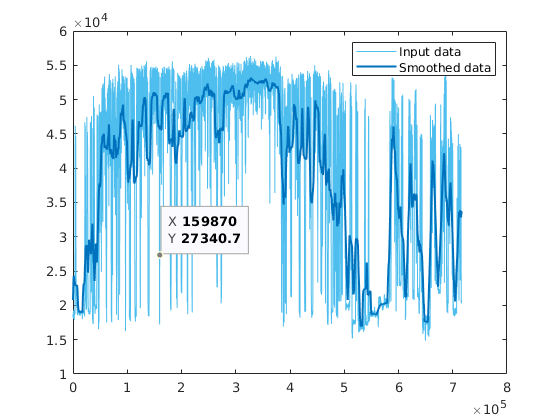

% Smooth input data
smoothedData = smoothdata(dd,"movmean","SmoothingFactor",0.4);

% Display results
clf
plot(dd,"Color",[77 190 238]/255,"DisplayName","Input data")
hold on
plot(smoothedData,"Color",[0 114 189]/255,"LineWidth",1.5,...
    "DisplayName","Smoothed data")
hold off
legend

smoothedData = dd

smoothedData = 1×716326 single row vector
	1.0e+04 *

    1.8624    1.8629    1.8630    1.8451    1.8471    1.8463    1.8464    1.8460    1.8451    1.8441    1.8445    1.8439    1.8438    1.8435    1.8451    1.8462    1.8487    1.8479    1.8472    1.8478    1.8458    1.8410    1.8363    1.8366    1.8358    1.8364    1.8311    1.8282    1.8246    1.8227    1.8233    1.8232    1.8233    1.8230    1.8234    1.8243    1.8251    1.8258    1.8257    1.8264    1.8263    1.8257    1.8269    1.8284    1.8285    1.8299    1.8292    1.8280    1.8251    1.8245


above = find(smoothedData > 3*10^4)

above =         3836        3837        3838        3839        3840        3841        3842        3843        3844        3845        3846        3847        3848        3849        3850        3851        3852        3853        3854        3855        3856        3857        3858        3859        3860        3861        3862        3863        3864        3865        3866        3867        3868        3869        3870        3871        3872        3873        3874        3875        3876        3877        3878        3879        3880        3881        3882        3883        3884        3885


below = find(smoothedData < 3*10^4)

below =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


int = intersect(above,below+1)

int =         3836        4761       21695       25373       31748       33891       34560       37607       38941       44116       48134       52300       61414       62142       71659       73051       80360       83689       86095       97170      106002      116683      124305      140422      159899      181083      187567      192144      200704      211666      219867      225877      266348      274092      385113      387144      389238      391982      393443      402981      418624      428877      442266      451252      458843      460023      465530      470625      479206      481467


int_end = intersect(above,below-1)

int_end =         4637        5361       23165       27350       33623       34363       35343       38377       39707       46562       52149       61081       61700       70355       72891       79939       82935       85908       96646      103823      113825      123533      138127      159192      179253      187400      190328      199285      210433      219234      225818      264935      272795      384238      387010      387594      391048      393088      401214      416729      426678      438908      451078      456715      459960      465187      468422      475864      481043      482201


int_end(end+1) = length(dd)

int_end =         4637        5361       23165       27350       33623       34363       35343       38377       39707       46562       52149       61081       61700       70355       72891       79939       82935       85908       96646      103823      113825      123533      138127      159192      179253      187400      190328      199285      210433      219234      225818      264935      272795      384238      387010      387594      391048      393088      401214      416729      426678      438908      451078      456715      459960      465187      468422      475864      481043      482201


int_end(1) = [];

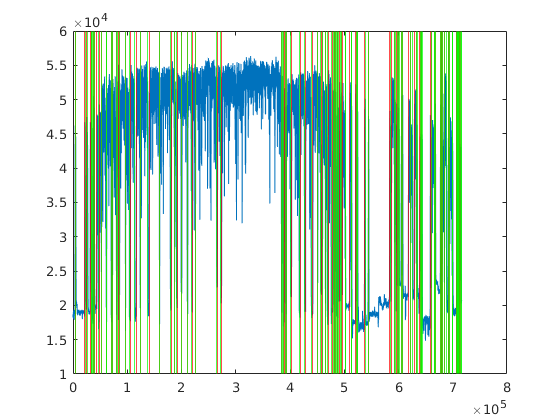

figure;
plot(smoothedData)
hold on

xline(int,'r')
xline(int_end,'g')

all_whisking = [sampleVector(int),sampleVector(int_end)]

all_whisking =       362132      476577
      431551     1812702
     1702390     2126773
     1978408     2597527
     2456825     2653069
     2617650     2726622
     2667861     2954306
     2896523     3054116
     2996634     3568566
     3384992     3988142


audible_whisking = {}


audible_whisking =

  0×0 empty cell array



non_audible_whisking = {}


non_audible_whisking =

  0×0 empty cell array



no_object_whisking = {}


no_object_whisking =

  0×0 empty cell array



for i = 1:length(all_whisking)
    temp_whisking = [all_whisking(i,1):all_whisking(i,2)]
    audible_whisking{i} = splitEvents(temp_whisking,FVB103_849.experiment.sound_events.aluminum)
    non_audible_whisking{i} = splitEvents(temp_whisking,FVB103_849.experiment.sound_events.muted)
    no_object_whisking{i} = splitEvents(temp_whisking,FVB103_849.experiment.sound_events.non)
end

temp_whisking =       362132      362133      362134      362135      362136      362137      362138      362139      362140      362141      362142      362143      362144      362145      362146      362147      362148      362149      362150      362151      362152      362153      362154      362155      362156      362157      362158      362159      362160      362161      362162      362163      362164      362165      362166      362167      362168      362169      362170      362171      362172      362173      362174      362175      362176      362177      362178      362179      362180      362181


audible_whisking = 1×1 cell array
    {1×0 double}


non_audible_whisking = 1×1 cell array
    {1×0 double}


no_object_whisking = 1×1 cell array
    {1×0 double}


temp_whisking =       431551      431552      431553      431554      431555      431556      431557      431558      431559      431560      431561      431562      431563      431564      431565      431566      431567      431568      431569      431570      431571      431572      431573      431574      431575      431576      431577      431578      431579      431580      431581      431582      431583      431584      431585      431586      431587      431588      431589      431590      431591      431592      431593      431594      431595      431596      431597      431598      431599      431600


audible_whisking = 1×2 cell array
    {1×0 double}    {1×0 double}


non_audible_whisking = 1×2 cell array
    {1×0 double}    {1×0 double}


no_object_whisking = 1×2 cell array
    {1×0 double}    {1×0 double}


temp_whisking =      1702390     1702391     1702392     1702393     1702394     1702395     1702396     1702397     1702398     1702399     1702400     1702401     1702402     1702403     1702404     1702405     1702406     1702407     1702408     1702409     1702410     1702411     1702412     1702413     1702414     1702415     1702416     1702417     1702418     1702419     1702420     1702421     1702422     1702423     1702424     1702425     1702426     1702427     1702428     1702429     1702430     1702431     1702432     1702433     1702434     1702435     1702436     1702437     1702438     1702439


audible_whisking = 1×3 cell array
    {1×0 double}    {1×0 double}    {1×0 double}


non_audible_whisking = 1×3 cell array
    {1×0 double}    {1×0 double}    {1×0 double}


no_object_whisking = 1×3 cell array
    {1×0 double}    {1×0 double}    {1×0 double}


temp_whisking =      1978408     1978409     1978410     1978411     1978412     1978413     1978414     1978415     1978416     1978417     1978418     1978419     1978420     1978421     1978422     1978423     1978424     1978425     1978426     1978427     1978428     1978429     1978430     1978431     1978432     1978433     1978434     1978435     1978436     1978437     1978438     1978439     1978440     1978441     1978442     1978443     1978444     1978445     1978446     1978447     1978448     1978449     1978450     1978451     1978452     1978453     1978454     1978455     1978456     1978457


audible_whisking = 1×4 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}


non_audible_whisking = 1×4 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}


no_object_whisking = 1×4 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}


temp_whisking =      2456825     2456826     2456827     2456828     2456829     2456830     2456831     2456832     2456833     2456834     2456835     2456836     2456837     2456838     2456839     2456840     2456841     2456842     2456843     2456844     2456845     2456846     2456847     2456848     2456849     2456850     2456851     2456852     2456853     2456854     2456855     2456856     2456857     2456858     2456859     2456860     2456861     2456862     2456863     2456864     2456865     2456866     2456867     2456868     2456869     2456870     2456871     2456872     2456873     2456874


audible_whisking = 1×5 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}


non_audible_whisking = 1×5 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}


no_object_whisking = 1×5 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}


temp_whisking =      2617650     2617651     2617652     2617653     2617654     2617655     2617656     2617657     2617658     2617659     2617660     2617661     2617662     2617663     2617664     2617665     2617666     2617667     2617668     2617669     2617670     2617671     2617672     2617673     2617674     2617675     2617676     2617677     2617678     2617679     2617680     2617681     2617682     2617683     2617684     2617685     2617686     2617687     2617688     2617689     2617690     2617691     2617692     2617693     2617694     2617695     2617696     2617697     2617698     2617699


audible_whisking = 1×6 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}


non_audible_whisking = 1×6 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}


no_object_whisking = 1×6 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}


temp_whisking =      2667861     2667862     2667863     2667864     2667865     2667866     2667867     2667868     2667869     2667870     2667871     2667872     2667873     2667874     2667875     2667876     2667877     2667878     2667879     2667880     2667881     2667882     2667883     2667884     2667885     2667886     2667887     2667888     2667889     2667890     2667891     2667892     2667893     2667894     2667895     2667896     2667897     2667898     2667899     2667900     2667901     2667902     2667903     2667904     2667905     2667906     2667907     2667908     2667909     2667910


audible_whisking = 1×7 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}


non_audible_whisking = 1×7 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}


no_object_whisking = 1×7 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}


temp_whisking =      2896523     2896524     2896525     2896526     2896527     2896528     2896529     2896530     2896531     2896532     2896533     2896534     2896535     2896536     2896537     2896538     2896539     2896540     2896541     2896542     2896543     2896544     2896545     2896546     2896547     2896548     2896549     2896550     2896551     2896552     2896553     2896554     2896555     2896556     2896557     2896558     2896559     2896560     2896561     2896562     2896563     2896564     2896565     2896566     2896567     2896568     2896569     2896570     2896571     2896572


audible_whisking = 1×8 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}


non_audible_whisking = 1×8 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}


no_object_whisking = 1×8 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}


temp_whisking =      2996634     2996635     2996636     2996637     2996638     2996639     2996640     2996641     2996642     2996643     2996644     2996645     2996646     2996647     2996648     2996649     2996650     2996651     2996652     2996653     2996654     2996655     2996656     2996657     2996658     2996659     2996660     2996661     2996662     2996663     2996664     2996665     2996666     2996667     2996668     2996669     2996670     2996671     2996672     2996673     2996674     2996675     2996676     2996677     2996678     2996679     2996680     2996681     2996682     2996683


audible_whisking = 1×9 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}


non_audible_whisking = 1×9 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}


no_object_whisking = 1×9 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}


temp_whisking =      3384992     3384993     3384994     3384995     3384996     3384997     3384998     3384999     3385000     3385001     3385002     3385003     3385004     3385005     3385006     3385007     3385008     3385009     3385010     3385011     3385012     3385013     3385014     3385015     3385016     3385017     3385018     3385019     3385020     3385021     3385022     3385023     3385024     3385025     3385026     3385027     3385028     3385029     3385030     3385031     3385032     3385033     3385034     3385035     3385036     3385037     3385038     3385039     3385040     3385041


audible_whisking = 1×10 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}


non_audible_whisking = 1×10 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}


no_object_whisking = 1×10 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}


temp_whisking =      3686534     3686535     3686536     3686537     3686538     3686539     3686540     3686541     3686542     3686543     3686544     3686545     3686546     3686547     3686548     3686549     3686550     3686551     3686552     3686553     3686554     3686555     3686556     3686557     3686558     3686559     3686560     3686561     3686562     3686563     3686564     3686565     3686566     3686567     3686568     3686569     3686570     3686571     3686572     3686573     3686574     3686575     3686576     3686577     3686578     3686579     3686580     3686581     3686582     3686583


audible_whisking = 1×11 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}


non_audible_whisking = 1×11 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}


no_object_whisking = 1×11 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}


temp_whisking =      3999470     3999471     3999472     3999473     3999474     3999475     3999476     3999477     3999478     3999479     3999480     3999481     3999482     3999483     3999484     3999485     3999486     3999487     3999488     3999489     3999490     3999491     3999492     3999493     3999494     3999495     3999496     3999497     3999498     3999499     3999500     3999501     3999502     3999503     3999504     3999505     3999506     3999507     3999508     3999509     3999510     3999511     3999512     3999513     3999514     3999515     3999516     3999517     3999518     3999519


audible_whisking = 1×12 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}


non_audible_whisking = 1×12 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}


no_object_whisking = 1×12 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}


temp_whisking =      4683744     4683745     4683746     4683747     4683748     4683749     4683750     4683751     4683752     4683753     4683754     4683755     4683756     4683757     4683758     4683759     4683760     4683761     4683762     4683763     4683764     4683765     4683766     4683767     4683768     4683769     4683770     4683771     4683772     4683773     4683774     4683775     4683776     4683777     4683778     4683779     4683780     4683781     4683782     4683783     4683784     4683785     4683786     4683787     4683788     4683789     4683790     4683791     4683792     4683793


audible_whisking = 1×13 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}


non_audible_whisking = 1×13 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}


no_object_whisking = 1×13 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×569409 double}


temp_whisking =      4738368     4738369     4738370     4738371     4738372     4738373     4738374     4738375     4738376     4738377     4738378     4738379     4738380     4738381     4738382     4738383     4738384     4738385     4738386     4738387     4738388     4738389     4738390     4738391     4738392     4738393     4738394     4738395     4738396     4738397     4738398     4738399     4738400     4738401     4738402     4738403     4738404     4738405     4738406     4738407     4738408     4738409     4738410     4738411     4738412     4738413     4738414     4738415     4738416     4738417


audible_whisking = 1×14 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}


non_audible_whisking = 1×14 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}


no_object_whisking = 1×14 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×569409 double}    {1×759800 double}


temp_whisking = 1×621528
     5465863     5465864     5465865     5465866     5465867     5465868     5465869     5465870     5465871     5465872     5465873     5465874     5465875     5465876     5465877     5465878     5465879     5465880     5465881     5465882     5465883     5465884     5465885     5465886     5465887     5465888     5465889     5465890     5465891     5465892


audible_whisking = 1×15 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}


non_audible_whisking = 1×15 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}


no_object_whisking = 1×15 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×569409 double}    {1×759800 double}    {1×621528 double}


temp_whisking = 1×741822
     5570406     5570407     5570408     5570409     5570410     5570411     5570412     5570413     5570414     5570415     5570416     5570417     5570418     5570419     5570420     5570421     5570422     5570423     5570424     5570425     5570426     5570427     5570428     5570429     5570430     5570431     5570432     5570433     5570434     5570435


audible_whisking = 1×16 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}


non_audible_whisking = 1×16 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}


no_object_whisking = 1×16 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×569409 double}    {1×759800 double}    {1×621528 double}    {1×741822 double}


temp_whisking = 1×416358
     6118984     6118985     6118986     6118987     6118988     6118989     6118990     6118991     6118992     6118993     6118994     6118995     6118996     6118997     6118998     6118999     6119000     6119001     6119002     6119003     6119004     6119005     6119006     6119007     6119008     6119009     6119010     6119011     6119012     6119013


audible_whisking = 1×17 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}


non_audible_whisking = 1×17 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}


no_object_whisking = 1×17 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×569409 double}    {1×759800 double}    {1×621528 double}    {1×741822 double}    {1×398135 double}


temp_whisking = 1×972515
     6368816     6368817     6368818     6368819     6368820     6368821     6368822     6368823     6368824     6368825     6368826     6368827     6368828     6368829     6368830     6368831     6368832     6368833     6368834     6368835     6368836     6368837     6368838     6368839     6368840     6368841     6368842     6368843     6368844     6368845


audible_whisking = 1×18 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}


non_audible_whisking = 1×18 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×659211 double}


no_object_whisking = 1×18 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×569409 double}    {1×759800 double}    {1×621528 double}    {1×741822 double}    {1×398135 double}    {1×148303 double}


temp_whisking = 1×1330634
     6549375     6549376     6549377     6549378     6549379     6549380     6549381     6549382     6549383     6549384     6549385     6549386     6549387     6549388     6549389     6549390     6549391     6549392     6549393     6549394     6549395     6549396     6549397     6549398     6549399     6549400     6549401     6549402     6549403     6549404


audible_whisking = 1×19 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}


non_audible_whisking = 1×19 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×659211 double}    {1×1197889 double}


no_object_whisking = 1×19 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×569409 double}    {1×759800 double}    {1×621528 double}    {1×741822 double}    {1×398135 double}    {1×148303 double}    {1×0 double}


temp_whisking = 1×1249967
     7380656     7380657     7380658     7380659     7380660     7380661     7380662     7380663     7380664     7380665     7380666     7380667     7380668     7380669     7380670     7380671     7380672     7380673     7380674     7380675     7380676     7380677     7380678     7380679     7380680     7380681     7380682     7380683     7380684     7380685


audible_whisking = 1×20 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}


non_audible_whisking = 1×20 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×659211 double}    {1×1197889 double}    {1×1025987 double}


no_object_whisking = 1×20 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×569409 double}    {1×759800 double}    {1×621528 double}    {1×741822 double}    {1×398135 double}    {1×148303 double}    {1×0 double}    {1×58979 double}


temp_whisking = 1×1315634
     8043534     8043535     8043536     8043537     8043538     8043539     8043540     8043541     8043542     8043543     8043544     8043545     8043546     8043547     8043548     8043549     8043550     8043551     8043552     8043553     8043554     8043555     8043556     8043557     8043558     8043559     8043560     8043561     8043562     8043563


audible_whisking = 1×21 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}


non_audible_whisking = 1×21 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×659211 double}    {1×1197889 double}    {1×1025987 double}    {1×363109 double}


no_object_whisking = 1×21 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×569409 double}    {1×759800 double}    {1×621528 double}    {1×741822 double}    {1×398135 double}    {1×148303 double}    {1×0 double}    {1×58979 double}    {1×787524 double}


temp_whisking = 1×1609294
     8845104     8845105     8845106     8845107     8845108     8845109     8845110     8845111     8845112     8845113     8845114     8845115     8845116     8845117     8845118     8845119     8845120     8845121     8845122     8845123     8845124     8845125     8845126     8845127     8845128     8845129     8845130     8845131     8845132     8845133


audible_whisking = 1×22 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}


non_audible_whisking = 1×22 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×659211 double}    {1×1197889 double}    {1×1025987 double}    {1×363109 double}    {1×0 double}


no_object_whisking = 1×22 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×569409 double}    {1×759800 double}    {1×621528 double}    {1×741822 double}    {1×398135 double}    {1×148303 double}    {1×0 double}    {1×58979 double}    {1×787524 double}    {1×1445067 double}


temp_whisking = 1×2618445
     9417102     9417103     9417104     9417105     9417106     9417107     9417108     9417109     9417110     9417111     9417112     9417113     9417114     9417115     9417116     9417117     9417118     9417119     9417120     9417121     9417122     9417123     9417124     9417125     9417126     9417127     9417128     9417129     9417130     9417131


audible_whisking = 1×23 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}


non_audible_whisking = 1×23 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×659211 double}    {1×1197889 double}    {1×1025987 double}    {1×363109 double}    {1×0 double}    {1×1580375 double}


no_object_whisking = 1×23 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×569409 double}    {1×759800 double}    {1×621528 double}    {1×741822 double}    {1×398135 double}    {1×148303 double}    {1×0 double}    {1×58979 double}    {1×787524 double}    {1×1445067 double}    {1×873069 double}


temp_whisking = 1×2914697
    10626632    10626633    10626634    10626635    10626636    10626637    10626638    10626639    10626640    10626641    10626642    10626643    10626644    10626645    10626646    10626647    10626648    10626649    10626650    10626651    10626652    10626653    10626654    10626655    10626656    10626657    10626658    10626659    10626660    10626661


audible_whisking = 1×24 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}


non_audible_whisking = 1×24 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×659211 double}    {1×1197889 double}    {1×1025987 double}    {1×363109 double}    {1×0 double}    {1×1580375 double}    {1×2749696 double}


no_object_whisking = 1×24 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×569409 double}    {1×759800 double}    {1×621528 double}    {1×741822 double}    {1×398135 double}    {1×148303 double}    {1×0 double}    {1×58979 double}    {1×787524 double}    {1×1445067 double}    {1×873069 double}    {1×0 double}


temp_whisking = 1×2064129
    12088595    12088596    12088597    12088598    12088599    12088600    12088601    12088602    12088603    12088604    12088605    12088606    12088607    12088608    12088609    12088610    12088611    12088612    12088613    12088614    12088615    12088616    12088617    12088618    12088619    12088620    12088621    12088622    12088623    12088624


audible_whisking = 1×25 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}


non_audible_whisking = 1×25 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×659211 double}    {1×1197889 double}    {1×1025987 double}    {1×363109 double}    {1×0 double}    {1×1580375 double}    {1×2749696 double}    {1×1797632 double}


no_object_whisking = 1×25 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×569409 double}    {1×759800 double}    {1×621528 double}    {1×741822 double}    {1×398135 double}    {1×148303 double}    {1×0 double}    {1×58979 double}    {1×787524 double}    {1×1445067 double}    {1×873069 double}    {1×0 double}    {1×0 double}


temp_whisking = 1×693867
    13678669    13678670    13678671    13678672    13678673    13678674    13678675    13678676    13678677    13678678    13678679    13678680    13678681    13678682    13678683    13678684    13678685    13678686    13678687    13678688    13678689    13678690    13678691    13678692    13678693    13678694    13678695    13678696    13678697    13678698


audible_whisking = 1×26 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×156307 double}


non_audible_whisking = 1×26 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×659211 double}    {1×1197889 double}    {1×1025987 double}    {1×363109 double}    {1×0 double}    {1×1580375 double}    {1×2749696 double}    {1×1797632 double}    {1×372559 double}


no_object_whisking = 1×26 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×569409 double}    {1×759800 double}    {1×621528 double}    {1×741822 double}    {1×398135 double}    {1×148303 double}    {1×0 double}    {1×58979 double}    {1×787524 double}    {1×1445067 double}    {1×873069 double}    {1×0 double}    {1×0 double}    {1×0 double}


temp_whisking = 1×879532
    14165263    14165264    14165265    14165266    14165267    14165268    14165269    14165270    14165271    14165272    14165273    14165274    14165275    14165276    14165277    14165278    14165279    14165280    14165281    14165282    14165283    14165284    14165285    14165286    14165287    14165288    14165289    14165290    14165291    14165292


audible_whisking = 1×27 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×156307 double}    {1×828566 double}


non_audible_whisking = 1×27 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×659211 double}    {1×1197889 double}    {1×1025987 double}    {1×363109 double}    {1×0 double}    {1×1580375 double}    {1×2749696 double}    {1×1797632 double}    {1×372559 double}    {1×0 double}


no_object_whisking = 1×27 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×569409 double}    {1×759800 double}    {1×621528 double}    {1×741822 double}    {1×398135 double}    {1×148303 double}    {1×0 double}    {1×58979 double}    {1×787524 double}    {1×1445067 double}    {1×873069 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}


temp_whisking = 1×1372587
    14508893    14508894    14508895    14508896    14508897    14508898    14508899    14508900    14508901    14508902    14508903    14508904    14508905    14508906    14508907    14508908    14508909    14508910    14508911    14508912    14508913    14508914    14508915    14508916    14508917    14508918    14508919    14508920    14508921    14508922


audible_whisking = 1×28 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×156307 double}    {1×828566 double}    {1×1372587 double}


non_audible_whisking = 1×28 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×659211 double}    {1×1197889 double}    {1×1025987 double}    {1×363109 double}    {1×0 double}    {1×1580375 double}    {1×2749696 double}    {1×1797632 double}    {1×372559 double}    {1×0 double}    {1×0 double}


no_object_whisking = 1×28 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×569409 double}    {1×759800 double}    {1×621528 double}    {1×741822 double}    {1×398135 double}    {1×148303 double}    {1×0 double}    {1×58979 double}    {1×787524 double}    {1×1445067 double}    {1×873069 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}


temp_whisking = 1×1390677
    15151362    15151363    15151364    15151365    15151366    15151367    15151368    15151369    15151370    15151371    15151372    15151373    15151374    15151375    15151376    15151377    15151378    15151379    15151380    15151381    15151382    15151383    15151384    15151385    15151386    15151387    15151388    15151389    15151390    15151391


audible_whisking = 1×29 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×156307 double}    {1×828566 double}    {1×1372587 double}    {1×783397 double}


non_audible_whisking = 1×29 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×659211 double}    {1×1197889 double}    {1×1025987 double}    {1×363109 double}    {1×0 double}    {1×1580375 double}    {1×2749696 double}    {1×1797632 double}    {1×372559 double}    {1×0 double}    {1×0 double}    {1×442279 double}


no_object_whisking = 1×29 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×569409 double}    {1×759800 double}    {1×621528 double}    {1×741822 double}    {1×398135 double}    {1×148303 double}    {1×0 double}    {1×58979 double}    {1×787524 double}    {1×1445067 double}    {1×873069 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}


temp_whisking = 1×1062123
    15974014    15974015    15974016    15974017    15974018    15974019    15974020    15974021    15974022    15974023    15974024    15974025    15974026    15974027    15974028    15974029    15974030    15974031    15974032    15974033    15974034    15974035    15974036    15974037    15974038    15974039    15974040    15974041    15974042    15974043


audible_whisking = 1×30 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×156307 double}    {1×828566 double}    {1×1372587 double}    {1×783397 double}    {1×0 double}


non_audible_whisking = 1×30 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×659211 double}    {1×1197889 double}    {1×1025987 double}    {1×363109 double}    {1×0 double}    {1×1580375 double}    {1×2749696 double}    {1×1797632 double}    {1×372559 double}    {1×0 double}    {1×0 double}    {1×442279 double}    {1×936377 double}


no_object_whisking = 1×30 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×569409 double}    {1×759800 double}    {1×621528 double}    {1×741822 double}    {1×398135 double}    {1×148303 double}    {1×0 double}    {1×58979 double}    {1×787524 double}    {1×1445067 double}    {1×873069 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}


temp_whisking = 1×3382179
    16589540    16589541    16589542    16589543    16589544    16589545    16589546    16589547    16589548    16589549    16589550    16589551    16589552    16589553    16589554    16589555    16589556    16589557    16589558    16589559    16589560    16589561    16589562    16589563    16589564    16589565    16589566    16589567    16589568    16589569


audible_whisking = 1×31 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×156307 double}    {1×828566 double}    {1×1372587 double}    {1×783397 double}    {1×0 double}    {1×104859 double}


non_audible_whisking = 1×31 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×659211 double}    {1×1197889 double}    {1×1025987 double}    {1×363109 double}    {1×0 double}    {1×1580375 double}    {1×2749696 double}    {1×1797632 double}    {1×372559 double}    {1×0 double}    {1×0 double}    {1×442279 double}    {1×936377 double}    {1×1234746 double}


no_object_whisking = 1×31 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×569409 double}    {1×759800 double}    {1×621528 double}    {1×741822 double}    {1×398135 double}    {1×148303 double}    {1×0 double}    {1×58979 double}    {1×787524 double}    {1×1445067 double}    {1×873069 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×1712572 double}


temp_whisking = 1×3521015
    17040566    17040567    17040568    17040569    17040570    17040571    17040572    17040573    17040574    17040575    17040576    17040577    17040578    17040579    17040580    17040581    17040582    17040583    17040584    17040585    17040586    17040587    17040588    17040589    17040590    17040591    17040592    17040593    17040594    17040595


audible_whisking = 1×32 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×156307 double}    {1×828566 double}    {1×1372587 double}    {1×783397 double}    {1×0 double}    {1×104859 double}    {1×694721 double}


non_audible_whisking = 1×32 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×659211 double}    {1×1197889 double}    {1×1025987 double}    {1×363109 double}    {1×0 double}    {1×1580375 double}    {1×2749696 double}    {1×1797632 double}    {1×372559 double}    {1×0 double}    {1×0 double}    {1×442279 double}    {1×936377 double}    {1×1234746 double}    {1×783720 double}


no_object_whisking = 1×32 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×569409 double}    {1×759800 double}    {1×621528 double}    {1×741822 double}    {1×398135 double}    {1×148303 double}    {1×0 double}    {1×58979 double}    {1×787524 double}    {1×1445067 double}    {1×873069 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×1712572 double}    {1×1712572 double}


temp_whisking = 1×8848363
    20077754    20077755    20077756    20077757    20077758    20077759    20077760    20077761    20077762    20077763    20077764    20077765    20077766    20077767    20077768    20077769    20077770    20077771    20077772    20077773    20077774    20077775    20077776    20077777    20077778    20077779    20077780    20077781    20077782    20077783


audible_whisking = 1×33 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×156307 double}    {1×828566 double}    {1×1372587 double}    {1×783397 double}    {1×0 double}    {1×104859 double}    {1×694721 double}    {1×3226160 double}


non_audible_whisking = 1×33 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×659211 double}    {1×1197889 double}    {1×1025987 double}    {1×363109 double}    {1×0 double}    {1×1580375 double}    {1×2749696 double}    {1×1797632 double}    {1×372559 double}    {1×0 double}    {1×0 double}    {1×442279 double}    {1×936377 double}    {1×1234746 double}    {1×783720 double}    {1×3249674 double}


no_object_whisking = 1×33 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×569409 double}    {1×759800 double}    {1×621528 double}    {1×741822 double}    {1×398135 double}    {1×148303 double}    {1×0 double}    {1×58979 double}    {1×787524 double}    {1×1445067 double}    {1×873069 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×1712572 double}    {1×1712572 double}    {1×1712525 double}


temp_whisking = 1×8475227
    20658912    20658913    20658914    20658915    20658916    20658917    20658918    20658919    20658920    20658921    20658922    20658923    20658924    20658925    20658926    20658927    20658928    20658929    20658930    20658931    20658932    20658933    20658934    20658935    20658936    20658937    20658938    20658939    20658940    20658941


audible_whisking = 1×34 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×156307 double}    {1×828566 double}    {1×1372587 double}    {1×783397 double}    {1×0 double}    {1×104859 double}    {1×694721 double}    {1×3226160 double}    {1×2645002 double}


non_audible_whisking = 1×34 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×659211 double}    {1×1197889 double}    {1×1025987 double}    {1×363109 double}    {1×0 double}    {1×1580375 double}    {1×2749696 double}    {1×1797632 double}    {1×372559 double}    {1×0 double}    {1×0 double}    {1×442279 double}    {1×936377 double}    {1×1234746 double}    {1×783720 double}    {1×3249674 double}    {1×3437045 double}


no_object_whisking = 1×34 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×569409 double}    {1×759800 double}    {1×621528 double}    {1×741822 double}    {1×398135 double}    {1×148303 double}    {1×0 double}    {1×58979 double}    {1×787524 double}    {1×1445067 double}    {1×873069 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×1712572 double}    {1×1712572 double}    {1×1712525 double}    {1×1712525 double}


temp_whisking = 1×186184
    28991776    28991777    28991778    28991779    28991780    28991781    28991782    28991783    28991784    28991785    28991786    28991787    28991788    28991789    28991790    28991791    28991792    28991793    28991794    28991795    28991796    28991797    28991798    28991799    28991800    28991801    28991802    28991803    28991804    28991805


audible_whisking = 1×35 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×156307 double}    {1×828566 double}    {1×1372587 double}    {1×783397 double}    {1×0 double}    {1×104859 double}    {1×694721 double}    {1×3226160 double}    {1×2645002 double}    {1×0 double}


non_audible_whisking = 1×35 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×659211 double}    {1×1197889 double}    {1×1025987 double}    {1×363109 double}    {1×0 double}    {1×1580375 double}    {1×2749696 double}    {1×1797632 double}    {1×372559 double}    {1×0 double}    {1×0 double}    {1×442279 double}    {1×936377 double}    {1×1234746 double}    {1×783720 double}    {1×3249674 double}    {1×3437045 double}    {1×121712 double}


no_object_whisking = 1×35 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×569409 double}    {1×759800 double}    {1×621528 double}    {1×741822 double}    {1×398135 double}    {1×148303 double}    {1×0 double}    {1×58979 double}    {1×787524 double}    {1×1445067 double}    {1×873069 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×1712572 double}    {1×1712572 double}    {1×1712525 double}    {1×1712525 double}    {1×0 double}


temp_whisking = 1×292985
    29144195    29144196    29144197    29144198    29144199    29144200    29144201    29144202    29144203    29144204    29144205    29144206    29144207    29144208    29144209    29144210    29144211    29144212    29144213    29144214    29144215    29144216    29144217    29144218    29144219    29144220    29144221    29144222    29144223    29144224


audible_whisking = 1×36 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×156307 double}    {1×828566 double}    {1×1372587 double}    {1×783397 double}    {1×0 double}    {1×104859 double}    {1×694721 double}    {1×3226160 double}    {1×2645002 double}    {1×0 double}    {1×158691 double}


non_audible_whisking = 1×36 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×659211 double}    {1×1197889 double}    {1×1025987 double}    {1×363109 double}    {1×0 double}    {1×1580375 double}    {1×2749696 double}    {1×1797632 double}    {1×372559 double}    {1×0 double}    {1×0 double}    {1×442279 double}    {1×936377 double}    {1×1234746 double}    {1×783720 double}    {1×3249674 double}    {1×3437045 double}    {1×121712 double}    {1×0 double}


no_object_whisking = 1×36 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×569409 double}    {1×759800 double}    {1×621528 double}    {1×741822 double}    {1×398135 double}    {1×148303 double}    {1×0 double}    {1×58979 double}    {1×787524 double}    {1×1445067 double}    {1×873069 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×1712572 double}    {1×1712572 double}    {1×1712525 double}    {1×1712525 double}    {1×0 double}    {1×0 double}


temp_whisking = 1×288929
    29301336    29301337    29301338    29301339    29301340    29301341    29301342    29301343    29301344    29301345    29301346    29301347    29301348    29301349    29301350    29301351    29301352    29301353    29301354    29301355    29301356    29301357    29301358    29301359    29301360    29301361    29301362    29301363    29301364    29301365


audible_whisking = 1×37 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×156307 double}    {1×828566 double}    {1×1372587 double}    {1×783397 double}    {1×0 double}    {1×104859 double}    {1×694721 double}    {1×3226160 double}    {1×2645002 double}    {1×0 double}    {1×158691 double}    {1×288929 double}


non_audible_whisking = 1×37 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×659211 double}    {1×1197889 double}    {1×1025987 double}    {1×363109 double}    {1×0 double}    {1×1580375 double}    {1×2749696 double}    {1×1797632 double}    {1×372559 double}    {1×0 double}    {1×0 double}    {1×442279 double}    {1×936377 double}    {1×1234746 double}    {1×783720 double}    {1×3249674 double}    {1×3437045 double}    {1×121712 double}    {1×0 double}    {1×0 double}


no_object_whisking = 1×37 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×569409 double}    {1×759800 double}    {1×621528 double}    {1×741822 double}    {1×398135 double}    {1×148303 double}    {1×0 double}    {1×58979 double}    {1×787524 double}    {1×1445067 double}    {1×873069 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×1712572 double}    {1×1712572 double}    {1×1712525 double}    {1×1712525 double}    {1×0 double}    {1×0 double}    {1×0 double}


temp_whisking = 1×692893
    29507273    29507274    29507275    29507276    29507277    29507278    29507279    29507280    29507281    29507282    29507283    29507284    29507285    29507286    29507287    29507288    29507289    29507290    29507291    29507292    29507293    29507294    29507295    29507296    29507297    29507298    29507299    29507300    29507301    29507302


audible_whisking = 1×38 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×156307 double}    {1×828566 double}    {1×1372587 double}    {1×783397 double}    {1×0 double}    {1×104859 double}    {1×694721 double}    {1×3226160 double}    {1×2645002 double}    {1×0 double}    {1×158691 double}    {1×288929 double}    {1×692893 double}


non_audible_whisking = 1×38 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×659211 double}    {1×1197889 double}    {1×1025987 double}    {1×363109 double}    {1×0 double}    {1×1580375 double}    {1×2749696 double}    {1×1797632 double}    {1×372559 double}    {1×0 double}    {1×0 double}    {1×442279 double}    {1×936377 double}    {1×1234746 double}    {1×783720 double}    {1×3249674 double}    {1×3437045 double}    {1×121712 double}    {1×0 double}    {1×0 double}    {1×0 double}


no_object_whisking = 1×38 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×569409 double}    {1×759800 double}    {1×621528 double}    {1×741822 double}    {1×398135 double}    {1×148303 double}    {1×0 double}    {1×58979 double}    {1×787524 double}    {1×1445067 double}    {1×873069 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×1712572 double}    {1×1712572 double}    {1×1712525 double}    {1×1712525 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}


temp_whisking = 1×1748273
    29616905    29616906    29616907    29616908    29616909    29616910    29616911    29616912    29616913    29616914    29616915    29616916    29616917    29616918    29616919    29616920    29616921    29616922    29616923    29616924    29616925    29616926    29616927    29616928    29616929    29616930    29616931    29616932    29616933    29616934


audible_whisking = 1×39 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×156307 double}    {1×828566 double}    {1×1372587 double}    {1×783397 double}    {1×0 double}    {1×104859 double}    {1×694721 double}    {1×3226160 double}    {1×2645002 double}    {1×0 double}    {1×158691 double}    {1×288929 double}    {1×692893 double}    {1×1380106 double}


non_audible_whisking = 1×39 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×659211 double}    {1×1197889 double}    {1×1025987 double}    {1×363109 double}    {1×0 double}    {1×1580375 double}    {1×2749696 double}    {1×1797632 double}    {1×372559 double}    {1×0 double}    {1×0 double}    {1×442279 double}    {1×936377 double}    {1×1234746 double}    {1×783720 double}    {1×3249674 double}    {1×3437045 double}    {1×121712 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×203166 double}


no_object_whisking = 1×39 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×569409 double}    {1×759800 double}    {1×621528 double}    {1×741822 double}    {1×398135 double}    {1×148303 double}    {1×0 double}    {1×58979 double}    {1×787524 double}    {1×1445067 double}    {1×873069 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×1712572 double}    {1×1712572 double}    {1×1712525 double}    {1×1712525 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}


temp_whisking = 1×1778806
    30333073    30333074    30333075    30333076    30333077    30333078    30333079    30333080    30333081    30333082    30333083    30333084    30333085    30333086    30333087    30333088    30333089    30333090    30333091    30333092    30333093    30333094    30333095    30333096    30333097    30333098    30333099    30333100    30333101    30333102


audible_whisking = 1×40 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×156307 double}    {1×828566 double}    {1×1372587 double}    {1×783397 double}    {1×0 double}    {1×104859 double}    {1×694721 double}    {1×3226160 double}    {1×2645002 double}    {1×0 double}    {1×158691 double}    {1×288929 double}    {1×692893 double}    {1×1380106 double}    {1×663938 double}


non_audible_whisking = 1×40 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×659211 double}    {1×1197889 double}    {1×1025987 double}    {1×363109 double}    {1×0 double}    {1×1580375 double}    {1×2749696 double}    {1×1797632 double}    {1×372559 double}    {1×0 double}    {1×0 double}    {1×442279 double}    {1×936377 double}    {1×1234746 double}    {1×783720 double}    {1×3249674 double}    {1×3437045 double}    {1×121712 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×203166 double}    {1×949867 double}


no_object_whisking = 1×40 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×569409 double}    {1×759800 double}    {1×621528 double}    {1×741822 double}    {1×398135 double}    {1×148303 double}    {1×0 double}    {1×58979 double}    {1×787524 double}    {1×1445067 double}    {1×873069 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×1712572 double}    {1×1712572 double}    {1×1712525 double}    {1×1712525 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}


temp_whisking = 1×1522458
    31507384    31507385    31507386    31507387    31507388    31507389    31507390    31507391    31507392    31507393    31507394    31507395    31507396    31507397    31507398    31507399    31507400    31507401    31507402    31507403    31507404    31507405    31507406    31507407    31507408    31507409    31507410    31507411    31507412    31507413


audible_whisking = 1×41 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×156307 double}    {1×828566 double}    {1×1372587 double}    {1×783397 double}    {1×0 double}    {1×104859 double}    {1×694721 double}    {1×3226160 double}    {1×2645002 double}    {1×0 double}    {1×158691 double}    {1×288929 double}    {1×692893 double}    {1×1380106 double}    {1×663938 double}    {1×0 double}


non_audible_whisking = 1×41 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×659211 double}    {1×1197889 double}    {1×1025987 double}    {1×363109 double}    {1×0 double}    {1×1580375 double}    {1×2749696 double}    {1×1797632 double}    {1×372559 double}    {1×0 double}    {1×0 double}    {1×442279 double}    {1×936377 double}    {1×1234746 double}    {1×783720 double}    {1×3249674 double}    {1×3437045 double}    {1×121712 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×203166 double}    {1×949867 double}    {1×1367147 double}


no_object_whisking = 1×41 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×569409 double}    {1×759800 double}    {1×621528 double}    {1×741822 double}    {1×398135 double}    {1×148303 double}    {1×0 double}    {1×58979 double}    {1×787524 double}    {1×1445067 double}    {1×873069 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×1712572 double}    {1×1712572 double}    {1×1712525 double}    {1×1712525 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}


temp_whisking = 1×1666241
    32276908    32276909    32276910    32276911    32276912    32276913    32276914    32276915    32276916    32276917    32276918    32276919    32276920    32276921    32276922    32276923    32276924    32276925    32276926    32276927    32276928    32276929    32276930    32276931    32276932    32276933    32276934    32276935    32276936    32276937


audible_whisking = 1×42 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×156307 double}    {1×828566 double}    {1×1372587 double}    {1×783397 double}    {1×0 double}    {1×104859 double}    {1×694721 double}    {1×3226160 double}    {1×2645002 double}    {1×0 double}    {1×158691 double}    {1×288929 double}    {1×692893 double}    {1×1380106 double}    {1×663938 double}    {1×0 double}    {1×903617 double}


non_audible_whisking = 1×42 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×659211 double}    {1×1197889 double}    {1×1025987 double}    {1×363109 double}    {1×0 double}    {1×1580375 double}    {1×2749696 double}    {1×1797632 double}    {1×372559 double}    {1×0 double}    {1×0 double}    {1×442279 double}    {1×936377 double}    {1×1234746 double}    {1×783720 double}    {1×3249674 double}    {1×3437045 double}    {1×121712 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×203166 double}    {1×949867 double}    {1×1367147 double}    {1×597623 double}


no_object_whisking = 1×42 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×569409 double}    {1×759800 double}    {1×621528 double}    {1×741822 double}    {1×398135 double}    {1×148303 double}    {1×0 double}    {1×58979 double}    {1×787524 double}    {1×1445067 double}    {1×873069 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×1712572 double}    {1×1712572 double}    {1×1712525 double}    {1×1712525 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}


temp_whisking = 1×1084342
    33281840    33281841    33281842    33281843    33281844    33281845    33281846    33281847    33281848    33281849    33281850    33281851    33281852    33281853    33281854    33281855    33281856    33281857    33281858    33281859    33281860    33281861    33281862    33281863    33281864    33281865    33281866    33281867    33281868    33281869


audible_whisking = 1×43 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×156307 double}    {1×828566 double}    {1×1372587 double}    {1×783397 double}    {1×0 double}    {1×104859 double}    {1×694721 double}    {1×3226160 double}    {1×2645002 double}    {1×0 double}    {1×158691 double}    {1×288929 double}    {1×692893 double}    {1×1380106 double}    {1×663938 double}    {1×0 double}    {1×903617 double}    {1×1084342 double}


non_audible_whisking = 1×43 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×659211 double}    {1×1197889 double}    {1×1025987 double}    {1×363109 double}    {1×0 double}    {1×1580375 double}    {1×2749696 double}    {1×1797632 double}    {1×372559 double}    {1×0 double}    {1×0 double}    {1×442279 double}    {1×936377 double}    {1×1234746 double}    {1×783720 double}    {1×3249674 double}    {1×3437045 double}    {1×121712 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×203166 double}    {1×949867 double}    {1×1367147 double}    {1×597623 double}    {1×0 double}


no_object_whisking = 1×43 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×569409 double}    {1×759800 double}    {1×621528 double}    {1×741822 double}    {1×398135 double}    {1×148303 double}    {1×0 double}    {1×58979 double}    {1×787524 double}    {1×1445067 double}    {1×873069 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×1712572 double}    {1×1712572 double}    {1×1712525 double}    {1×1712525 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}


temp_whisking = 1×653501
    33956202    33956203    33956204    33956205    33956206    33956207    33956208    33956209    33956210    33956211    33956212    33956213    33956214    33956215    33956216    33956217    33956218    33956219    33956220    33956221    33956222    33956223    33956224    33956225    33956226    33956227    33956228    33956229    33956230    33956231


audible_whisking = 1×44 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×156307 double}    {1×828566 double}    {1×1372587 double}    {1×783397 double}    {1×0 double}    {1×104859 double}    {1×694721 double}    {1×3226160 double}    {1×2645002 double}    {1×0 double}    {1×158691 double}    {1×288929 double}    {1×692893 double}    {1×1380106 double}    {1×663938 double}    {1×0 double}    {1×903617 double}    {1×1084342 double}    {1×653501 double}


non_audible_whisking = 1×44 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×659211 double}    {1×1197889 double}    {1×1025987 double}    {1×363109 double}    {1×0 double}    {1×1580375 double}    {1×2749696 double}    {1×1797632 double}    {1×372559 double}    {1×0 double}    {1×0 double}    {1×442279 double}    {1×936377 double}    {1×1234746 double}    {1×783720 double}    {1×3249674 double}    {1×3437045 double}    {1×121712 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×203166 double}    {1×949867 double}    {1×1367147 double}    {1×597623 double}    {1×0 double}    {1×0 double}


no_object_whisking = 1×44 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×569409 double}    {1×759800 double}    {1×621528 double}    {1×741822 double}    {1×398135 double}    {1×148303 double}    {1×0 double}    {1×58979 double}    {1×787524 double}    {1×1445067 double}    {1×873069 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×1712572 double}    {1×1712572 double}    {1×1712525 double}    {1×1712525 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}


temp_whisking = 1×476093
    34525875    34525876    34525877    34525878    34525879    34525880    34525881    34525882    34525883    34525884    34525885    34525886    34525887    34525888    34525889    34525890    34525891    34525892    34525893    34525894    34525895    34525896    34525897    34525898    34525899    34525900    34525901    34525902    34525903    34525904


audible_whisking = 1×45 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×156307 double}    {1×828566 double}    {1×1372587 double}    {1×783397 double}    {1×0 double}    {1×104859 double}    {1×694721 double}    {1×3226160 double}    {1×2645002 double}    {1×0 double}    {1×158691 double}    {1×288929 double}    {1×692893 double}    {1×1380106 double}    {1×663938 double}    {1×0 double}    {1×903617 double}    {1×1084342 double}    {1×653501 double}    {1×232220 double}


non_audible_whisking = 1×45 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×659211 double}    {1×1197889 double}    {1×1025987 double}    {1×363109 double}    {1×0 double}    {1×1580375 double}    {1×2749696 double}    {1×1797632 double}    {1×372559 double}    {1×0 double}    {1×0 double}    {1×442279 double}    {1×936377 double}    {1×1234746 double}    {1×783720 double}    {1×3249674 double}    {1×3437045 double}    {1×121712 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×203166 double}    {1×949867 double}    {1×1367147 double}    {1×597623 double}    {1×0 double}    {1×0 double}    {1×78872 double}


no_object_whisking = 1×45 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×569409 double}    {1×759800 double}    {1×621528 double}    {1×741822 double}    {1×398135 double}    {1×148303 double}    {1×0 double}    {1×58979 double}    {1×787524 double}    {1×1445067 double}    {1×873069 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×1712572 double}    {1×1712572 double}    {1×1712525 double}    {1×1712525 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}


temp_whisking = 1×630386
    34614432    34614433    34614434    34614435    34614436    34614437    34614438    34614439    34614440    34614441    34614442    34614443    34614444    34614445    34614446    34614447    34614448    34614449    34614450    34614451    34614452    34614453    34614454    34614455    34614456    34614457    34614458    34614459    34614460    34614461


audible_whisking = 1×46 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×156307 double}    {1×828566 double}    {1×1372587 double}    {1×783397 double}    {1×0 double}    {1×104859 double}    {1×694721 double}    {1×3226160 double}    {1×2645002 double}    {1×0 double}    {1×158691 double}    {1×288929 double}    {1×692893 double}    {1×1380106 double}    {1×663938 double}    {1×0 double}    {1×903617 double}    {1×1084342 double}    {1×653501 double}    {1×232220 double}    {1×143663 double}


non_audible_whisking = 1×46 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×659211 double}    {1×1197889 double}    {1×1025987 double}    {1×363109 double}    {1×0 double}    {1×1580375 double}    {1×2749696 double}    {1×1797632 double}    {1×372559 double}    {1×0 double}    {1×0 double}    {1×442279 double}    {1×936377 double}    {1×1234746 double}    {1×783720 double}    {1×3249674 double}    {1×3437045 double}    {1×121712 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×203166 double}    {1×949867 double}    {1×1367147 double}    {1×597623 double}    {1×0 double}    {1×0 double}    {1×78872 double}    {1×321722 double}


no_object_whisking = 1×46 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×569409 double}    {1×759800 double}    {1×621528 double}    {1×741822 double}    {1×398135 double}    {1×148303 double}    {1×0 double}    {1×58979 double}    {1×787524 double}    {1×1445067 double}    {1×873069 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×1712572 double}    {1×1712572 double}    {1×1712525 double}    {1×1712525 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}


temp_whisking = 1×775602
    35027707    35027708    35027709    35027710    35027711    35027712    35027713    35027714    35027715    35027716    35027717    35027718    35027719    35027720    35027721    35027722    35027723    35027724    35027725    35027726    35027727    35027728    35027729    35027730    35027731    35027732    35027733    35027734    35027735    35027736


audible_whisking = 1×47 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×156307 double}    {1×828566 double}    {1×1372587 double}    {1×783397 double}    {1×0 double}    {1×104859 double}    {1×694721 double}    {1×3226160 double}    {1×2645002 double}    {1×0 double}    {1×158691 double}    {1×288929 double}    {1×692893 double}    {1×1380106 double}    {1×663938 double}    {1×0 double}    {1×903617 double}    {1×1084342 double}    {1×653501 double}    {1×232220 double}    {1×143663 double}    {1×0 double}


non_audible_whisking = 1×47 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×659211 double}    {1×1197889 double}    {1×1025987 double}    {1×363109 double}    {1×0 double}    {1×1580375 double}    {1×2749696 double}    {1×1797632 double}    {1×372559 double}    {1×0 double}    {1×0 double}    {1×442279 double}    {1×936377 double}    {1×1234746 double}    {1×783720 double}    {1×3249674 double}    {1×3437045 double}    {1×121712 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×203166 double}    {1×949867 double}    {1×1367147 double}    {1×597623 double}    {1×0 double}    {1×0 double}    {1×78872 double}    {1×321722 double}    {1×775602 double}


no_object_whisking = 1×47 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×569409 double}    {1×759800 double}    {1×621528 double}    {1×741822 double}    {1×398135 double}    {1×148303 double}    {1×0 double}    {1×58979 double}    {1×787524 double}    {1×1445067 double}    {1×873069 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×1712572 double}    {1×1712572 double}    {1×1712525 double}    {1×1712525 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}


temp_whisking = 1×781832
    35410144    35410145    35410146    35410147    35410148    35410149    35410150    35410151    35410152    35410153    35410154    35410155    35410156    35410157    35410158    35410159    35410160    35410161    35410162    35410163    35410164    35410165    35410166    35410167    35410168    35410169    35410170    35410171    35410172    35410173


audible_whisking = 1×48 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×156307 double}    {1×828566 double}    {1×1372587 double}    {1×783397 double}    {1×0 double}    {1×104859 double}    {1×694721 double}    {1×3226160 double}    {1×2645002 double}    {1×0 double}    {1×158691 double}    {1×288929 double}    {1×692893 double}    {1×1380106 double}    {1×663938 double}    {1×0 double}    {1×903617 double}    {1×1084342 double}    {1×653501 double}    {1×232220 double}    {1×143663 double}    {1×0 double}    {1×0 double}


non_audible_whisking = 1×48 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×659211 double}    {1×1197889 double}    {1×1025987 double}    {1×363109 double}    {1×0 double}    {1×1580375 double}    {1×2749696 double}    {1×1797632 double}    {1×372559 double}    {1×0 double}    {1×0 double}    {1×442279 double}    {1×936377 double}    {1×1234746 double}    {1×783720 double}    {1×3249674 double}    {1×3437045 double}    {1×121712 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×203166 double}    {1×949867 double}    {1×1367147 double}    {1×597623 double}    {1×0 double}    {1×0 double}    {1×78872 double}    {1×321722 double}    {1×775602 double}    {1×781832 double}


no_object_whisking = 1×48 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×569409 double}    {1×759800 double}    {1×621528 double}    {1×741822 double}    {1×398135 double}    {1×148303 double}    {1×0 double}    {1×58979 double}    {1×787524 double}    {1×1445067 double}    {1×873069 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×1712572 double}    {1×1712572 double}    {1×1712525 double}    {1×1712525 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}


temp_whisking = 1×224763
    36054112    36054113    36054114    36054115    36054116    36054117    36054118    36054119    36054120    36054121    36054122    36054123    36054124    36054125    36054126    36054127    36054128    36054129    36054130    36054131    36054132    36054133    36054134    36054135    36054136    36054137    36054138    36054139    36054140    36054141


audible_whisking = 1×49 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×156307 double}    {1×828566 double}    {1×1372587 double}    {1×783397 double}    {1×0 double}    {1×104859 double}    {1×694721 double}    {1×3226160 double}    {1×2645002 double}    {1×0 double}    {1×158691 double}    {1×288929 double}    {1×692893 double}    {1×1380106 double}    {1×663938 double}    {1×0 double}    {1×903617 double}    {1×1084342 double}    {1×653501 double}    {1×232220 double}    {1×143663 double}    {1×0 double}    {1×0 double}    {1×0 double}


non_audible_whisking = 1×49 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×659211 double}    {1×1197889 double}    {1×1025987 double}    {1×363109 double}    {1×0 double}    {1×1580375 double}    {1×2749696 double}    {1×1797632 double}    {1×372559 double}    {1×0 double}    {1×0 double}    {1×442279 double}    {1×936377 double}    {1×1234746 double}    {1×783720 double}    {1×3249674 double}    {1×3437045 double}    {1×121712 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×203166 double}    {1×949867 double}    {1×1367147 double}    {1×597623 double}    {1×0 double}    {1×0 double}    {1×78872 double}    {1×321722 double}    {1×775602 double}    {1×781832 double}    {1×224763 double}


no_object_whisking = 1×49 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×569409 double}    {1×759800 double}    {1×621528 double}    {1×741822 double}    {1×398135 double}    {1×148303 double}    {1×0 double}    {1×58979 double}    {1×787524 double}    {1×1445067 double}    {1×873069 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×1712572 double}    {1×1712572 double}    {1×1712525 double}    {1×1712525 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}


temp_whisking = 1×151220
    36223791    36223792    36223793    36223794    36223795    36223796    36223797    36223798    36223799    36223800    36223801    36223802    36223803    36223804    36223805    36223806    36223807    36223808    36223809    36223810    36223811    36223812    36223813    36223814    36223815    36223816    36223817    36223818    36223819    36223820


audible_whisking = 1×50 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×156307 double}    {1×828566 double}    {1×1372587 double}    {1×783397 double}    {1×0 double}    {1×104859 double}    {1×694721 double}    {1×3226160 double}    {1×2645002 double}    {1×0 double}    {1×158691 double}    {1×288929 double}    {1×692893 double}    {1×1380106 double}    {1×663938 double}    {1×0 double}    {1×903617 double}    {1×1084342 double}    {1×653501 double}    {1×232220 double}    {1×143663 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}


non_audible_whisking = 1×50 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×659211 double}    {1×1197889 double}    {1×1025987 double}    {1×363109 double}    {1×0 double}    {1×1580375 double}    {1×2749696 double}    {1×1797632 double}    {1×372559 double}    {1×0 double}    {1×0 double}    {1×442279 double}    {1×936377 double}    {1×1234746 double}    {1×783720 double}    {1×3249674 double}    {1×3437045 double}    {1×121712 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×203166 double}    {1×949867 double}    {1×1367147 double}    {1×597623 double}    {1×0 double}    {1×0 double}    {1×78872 double}    {1×321722 double}    {1×775602 double}    {1×781832 double}    {1×224763 double}    {1×151220 double}


no_object_whisking = 1×50 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×569409 double}    {1×759800 double}    {1×621528 double}    {1×741822 double}    {1×398135 double}    {1×148303 double}    {1×0 double}    {1×58979 double}    {1×787524 double}    {1×1445067 double}    {1×873069 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×1712572 double}    {1×1712572 double}    {1×1712525 double}    {1×1712525 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}


temp_whisking = 1×192347
    36293734    36293735    36293736    36293737    36293738    36293739    36293740    36293741    36293742    36293743    36293744    36293745    36293746    36293747    36293748    36293749    36293750    36293751    36293752    36293753    36293754    36293755    36293756    36293757    36293758    36293759    36293760    36293761    36293762    36293763


audible_whisking = 1×51 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×156307 double}    {1×828566 double}    {1×1372587 double}    {1×783397 double}    {1×0 double}    {1×104859 double}    {1×694721 double}    {1×3226160 double}    {1×2645002 double}    {1×0 double}    {1×158691 double}    {1×288929 double}    {1×692893 double}    {1×1380106 double}    {1×663938 double}    {1×0 double}    {1×903617 double}    {1×1084342 double}    {1×653501 double}    {1×232220 double}    {1×143663 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}


non_audible_whisking = 1×51 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×659211 double}    {1×1197889 double}    {1×1025987 double}    {1×363109 double}    {1×0 double}    {1×1580375 double}    {1×2749696 double}    {1×1797632 double}    {1×372559 double}    {1×0 double}    {1×0 double}    {1×442279 double}    {1×936377 double}    {1×1234746 double}    {1×783720 double}    {1×3249674 double}    {1×3437045 double}    {1×121712 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×203166 double}    {1×949867 double}    {1×1367147 double}    {1×597623 double}    {1×0 double}    {1×0 double}    {1×78872 double}    {1×321722 double}    {1×775602 double}    {1×781832 double}    {1×224763 double}    {1×151220 double}    {1×192347 double}


no_object_whisking = 1×51 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×569409 double}    {1×759800 double}    {1×621528 double}    {1×741822 double}    {1×398135 double}    {1×148303 double}    {1×0 double}    {1×58979 double}    {1×787524 double}    {1×1445067 double}    {1×873069 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×1712572 double}    {1×1712572 double}    {1×1712525 double}    {1×1712525 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}


temp_whisking = 1×283964
    36389501    36389502    36389503    36389504    36389505    36389506    36389507    36389508    36389509    36389510    36389511    36389512    36389513    36389514    36389515    36389516    36389517    36389518    36389519    36389520    36389521    36389522    36389523    36389524    36389525    36389526    36389527    36389528    36389529    36389530


audible_whisking = 1×52 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×156307 double}    {1×828566 double}    {1×1372587 double}    {1×783397 double}    {1×0 double}    {1×104859 double}    {1×694721 double}    {1×3226160 double}    {1×2645002 double}    {1×0 double}    {1×158691 double}    {1×288929 double}    {1×692893 double}    {1×1380106 double}    {1×663938 double}    {1×0 double}    {1×903617 double}    {1×1084342 double}    {1×653501 double}    {1×232220 double}    {1×143663 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}


non_audible_whisking = 1×52 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×659211 double}    {1×1197889 double}    {1×1025987 double}    {1×363109 double}    {1×0 double}    {1×1580375 double}    {1×2749696 double}    {1×1797632 double}    {1×372559 double}    {1×0 double}    {1×0 double}    {1×442279 double}    {1×936377 double}    {1×1234746 double}    {1×783720 double}    {1×3249674 double}    {1×3437045 double}    {1×121712 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×203166 double}    {1×949867 double}    {1×1367147 double}    {1×597623 double}    {1×0 double}    {1×0 double}    {1×78872 double}    {1×321722 double}    {1×775602 double}    {1×781832 double}    {1×224763 double}    {1×151220 double}    {1×192347 double}    {1×

no_object_whisking = 1×52 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×569409 double}    {1×759800 double}    {1×621528 double}    {1×741822 double}    {1×398135 double}    {1×148303 double}    {1×0 double}    {1×58979 double}    {1×787524 double}    {1×1445067 double}    {1×873069 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×1712572 double}    {1×1712572 double}    {1×1712525 double}    {1×1712525 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}


temp_whisking = 1×210516
    36625886    36625887    36625888    36625889    36625890    36625891    36625892    36625893    36625894    36625895    36625896    36625897    36625898    36625899    36625900    36625901    36625902    36625903    36625904    36625905    36625906    36625907    36625908    36625909    36625910    36625911    36625912    36625913    36625914    36625915


audible_whisking = 1×53 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×156307 double}    {1×828566 double}    {1×1372587 double}    {1×783397 double}    {1×0 double}    {1×104859 double}    {1×694721 double}    {1×3226160 double}    {1×2645002 double}    {1×0 double}    {1×158691 double}    {1×288929 double}    {1×692893 double}    {1×1380106 double}    {1×663938 double}    {1×0 double}    {1×903617 double}    {1×1084342 double}    {1×653501 double}    {1×232220 double}    {1×143663 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×35787 double}


non_audible_whisking = 1×53 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×659211 double}    {1×1197889 double}    {1×1025987 double}    {1×363109 double}    {1×0 double}    {1×1580375 double}    {1×2749696 double}    {1×1797632 double}    {1×372559 double}    {1×0 double}    {1×0 double}    {1×442279 double}    {1×936377 double}    {1×1234746 double}    {1×783720 double}    {1×3249674 double}    {1×3437045 double}    {1×121712 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×203166 double}    {1×949867 double}    {1×1367147 double}    {1×597623 double}    {1×0 double}    {1×0 double}    {1×78872 double}    {1×321722 double}    {1×775602 double}    {1×781832 double}    {1×224763 double}    {1×151220 double}    {1×192347 double}    {1×

no_object_whisking = 1×53 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×569409 double}    {1×759800 double}    {1×621528 double}    {1×741822 double}    {1×398135 double}    {1×148303 double}    {1×0 double}    {1×58979 double}    {1×787524 double}    {1×1445067 double}    {1×873069 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×1712572 double}    {1×1712572 double}    {1×1712525 double}    {1×1712525 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}


temp_whisking = 1×376960
    36725181    36725182    36725183    36725184    36725185    36725186    36725187    36725188    36725189    36725190    36725191    36725192    36725193    36725194    36725195    36725196    36725197    36725198    36725199    36725200    36725201    36725202    36725203    36725204    36725205    36725206    36725207    36725208    36725209    36725210


audible_whisking = 1×54 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×156307 double}    {1×828566 double}    {1×1372587 double}    {1×783397 double}    {1×0 double}    {1×104859 double}    {1×694721 double}    {1×3226160 double}    {1×2645002 double}    {1×0 double}    {1×158691 double}    {1×288929 double}    {1×692893 double}    {1×1380106 double}    {1×663938 double}    {1×0 double}    {1×903617 double}    {1×1084342 double}    {1×653501 double}    {1×232220 double}    {1×143663 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×35787 double}    {1×301526 doub

non_audible_whisking = 1×54 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×659211 double}    {1×1197889 double}    {1×1025987 double}    {1×363109 double}    {1×0 double}    {1×1580375 double}    {1×2749696 double}    {1×1797632 double}    {1×372559 double}    {1×0 double}    {1×0 double}    {1×442279 double}    {1×936377 double}    {1×1234746 double}    {1×783720 double}    {1×3249674 double}    {1×3437045 double}    {1×121712 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×203166 double}    {1×949867 double}    {1×1367147 double}    {1×597623 double}    {1×0 double}    {1×0 double}    {1×78872 double}    {1×321722 double}    {1×775602 double}    {1×781832 double}    {1×224763 double}    {1×151220 double}    {1×192347 double}    {1×

no_object_whisking = 1×54 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×569409 double}    {1×759800 double}    {1×621528 double}    {1×741822 double}    {1×398135 double}    {1×148303 double}    {1×0 double}    {1×58979 double}    {1×787524 double}    {1×1445067 double}    {1×873069 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×1712572 double}    {1×1712572 double}    {1×1712525 double}    {1×1712525 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}


temp_whisking = 1×336884
    36952564    36952565    36952566    36952567    36952568    36952569    36952570    36952571    36952572    36952573    36952574    36952575    36952576    36952577    36952578    36952579    36952580    36952581    36952582    36952583    36952584    36952585    36952586    36952587    36952588    36952589    36952590    36952591    36952592    36952593


audible_whisking = 1×55 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×156307 double}    {1×828566 double}    {1×1372587 double}    {1×783397 double}    {1×0 double}    {1×104859 double}    {1×694721 double}    {1×3226160 double}    {1×2645002 double}    {1×0 double}    {1×158691 double}    {1×288929 double}    {1×692893 double}    {1×1380106 double}    {1×663938 double}    {1×0 double}    {1×903617 double}    {1×1084342 double}    {1×653501 double}    {1×232220 double}    {1×143663 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×35787 double}    {1×301526 doub

non_audible_whisking = 1×55 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×659211 double}    {1×1197889 double}    {1×1025987 double}    {1×363109 double}    {1×0 double}    {1×1580375 double}    {1×2749696 double}    {1×1797632 double}    {1×372559 double}    {1×0 double}    {1×0 double}    {1×442279 double}    {1×936377 double}    {1×1234746 double}    {1×783720 double}    {1×3249674 double}    {1×3437045 double}    {1×121712 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×203166 double}    {1×949867 double}    {1×1367147 double}    {1×597623 double}    {1×0 double}    {1×0 double}    {1×78872 double}    {1×321722 double}    {1×775602 double}    {1×781832 double}    {1×224763 double}    {1×151220 double}    {1×192347 double}    {1×

no_object_whisking = 1×55 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×569409 double}    {1×759800 double}    {1×621528 double}    {1×741822 double}    {1×398135 double}    {1×148303 double}    {1×0 double}    {1×58979 double}    {1×787524 double}    {1×1445067 double}    {1×873069 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×1712572 double}    {1×1712572 double}    {1×1712525 double}    {1×1712525 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}


temp_whisking = 1×552424
    37185957    37185958    37185959    37185960    37185961    37185962    37185963    37185964    37185965    37185966    37185967    37185968    37185969    37185970    37185971    37185972    37185973    37185974    37185975    37185976    37185977    37185978    37185979    37185980    37185981    37185982    37185983    37185984    37185985    37185986


audible_whisking = 1×56 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×156307 double}    {1×828566 double}    {1×1372587 double}    {1×783397 double}    {1×0 double}    {1×104859 double}    {1×694721 double}    {1×3226160 double}    {1×2645002 double}    {1×0 double}    {1×158691 double}    {1×288929 double}    {1×692893 double}    {1×1380106 double}    {1×663938 double}    {1×0 double}    {1×903617 double}    {1×1084342 double}    {1×653501 double}    {1×232220 double}    {1×143663 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×35787 double}    {1×301526 doub

non_audible_whisking = 1×56 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×659211 double}    {1×1197889 double}    {1×1025987 double}    {1×363109 double}    {1×0 double}    {1×1580375 double}    {1×2749696 double}    {1×1797632 double}    {1×372559 double}    {1×0 double}    {1×0 double}    {1×442279 double}    {1×936377 double}    {1×1234746 double}    {1×783720 double}    {1×3249674 double}    {1×3437045 double}    {1×121712 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×203166 double}    {1×949867 double}    {1×1367147 double}    {1×597623 double}    {1×0 double}    {1×0 double}    {1×78872 double}    {1×321722 double}    {1×775602 double}    {1×781832 double}    {1×224763 double}    {1×151220 double}    {1×192347 double}    {1×

no_object_whisking = 1×56 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×569409 double}    {1×759800 double}    {1×621528 double}    {1×741822 double}    {1×398135 double}    {1×148303 double}    {1×0 double}    {1×58979 double}    {1×787524 double}    {1×1445067 double}    {1×873069 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×1712572 double}    {1×1712572 double}    {1×1712525 double}    {1×1712525 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 

temp_whisking = 1×428658
    37363898    37363899    37363900    37363901    37363902    37363903    37363904    37363905    37363906    37363907    37363908    37363909    37363910    37363911    37363912    37363913    37363914    37363915    37363916    37363917    37363918    37363919    37363920    37363921    37363922    37363923    37363924    37363925    37363926    37363927


audible_whisking = 1×57 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×156307 double}    {1×828566 double}    {1×1372587 double}    {1×783397 double}    {1×0 double}    {1×104859 double}    {1×694721 double}    {1×3226160 double}    {1×2645002 double}    {1×0 double}    {1×158691 double}    {1×288929 double}    {1×692893 double}    {1×1380106 double}    {1×663938 double}    {1×0 double}    {1×903617 double}    {1×1084342 double}    {1×653501 double}    {1×232220 double}    {1×143663 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×35787 double}    {1×301526 doub

non_audible_whisking = 1×57 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×659211 double}    {1×1197889 double}    {1×1025987 double}    {1×363109 double}    {1×0 double}    {1×1580375 double}    {1×2749696 double}    {1×1797632 double}    {1×372559 double}    {1×0 double}    {1×0 double}    {1×442279 double}    {1×936377 double}    {1×1234746 double}    {1×783720 double}    {1×3249674 double}    {1×3437045 double}    {1×121712 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×203166 double}    {1×949867 double}    {1×1367147 double}    {1×597623 double}    {1×0 double}    {1×0 double}    {1×78872 double}    {1×321722 double}    {1×775602 double}    {1×781832 double}    {1×224763 double}    {1×151220 double}    {1×192347 double}    {1×

no_object_whisking = 1×57 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×569409 double}    {1×759800 double}    {1×621528 double}    {1×741822 double}    {1×398135 double}    {1×148303 double}    {1×0 double}    {1×58979 double}    {1×787524 double}    {1×1445067 double}    {1×873069 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×1712572 double}    {1×1712572 double}    {1×1712525 double}    {1×1712525 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 

temp_whisking = 1×800148
    37749481    37749482    37749483    37749484    37749485    37749486    37749487    37749488    37749489    37749490    37749491    37749492    37749493    37749494    37749495    37749496    37749497    37749498    37749499    37749500    37749501    37749502    37749503    37749504    37749505    37749506    37749507    37749508    37749509    37749510


audible_whisking = 1×58 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×156307 double}    {1×828566 double}    {1×1372587 double}    {1×783397 double}    {1×0 double}    {1×104859 double}    {1×694721 double}    {1×3226160 double}    {1×2645002 double}    {1×0 double}    {1×158691 double}    {1×288929 double}    {1×692893 double}    {1×1380106 double}    {1×663938 double}    {1×0 double}    {1×903617 double}    {1×1084342 double}    {1×653501 double}    {1×232220 double}    {1×143663 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×35787 double}    {1×301526 doub

non_audible_whisking = 1×58 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×659211 double}    {1×1197889 double}    {1×1025987 double}    {1×363109 double}    {1×0 double}    {1×1580375 double}    {1×2749696 double}    {1×1797632 double}    {1×372559 double}    {1×0 double}    {1×0 double}    {1×442279 double}    {1×936377 double}    {1×1234746 double}    {1×783720 double}    {1×3249674 double}    {1×3437045 double}    {1×121712 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×203166 double}    {1×949867 double}    {1×1367147 double}    {1×597623 double}    {1×0 double}    {1×0 double}    {1×78872 double}    {1×321722 double}    {1×775602 double}    {1×781832 double}    {1×224763 double}    {1×151220 double}    {1×192347 double}    {1×

no_object_whisking = 1×58 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×569409 double}    {1×759800 double}    {1×621528 double}    {1×741822 double}    {1×398135 double}    {1×148303 double}    {1×0 double}    {1×58979 double}    {1×787524 double}    {1×1445067 double}    {1×873069 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×1712572 double}    {1×1712572 double}    {1×1712525 double}    {1×1712525 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 

temp_whisking = 1×262513
    38395252    38395253    38395254    38395255    38395256    38395257    38395258    38395259    38395260    38395261    38395262    38395263    38395264    38395265    38395266    38395267    38395268    38395269    38395270    38395271    38395272    38395273    38395274    38395275    38395276    38395277    38395278    38395279    38395280    38395281


audible_whisking = 1×59 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×156307 double}    {1×828566 double}    {1×1372587 double}    {1×783397 double}    {1×0 double}    {1×104859 double}    {1×694721 double}    {1×3226160 double}    {1×2645002 double}    {1×0 double}    {1×158691 double}    {1×288929 double}    {1×692893 double}    {1×1380106 double}    {1×663938 double}    {1×0 double}    {1×903617 double}    {1×1084342 double}    {1×653501 double}    {1×232220 double}    {1×143663 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×35787 double}    {1×301526 doub

non_audible_whisking = 1×59 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×659211 double}    {1×1197889 double}    {1×1025987 double}    {1×363109 double}    {1×0 double}    {1×1580375 double}    {1×2749696 double}    {1×1797632 double}    {1×372559 double}    {1×0 double}    {1×0 double}    {1×442279 double}    {1×936377 double}    {1×1234746 double}    {1×783720 double}    {1×3249674 double}    {1×3437045 double}    {1×121712 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×203166 double}    {1×949867 double}    {1×1367147 double}    {1×597623 double}    {1×0 double}    {1×0 double}    {1×78872 double}    {1×321722 double}    {1×775602 double}    {1×781832 double}    {1×224763 double}    {1×151220 double}    {1×192347 double}    {1×

no_object_whisking = 1×59 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×569409 double}    {1×759800 double}    {1×621528 double}    {1×741822 double}    {1×398135 double}    {1×148303 double}    {1×0 double}    {1×58979 double}    {1×787524 double}    {1×1445067 double}    {1×873069 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×1712572 double}    {1×1712572 double}    {1×1712525 double}    {1×1712525 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 

temp_whisking = 1×722840
    38560284    38560285    38560286    38560287    38560288    38560289    38560290    38560291    38560292    38560293    38560294    38560295    38560296    38560297    38560298    38560299    38560300    38560301    38560302    38560303    38560304    38560305    38560306    38560307    38560308    38560309    38560310    38560311    38560312    38560313


audible_whisking = 1×60 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×156307 double}    {1×828566 double}    {1×1372587 double}    {1×783397 double}    {1×0 double}    {1×104859 double}    {1×694721 double}    {1×3226160 double}    {1×2645002 double}    {1×0 double}    {1×158691 double}    {1×288929 double}    {1×692893 double}    {1×1380106 double}    {1×663938 double}    {1×0 double}    {1×903617 double}    {1×1084342 double}    {1×653501 double}    {1×232220 double}    {1×143663 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×35787 double}    {1×301526 doub

non_audible_whisking = 1×60 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×659211 double}    {1×1197889 double}    {1×1025987 double}    {1×363109 double}    {1×0 double}    {1×1580375 double}    {1×2749696 double}    {1×1797632 double}    {1×372559 double}    {1×0 double}    {1×0 double}    {1×442279 double}    {1×936377 double}    {1×1234746 double}    {1×783720 double}    {1×3249674 double}    {1×3437045 double}    {1×121712 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×203166 double}    {1×949867 double}    {1×1367147 double}    {1×597623 double}    {1×0 double}    {1×0 double}    {1×78872 double}    {1×321722 double}    {1×775602 double}    {1×781832 double}    {1×224763 double}    {1×151220 double}    {1×192347 double}    {1×

no_object_whisking = 1×60 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×569409 double}    {1×759800 double}    {1×621528 double}    {1×741822 double}    {1×398135 double}    {1×148303 double}    {1×0 double}    {1×58979 double}    {1×787524 double}    {1×1445067 double}    {1×873069 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×1712572 double}    {1×1712572 double}    {1×1712525 double}    {1×1712525 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 

temp_whisking = 1×251481
    39183834    39183835    39183836    39183837    39183838    39183839    39183840    39183841    39183842    39183843    39183844    39183845    39183846    39183847    39183848    39183849    39183850    39183851    39183852    39183853    39183854    39183855    39183856    39183857    39183858    39183859    39183860    39183861    39183862    39183863


audible_whisking = 1×61 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×156307 double}    {1×828566 double}    {1×1372587 double}    {1×783397 double}    {1×0 double}    {1×104859 double}    {1×694721 double}    {1×3226160 double}    {1×2645002 double}    {1×0 double}    {1×158691 double}    {1×288929 double}    {1×692893 double}    {1×1380106 double}    {1×663938 double}    {1×0 double}    {1×903617 double}    {1×1084342 double}    {1×653501 double}    {1×232220 double}    {1×143663 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×35787 double}    {1×301526 doub

non_audible_whisking = 1×61 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×659211 double}    {1×1197889 double}    {1×1025987 double}    {1×363109 double}    {1×0 double}    {1×1580375 double}    {1×2749696 double}    {1×1797632 double}    {1×372559 double}    {1×0 double}    {1×0 double}    {1×442279 double}    {1×936377 double}    {1×1234746 double}    {1×783720 double}    {1×3249674 double}    {1×3437045 double}    {1×121712 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×203166 double}    {1×949867 double}    {1×1367147 double}    {1×597623 double}    {1×0 double}    {1×0 double}    {1×78872 double}    {1×321722 double}    {1×775602 double}    {1×781832 double}    {1×224763 double}    {1×151220 double}    {1×192347 double}    {1×

no_object_whisking = 1×61 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×569409 double}    {1×759800 double}    {1×621528 double}    {1×741822 double}    {1×398135 double}    {1×148303 double}    {1×0 double}    {1×58979 double}    {1×787524 double}    {1×1445067 double}    {1×873069 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×1712572 double}    {1×1712572 double}    {1×1712525 double}    {1×1712525 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 

temp_whisking = 1×189487
    39313070    39313071    39313072    39313073    39313074    39313075    39313076    39313077    39313078    39313079    39313080    39313081    39313082    39313083    39313084    39313085    39313086    39313087    39313088    39313089    39313090    39313091    39313092    39313093    39313094    39313095    39313096    39313097    39313098    39313099


audible_whisking = 1×62 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×156307 double}    {1×828566 double}    {1×1372587 double}    {1×783397 double}    {1×0 double}    {1×104859 double}    {1×694721 double}    {1×3226160 double}    {1×2645002 double}    {1×0 double}    {1×158691 double}    {1×288929 double}    {1×692893 double}    {1×1380106 double}    {1×663938 double}    {1×0 double}    {1×903617 double}    {1×1084342 double}    {1×653501 double}    {1×232220 double}    {1×143663 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×35787 double}    {1×301526 doub

non_audible_whisking = 1×62 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×659211 double}    {1×1197889 double}    {1×1025987 double}    {1×363109 double}    {1×0 double}    {1×1580375 double}    {1×2749696 double}    {1×1797632 double}    {1×372559 double}    {1×0 double}    {1×0 double}    {1×442279 double}    {1×936377 double}    {1×1234746 double}    {1×783720 double}    {1×3249674 double}    {1×3437045 double}    {1×121712 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×203166 double}    {1×949867 double}    {1×1367147 double}    {1×597623 double}    {1×0 double}    {1×0 double}    {1×78872 double}    {1×321722 double}    {1×775602 double}    {1×781832 double}    {1×224763 double}    {1×151220 double}    {1×192347 double}    {1×

no_object_whisking = 1×62 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×569409 double}    {1×759800 double}    {1×621528 double}    {1×741822 double}    {1×398135 double}    {1×148303 double}    {1×0 double}    {1×58979 double}    {1×787524 double}    {1×1445067 double}    {1×873069 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×1712572 double}    {1×1712572 double}    {1×1712525 double}    {1×1712525 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 

temp_whisking = 1×1096485
    39437044    39437045    39437046    39437047    39437048    39437049    39437050    39437051    39437052    39437053    39437054    39437055    39437056    39437057    39437058    39437059    39437060    39437061    39437062    39437063    39437064    39437065    39437066    39437067    39437068    39437069    39437070    39437071    39437072    39437073


audible_whisking = 1×63 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×156307 double}    {1×828566 double}    {1×1372587 double}    {1×783397 double}    {1×0 double}    {1×104859 double}    {1×694721 double}    {1×3226160 double}    {1×2645002 double}    {1×0 double}    {1×158691 double}    {1×288929 double}    {1×692893 double}    {1×1380106 double}    {1×663938 double}    {1×0 double}    {1×903617 double}    {1×1084342 double}    {1×653501 double}    {1×232220 double}    {1×143663 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×35787 double}    {1×301526 doub

non_audible_whisking = 1×63 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×659211 double}    {1×1197889 double}    {1×1025987 double}    {1×363109 double}    {1×0 double}    {1×1580375 double}    {1×2749696 double}    {1×1797632 double}    {1×372559 double}    {1×0 double}    {1×0 double}    {1×442279 double}    {1×936377 double}    {1×1234746 double}    {1×783720 double}    {1×3249674 double}    {1×3437045 double}    {1×121712 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×203166 double}    {1×949867 double}    {1×1367147 double}    {1×597623 double}    {1×0 double}    {1×0 double}    {1×78872 double}    {1×321722 double}    {1×775602 double}    {1×781832 double}    {1×224763 double}    {1×151220 double}    {1×192347 double}    {1×

no_object_whisking = 1×63 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×569409 double}    {1×759800 double}    {1×621528 double}    {1×741822 double}    {1×398135 double}    {1×148303 double}    {1×0 double}    {1×58979 double}    {1×787524 double}    {1×1445067 double}    {1×873069 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×1712572 double}    {1×1712572 double}    {1×1712525 double}    {1×1712525 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 

temp_whisking = 1×602688
    40422468    40422469    40422470    40422471    40422472    40422473    40422474    40422475    40422476    40422477    40422478    40422479    40422480    40422481    40422482    40422483    40422484    40422485    40422486    40422487    40422488    40422489    40422490    40422491    40422492    40422493    40422494    40422495    40422496    40422497


audible_whisking = 1×64 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×156307 double}    {1×828566 double}    {1×1372587 double}    {1×783397 double}    {1×0 double}    {1×104859 double}    {1×694721 double}    {1×3226160 double}    {1×2645002 double}    {1×0 double}    {1×158691 double}    {1×288929 double}    {1×692893 double}    {1×1380106 double}    {1×663938 double}    {1×0 double}    {1×903617 double}    {1×1084342 double}    {1×653501 double}    {1×232220 double}    {1×143663 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×35787 double}    {1×301526 doub

non_audible_whisking = 1×64 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×659211 double}    {1×1197889 double}    {1×1025987 double}    {1×363109 double}    {1×0 double}    {1×1580375 double}    {1×2749696 double}    {1×1797632 double}    {1×372559 double}    {1×0 double}    {1×0 double}    {1×442279 double}    {1×936377 double}    {1×1234746 double}    {1×783720 double}    {1×3249674 double}    {1×3437045 double}    {1×121712 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×203166 double}    {1×949867 double}    {1×1367147 double}    {1×597623 double}    {1×0 double}    {1×0 double}    {1×78872 double}    {1×321722 double}    {1×775602 double}    {1×781832 double}    {1×224763 double}    {1×151220 double}    {1×192347 double}    {1×

no_object_whisking = 1×64 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×569409 double}    {1×759800 double}    {1×621528 double}    {1×741822 double}    {1×398135 double}    {1×148303 double}    {1×0 double}    {1×58979 double}    {1×787524 double}    {1×1445067 double}    {1×873069 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×1712572 double}    {1×1712572 double}    {1×1712525 double}    {1×1712525 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 

temp_whisking = 1×3101427
    40937877    40937878    40937879    40937880    40937881    40937882    40937883    40937884    40937885    40937886    40937887    40937888    40937889    40937890    40937891    40937892    40937893    40937894    40937895    40937896    40937897    40937898    40937899    40937900    40937901    40937902    40937903    40937904    40937905    40937906


audible_whisking = 1×65 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×156307 double}    {1×828566 double}    {1×1372587 double}    {1×783397 double}    {1×0 double}    {1×104859 double}    {1×694721 double}    {1×3226160 double}    {1×2645002 double}    {1×0 double}    {1×158691 double}    {1×288929 double}    {1×692893 double}    {1×1380106 double}    {1×663938 double}    {1×0 double}    {1×903617 double}    {1×1084342 double}    {1×653501 double}    {1×232220 double}    {1×143663 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×35787 double}    {1×301526 doub

non_audible_whisking = 1×65 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×659211 double}    {1×1197889 double}    {1×1025987 double}    {1×363109 double}    {1×0 double}    {1×1580375 double}    {1×2749696 double}    {1×1797632 double}    {1×372559 double}    {1×0 double}    {1×0 double}    {1×442279 double}    {1×936377 double}    {1×1234746 double}    {1×783720 double}    {1×3249674 double}    {1×3437045 double}    {1×121712 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×203166 double}    {1×949867 double}    {1×1367147 double}    {1×597623 double}    {1×0 double}    {1×0 double}    {1×78872 double}    {1×321722 double}    {1×775602 double}    {1×781832 double}    {1×224763 double}    {1×151220 double}    {1×192347 double}    {1×

no_object_whisking = 1×65 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×569409 double}    {1×759800 double}    {1×621528 double}    {1×741822 double}    {1×398135 double}    {1×148303 double}    {1×0 double}    {1×58979 double}    {1×787524 double}    {1×1445067 double}    {1×873069 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×1712572 double}    {1×1712572 double}    {1×1712525 double}    {1×1712525 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 

temp_whisking = 1×697405
    43887783    43887784    43887785    43887786    43887787    43887788    43887789    43887790    43887791    43887792    43887793    43887794    43887795    43887796    43887797    43887798    43887799    43887800    43887801    43887802    43887803    43887804    43887805    43887806    43887807    43887808    43887809    43887810    43887811    43887812


audible_whisking = 1×66 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×156307 double}    {1×828566 double}    {1×1372587 double}    {1×783397 double}    {1×0 double}    {1×104859 double}    {1×694721 double}    {1×3226160 double}    {1×2645002 double}    {1×0 double}    {1×158691 double}    {1×288929 double}    {1×692893 double}    {1×1380106 double}    {1×663938 double}    {1×0 double}    {1×903617 double}    {1×1084342 double}    {1×653501 double}    {1×232220 double}    {1×143663 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×35787 double}    {1×301526 doub

non_audible_whisking = 1×66 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×659211 double}    {1×1197889 double}    {1×1025987 double}    {1×363109 double}    {1×0 double}    {1×1580375 double}    {1×2749696 double}    {1×1797632 double}    {1×372559 double}    {1×0 double}    {1×0 double}    {1×442279 double}    {1×936377 double}    {1×1234746 double}    {1×783720 double}    {1×3249674 double}    {1×3437045 double}    {1×121712 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×203166 double}    {1×949867 double}    {1×1367147 double}    {1×597623 double}    {1×0 double}    {1×0 double}    {1×78872 double}    {1×321722 double}    {1×775602 double}    {1×781832 double}    {1×224763 double}    {1×151220 double}    {1×192347 double}    {1×

no_object_whisking = 1×66 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×569409 double}    {1×759800 double}    {1×621528 double}    {1×741822 double}    {1×398135 double}    {1×148303 double}    {1×0 double}    {1×58979 double}    {1×787524 double}    {1×1445067 double}    {1×873069 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×1712572 double}    {1×1712572 double}    {1×1712525 double}    {1×1712525 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 

temp_whisking = 1×651554
    44100538    44100539    44100540    44100541    44100542    44100543    44100544    44100545    44100546    44100547    44100548    44100549    44100550    44100551    44100552    44100553    44100554    44100555    44100556    44100557    44100558    44100559    44100560    44100561    44100562    44100563    44100564    44100565    44100566    44100567


audible_whisking = 1×67 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×156307 double}    {1×828566 double}    {1×1372587 double}    {1×783397 double}    {1×0 double}    {1×104859 double}    {1×694721 double}    {1×3226160 double}    {1×2645002 double}    {1×0 double}    {1×158691 double}    {1×288929 double}    {1×692893 double}    {1×1380106 double}    {1×663938 double}    {1×0 double}    {1×903617 double}    {1×1084342 double}    {1×653501 double}    {1×232220 double}    {1×143663 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×35787 double}    {1×301526 doub

non_audible_whisking = 1×67 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×659211 double}    {1×1197889 double}    {1×1025987 double}    {1×363109 double}    {1×0 double}    {1×1580375 double}    {1×2749696 double}    {1×1797632 double}    {1×372559 double}    {1×0 double}    {1×0 double}    {1×442279 double}    {1×936377 double}    {1×1234746 double}    {1×783720 double}    {1×3249674 double}    {1×3437045 double}    {1×121712 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×203166 double}    {1×949867 double}    {1×1367147 double}    {1×597623 double}    {1×0 double}    {1×0 double}    {1×78872 double}    {1×321722 double}    {1×775602 double}    {1×781832 double}    {1×224763 double}    {1×151220 double}    {1×192347 double}    {1×

no_object_whisking = 1×67 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×569409 double}    {1×759800 double}    {1×621528 double}    {1×741822 double}    {1×398135 double}    {1×148303 double}    {1×0 double}    {1×58979 double}    {1×787524 double}    {1×1445067 double}    {1×873069 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×1712572 double}    {1×1712572 double}    {1×1712525 double}    {1×1712525 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 

temp_whisking = 1×372379
    44590067    44590068    44590069    44590070    44590071    44590072    44590073    44590074    44590075    44590076    44590077    44590078    44590079    44590080    44590081    44590082    44590083    44590084    44590085    44590086    44590087    44590088    44590089    44590090    44590091    44590092    44590093    44590094    44590095    44590096


audible_whisking = 1×68 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×156307 double}    {1×828566 double}    {1×1372587 double}    {1×783397 double}    {1×0 double}    {1×104859 double}    {1×694721 double}    {1×3226160 double}    {1×2645002 double}    {1×0 double}    {1×158691 double}    {1×288929 double}    {1×692893 double}    {1×1380106 double}    {1×663938 double}    {1×0 double}    {1×903617 double}    {1×1084342 double}    {1×653501 double}    {1×232220 double}    {1×143663 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×35787 double}    {1×301526 doub

non_audible_whisking = 1×68 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×659211 double}    {1×1197889 double}    {1×1025987 double}    {1×363109 double}    {1×0 double}    {1×1580375 double}    {1×2749696 double}    {1×1797632 double}    {1×372559 double}    {1×0 double}    {1×0 double}    {1×442279 double}    {1×936377 double}    {1×1234746 double}    {1×783720 double}    {1×3249674 double}    {1×3437045 double}    {1×121712 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×203166 double}    {1×949867 double}    {1×1367147 double}    {1×597623 double}    {1×0 double}    {1×0 double}    {1×78872 double}    {1×321722 double}    {1×775602 double}    {1×781832 double}    {1×224763 double}    {1×151220 double}    {1×192347 double}    {1×

no_object_whisking = 1×68 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×569409 double}    {1×759800 double}    {1×621528 double}    {1×741822 double}    {1×398135 double}    {1×148303 double}    {1×0 double}    {1×58979 double}    {1×787524 double}    {1×1445067 double}    {1×873069 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×1712572 double}    {1×1712572 double}    {1×1712525 double}    {1×1712525 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 

temp_whisking = 1×365179
    44812800    44812801    44812802    44812803    44812804    44812805    44812806    44812807    44812808    44812809    44812810    44812811    44812812    44812813    44812814    44812815    44812816    44812817    44812818    44812819    44812820    44812821    44812822    44812823    44812824    44812825    44812826    44812827    44812828    44812829


audible_whisking = 1×69 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×156307 double}    {1×828566 double}    {1×1372587 double}    {1×783397 double}    {1×0 double}    {1×104859 double}    {1×694721 double}    {1×3226160 double}    {1×2645002 double}    {1×0 double}    {1×158691 double}    {1×288929 double}    {1×692893 double}    {1×1380106 double}    {1×663938 double}    {1×0 double}    {1×903617 double}    {1×1084342 double}    {1×653501 double}    {1×232220 double}    {1×143663 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×35787 double}    {1×301526 doub

non_audible_whisking = 1×69 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×659211 double}    {1×1197889 double}    {1×1025987 double}    {1×363109 double}    {1×0 double}    {1×1580375 double}    {1×2749696 double}    {1×1797632 double}    {1×372559 double}    {1×0 double}    {1×0 double}    {1×442279 double}    {1×936377 double}    {1×1234746 double}    {1×783720 double}    {1×3249674 double}    {1×3437045 double}    {1×121712 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×203166 double}    {1×949867 double}    {1×1367147 double}    {1×597623 double}    {1×0 double}    {1×0 double}    {1×78872 double}    {1×321722 double}    {1×775602 double}    {1×781832 double}    {1×224763 double}    {1×151220 double}    {1×192347 double}    {1×

no_object_whisking = 1×69 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×569409 double}    {1×759800 double}    {1×621528 double}    {1×741822 double}    {1×398135 double}    {1×148303 double}    {1×0 double}    {1×58979 double}    {1×787524 double}    {1×1445067 double}    {1×873069 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×1712572 double}    {1×1712572 double}    {1×1712525 double}    {1×1712525 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 

temp_whisking = 1×203074
    45022109    45022110    45022111    45022112    45022113    45022114    45022115    45022116    45022117    45022118    45022119    45022120    45022121    45022122    45022123    45022124    45022125    45022126    45022127    45022128    45022129    45022130    45022131    45022132    45022133    45022134    45022135    45022136    45022137    45022138


audible_whisking = 1×70 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×156307 double}    {1×828566 double}    {1×1372587 double}    {1×783397 double}    {1×0 double}    {1×104859 double}    {1×694721 double}    {1×3226160 double}    {1×2645002 double}    {1×0 double}    {1×158691 double}    {1×288929 double}    {1×692893 double}    {1×1380106 double}    {1×663938 double}    {1×0 double}    {1×903617 double}    {1×1084342 double}    {1×653501 double}    {1×232220 double}    {1×143663 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×35787 double}    {1×301526 doub

non_audible_whisking = 1×70 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×659211 double}    {1×1197889 double}    {1×1025987 double}    {1×363109 double}    {1×0 double}    {1×1580375 double}    {1×2749696 double}    {1×1797632 double}    {1×372559 double}    {1×0 double}    {1×0 double}    {1×442279 double}    {1×936377 double}    {1×1234746 double}    {1×783720 double}    {1×3249674 double}    {1×3437045 double}    {1×121712 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×203166 double}    {1×949867 double}    {1×1367147 double}    {1×597623 double}    {1×0 double}    {1×0 double}    {1×78872 double}    {1×321722 double}    {1×775602 double}    {1×781832 double}    {1×224763 double}    {1×151220 double}    {1×192347 double}    {1×

no_object_whisking = 1×70 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×569409 double}    {1×759800 double}    {1×621528 double}    {1×741822 double}    {1×398135 double}    {1×148303 double}    {1×0 double}    {1×58979 double}    {1×787524 double}    {1×1445067 double}    {1×873069 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×1712572 double}    {1×1712572 double}    {1×1712525 double}    {1×1712525 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 

temp_whisking = 1×419659
    45181811    45181812    45181813    45181814    45181815    45181816    45181817    45181818    45181819    45181820    45181821    45181822    45181823    45181824    45181825    45181826    45181827    45181828    45181829    45181830    45181831    45181832    45181833    45181834    45181835    45181836    45181837    45181838    45181839    45181840


audible_whisking = 1×71 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×156307 double}    {1×828566 double}    {1×1372587 double}    {1×783397 double}    {1×0 double}    {1×104859 double}    {1×694721 double}    {1×3226160 double}    {1×2645002 double}    {1×0 double}    {1×158691 double}    {1×288929 double}    {1×692893 double}    {1×1380106 double}    {1×663938 double}    {1×0 double}    {1×903617 double}    {1×1084342 double}    {1×653501 double}    {1×232220 double}    {1×143663 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×35787 double}    {1×301526 doub

non_audible_whisking = 1×71 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×659211 double}    {1×1197889 double}    {1×1025987 double}    {1×363109 double}    {1×0 double}    {1×1580375 double}    {1×2749696 double}    {1×1797632 double}    {1×372559 double}    {1×0 double}    {1×0 double}    {1×442279 double}    {1×936377 double}    {1×1234746 double}    {1×783720 double}    {1×3249674 double}    {1×3437045 double}    {1×121712 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×203166 double}    {1×949867 double}    {1×1367147 double}    {1×597623 double}    {1×0 double}    {1×0 double}    {1×78872 double}    {1×321722 double}    {1×775602 double}    {1×781832 double}    {1×224763 double}    {1×151220 double}    {1×192347 double}    {1×

no_object_whisking = 1×71 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×569409 double}    {1×759800 double}    {1×621528 double}    {1×741822 double}    {1×398135 double}    {1×148303 double}    {1×0 double}    {1×58979 double}    {1×787524 double}    {1×1445067 double}    {1×873069 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×1712572 double}    {1×1712572 double}    {1×1712525 double}    {1×1712525 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 

temp_whisking = 1×238875
    45485590    45485591    45485592    45485593    45485594    45485595    45485596    45485597    45485598    45485599    45485600    45485601    45485602    45485603    45485604    45485605    45485606    45485607    45485608    45485609    45485610    45485611    45485612    45485613    45485614    45485615    45485616    45485617    45485618    45485619


audible_whisking = 1×72 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×156307 double}    {1×828566 double}    {1×1372587 double}    {1×783397 double}    {1×0 double}    {1×104859 double}    {1×694721 double}    {1×3226160 double}    {1×2645002 double}    {1×0 double}    {1×158691 double}    {1×288929 double}    {1×692893 double}    {1×1380106 double}    {1×663938 double}    {1×0 double}    {1×903617 double}    {1×1084342 double}    {1×653501 double}    {1×232220 double}    {1×143663 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×35787 double}    {1×301526 doub

non_audible_whisking = 1×72 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×659211 double}    {1×1197889 double}    {1×1025987 double}    {1×363109 double}    {1×0 double}    {1×1580375 double}    {1×2749696 double}    {1×1797632 double}    {1×372559 double}    {1×0 double}    {1×0 double}    {1×442279 double}    {1×936377 double}    {1×1234746 double}    {1×783720 double}    {1×3249674 double}    {1×3437045 double}    {1×121712 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×203166 double}    {1×949867 double}    {1×1367147 double}    {1×597623 double}    {1×0 double}    {1×0 double}    {1×78872 double}    {1×321722 double}    {1×775602 double}    {1×781832 double}    {1×224763 double}    {1×151220 double}    {1×192347 double}    {1×

no_object_whisking = 1×72 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×569409 double}    {1×759800 double}    {1×621528 double}    {1×741822 double}    {1×398135 double}    {1×148303 double}    {1×0 double}    {1×58979 double}    {1×787524 double}    {1×1445067 double}    {1×873069 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×1712572 double}    {1×1712572 double}    {1×1712525 double}    {1×1712525 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 

temp_whisking = 1×1209973
    45618649    45618650    45618651    45618652    45618653    45618654    45618655    45618656    45618657    45618658    45618659    45618660    45618661    45618662    45618663    45618664    45618665    45618666    45618667    45618668    45618669    45618670    45618671    45618672    45618673    45618674    45618675    45618676    45618677    45618678


audible_whisking = 1×73 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×156307 double}    {1×828566 double}    {1×1372587 double}    {1×783397 double}    {1×0 double}    {1×104859 double}    {1×694721 double}    {1×3226160 double}    {1×2645002 double}    {1×0 double}    {1×158691 double}    {1×288929 double}    {1×692893 double}    {1×1380106 double}    {1×663938 double}    {1×0 double}    {1×903617 double}    {1×1084342 double}    {1×653501 double}    {1×232220 double}    {1×143663 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×35787 double}    {1×301526 doub

non_audible_whisking = 1×73 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×659211 double}    {1×1197889 double}    {1×1025987 double}    {1×363109 double}    {1×0 double}    {1×1580375 double}    {1×2749696 double}    {1×1797632 double}    {1×372559 double}    {1×0 double}    {1×0 double}    {1×442279 double}    {1×936377 double}    {1×1234746 double}    {1×783720 double}    {1×3249674 double}    {1×3437045 double}    {1×121712 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×203166 double}    {1×949867 double}    {1×1367147 double}    {1×597623 double}    {1×0 double}    {1×0 double}    {1×78872 double}    {1×321722 double}    {1×775602 double}    {1×781832 double}    {1×224763 double}    {1×151220 double}    {1×192347 double}    {1×

no_object_whisking = 1×73 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×569409 double}    {1×759800 double}    {1×621528 double}    {1×741822 double}    {1×398135 double}    {1×148303 double}    {1×0 double}    {1×58979 double}    {1×787524 double}    {1×1445067 double}    {1×873069 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×1712572 double}    {1×1712572 double}    {1×1712525 double}    {1×1712525 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 

temp_whisking = 1×590232
    46493011    46493012    46493013    46493014    46493015    46493016    46493017    46493018    46493019    46493020    46493021    46493022    46493023    46493024    46493025    46493026    46493027    46493028    46493029    46493030    46493031    46493032    46493033    46493034    46493035    46493036    46493037    46493038    46493039    46493040


audible_whisking = 1×74 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×156307 double}    {1×828566 double}    {1×1372587 double}    {1×783397 double}    {1×0 double}    {1×104859 double}    {1×694721 double}    {1×3226160 double}    {1×2645002 double}    {1×0 double}    {1×158691 double}    {1×288929 double}    {1×692893 double}    {1×1380106 double}    {1×663938 double}    {1×0 double}    {1×903617 double}    {1×1084342 double}    {1×653501 double}    {1×232220 double}    {1×143663 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×35787 double}    {1×301526 doub

non_audible_whisking = 1×74 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×659211 double}    {1×1197889 double}    {1×1025987 double}    {1×363109 double}    {1×0 double}    {1×1580375 double}    {1×2749696 double}    {1×1797632 double}    {1×372559 double}    {1×0 double}    {1×0 double}    {1×442279 double}    {1×936377 double}    {1×1234746 double}    {1×783720 double}    {1×3249674 double}    {1×3437045 double}    {1×121712 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×203166 double}    {1×949867 double}    {1×1367147 double}    {1×597623 double}    {1×0 double}    {1×0 double}    {1×78872 double}    {1×321722 double}    {1×775602 double}    {1×781832 double}    {1×224763 double}    {1×151220 double}    {1×192347 double}    {1×

no_object_whisking = 1×74 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×569409 double}    {1×759800 double}    {1×621528 double}    {1×741822 double}    {1×398135 double}    {1×148303 double}    {1×0 double}    {1×58979 double}    {1×787524 double}    {1×1445067 double}    {1×873069 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×1712572 double}    {1×1712572 double}    {1×1712525 double}    {1×1712525 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 

temp_whisking = 1×737549
    46835223    46835224    46835225    46835226    46835227    46835228    46835229    46835230    46835231    46835232    46835233    46835234    46835235    46835236    46835237    46835238    46835239    46835240    46835241    46835242    46835243    46835244    46835245    46835246    46835247    46835248    46835249    46835250    46835251    46835252


audible_whisking = 1×75 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×156307 double}    {1×828566 double}    {1×1372587 double}    {1×783397 double}    {1×0 double}    {1×104859 double}    {1×694721 double}    {1×3226160 double}    {1×2645002 double}    {1×0 double}    {1×158691 double}    {1×288929 double}    {1×692893 double}    {1×1380106 double}    {1×663938 double}    {1×0 double}    {1×903617 double}    {1×1084342 double}    {1×653501 double}    {1×232220 double}    {1×143663 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×35787 double}    {1×301526 doub

non_audible_whisking = 1×75 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×659211 double}    {1×1197889 double}    {1×1025987 double}    {1×363109 double}    {1×0 double}    {1×1580375 double}    {1×2749696 double}    {1×1797632 double}    {1×372559 double}    {1×0 double}    {1×0 double}    {1×442279 double}    {1×936377 double}    {1×1234746 double}    {1×783720 double}    {1×3249674 double}    {1×3437045 double}    {1×121712 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×203166 double}    {1×949867 double}    {1×1367147 double}    {1×597623 double}    {1×0 double}    {1×0 double}    {1×78872 double}    {1×321722 double}    {1×775602 double}    {1×781832 double}    {1×224763 double}    {1×151220 double}    {1×192347 double}    {1×

no_object_whisking = 1×75 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×569409 double}    {1×759800 double}    {1×621528 double}    {1×741822 double}    {1×398135 double}    {1×148303 double}    {1×0 double}    {1×58979 double}    {1×787524 double}    {1×1445067 double}    {1×873069 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×1712572 double}    {1×1712572 double}    {1×1712525 double}    {1×1712525 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 

temp_whisking = 1×427081
    47298486    47298487    47298488    47298489    47298490    47298491    47298492    47298493    47298494    47298495    47298496    47298497    47298498    47298499    47298500    47298501    47298502    47298503    47298504    47298505    47298506    47298507    47298508    47298509    47298510    47298511    47298512    47298513    47298514    47298515


audible_whisking = 1×76 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×156307 double}    {1×828566 double}    {1×1372587 double}    {1×783397 double}    {1×0 double}    {1×104859 double}    {1×694721 double}    {1×3226160 double}    {1×2645002 double}    {1×0 double}    {1×158691 double}    {1×288929 double}    {1×692893 double}    {1×1380106 double}    {1×663938 double}    {1×0 double}    {1×903617 double}    {1×1084342 double}    {1×653501 double}    {1×232220 double}    {1×143663 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×35787 double}    {1×301526 doub

non_audible_whisking = 1×76 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×659211 double}    {1×1197889 double}    {1×1025987 double}    {1×363109 double}    {1×0 double}    {1×1580375 double}    {1×2749696 double}    {1×1797632 double}    {1×372559 double}    {1×0 double}    {1×0 double}    {1×442279 double}    {1×936377 double}    {1×1234746 double}    {1×783720 double}    {1×3249674 double}    {1×3437045 double}    {1×121712 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×203166 double}    {1×949867 double}    {1×1367147 double}    {1×597623 double}    {1×0 double}    {1×0 double}    {1×78872 double}    {1×321722 double}    {1×775602 double}    {1×781832 double}    {1×224763 double}    {1×151220 double}    {1×192347 double}    {1×

no_object_whisking = 1×76 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×569409 double}    {1×759800 double}    {1×621528 double}    {1×741822 double}    {1×398135 double}    {1×148303 double}    {1×0 double}    {1×58979 double}    {1×787524 double}    {1×1445067 double}    {1×873069 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×1712572 double}    {1×1712572 double}    {1×1712525 double}    {1×1712525 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 

temp_whisking = 1×570344
    47596863    47596864    47596865    47596866    47596867    47596868    47596869    47596870    47596871    47596872    47596873    47596874    47596875    47596876    47596877    47596878    47596879    47596880    47596881    47596882    47596883    47596884    47596885    47596886    47596887    47596888    47596889    47596890    47596891    47596892


audible_whisking = 1×77 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×156307 double}    {1×828566 double}    {1×1372587 double}    {1×783397 double}    {1×0 double}    {1×104859 double}    {1×694721 double}    {1×3226160 double}    {1×2645002 double}    {1×0 double}    {1×158691 double}    {1×288929 double}    {1×692893 double}    {1×1380106 double}    {1×663938 double}    {1×0 double}    {1×903617 double}    {1×1084342 double}    {1×653501 double}    {1×232220 double}    {1×143663 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×35787 double}    {1×301526 doub

non_audible_whisking = 1×77 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×659211 double}    {1×1197889 double}    {1×1025987 double}    {1×363109 double}    {1×0 double}    {1×1580375 double}    {1×2749696 double}    {1×1797632 double}    {1×372559 double}    {1×0 double}    {1×0 double}    {1×442279 double}    {1×936377 double}    {1×1234746 double}    {1×783720 double}    {1×3249674 double}    {1×3437045 double}    {1×121712 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×203166 double}    {1×949867 double}    {1×1367147 double}    {1×597623 double}    {1×0 double}    {1×0 double}    {1×78872 double}    {1×321722 double}    {1×775602 double}    {1×781832 double}    {1×224763 double}    {1×151220 double}    {1×192347 double}    {1×

no_object_whisking = 1×77 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×569409 double}    {1×759800 double}    {1×621528 double}    {1×741822 double}    {1×398135 double}    {1×148303 double}    {1×0 double}    {1×58979 double}    {1×787524 double}    {1×1445067 double}    {1×873069 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×1712572 double}    {1×1712572 double}    {1×1712525 double}    {1×1712525 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 

temp_whisking = 1×203309
    48065067    48065068    48065069    48065070    48065071    48065072    48065073    48065074    48065075    48065076    48065077    48065078    48065079    48065080    48065081    48065082    48065083    48065084    48065085    48065086    48065087    48065088    48065089    48065090    48065091    48065092    48065093    48065094    48065095    48065096


audible_whisking = 1×78 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×156307 double}    {1×828566 double}    {1×1372587 double}    {1×783397 double}    {1×0 double}    {1×104859 double}    {1×694721 double}    {1×3226160 double}    {1×2645002 double}    {1×0 double}    {1×158691 double}    {1×288929 double}    {1×692893 double}    {1×1380106 double}    {1×663938 double}    {1×0 double}    {1×903617 double}    {1×1084342 double}    {1×653501 double}    {1×232220 double}    {1×143663 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×35787 double}    {1×301526 doub

non_audible_whisking = 1×78 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×659211 double}    {1×1197889 double}    {1×1025987 double}    {1×363109 double}    {1×0 double}    {1×1580375 double}    {1×2749696 double}    {1×1797632 double}    {1×372559 double}    {1×0 double}    {1×0 double}    {1×442279 double}    {1×936377 double}    {1×1234746 double}    {1×783720 double}    {1×3249674 double}    {1×3437045 double}    {1×121712 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×203166 double}    {1×949867 double}    {1×1367147 double}    {1×597623 double}    {1×0 double}    {1×0 double}    {1×78872 double}    {1×321722 double}    {1×775602 double}    {1×781832 double}    {1×224763 double}    {1×151220 double}    {1×192347 double}    {1×

no_object_whisking = 1×78 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×569409 double}    {1×759800 double}    {1×621528 double}    {1×741822 double}    {1×398135 double}    {1×148303 double}    {1×0 double}    {1×58979 double}    {1×787524 double}    {1×1445067 double}    {1×873069 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×1712572 double}    {1×1712572 double}    {1×1712525 double}    {1×1712525 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 

temp_whisking = 1×170578
    48184996    48184997    48184998    48184999    48185000    48185001    48185002    48185003    48185004    48185005    48185006    48185007    48185008    48185009    48185010    48185011    48185012    48185013    48185014    48185015    48185016    48185017    48185018    48185019    48185020    48185021    48185022    48185023    48185024    48185025


audible_whisking = 1×79 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×156307 double}    {1×828566 double}    {1×1372587 double}    {1×783397 double}    {1×0 double}    {1×104859 double}    {1×694721 double}    {1×3226160 double}    {1×2645002 double}    {1×0 double}    {1×158691 double}    {1×288929 double}    {1×692893 double}    {1×1380106 double}    {1×663938 double}    {1×0 double}    {1×903617 double}    {1×1084342 double}    {1×653501 double}    {1×232220 double}    {1×143663 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×35787 double}    {1×301526 doub

non_audible_whisking = 1×79 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×659211 double}    {1×1197889 double}    {1×1025987 double}    {1×363109 double}    {1×0 double}    {1×1580375 double}    {1×2749696 double}    {1×1797632 double}    {1×372559 double}    {1×0 double}    {1×0 double}    {1×442279 double}    {1×936377 double}    {1×1234746 double}    {1×783720 double}    {1×3249674 double}    {1×3437045 double}    {1×121712 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×203166 double}    {1×949867 double}    {1×1367147 double}    {1×597623 double}    {1×0 double}    {1×0 double}    {1×78872 double}    {1×321722 double}    {1×775602 double}    {1×781832 double}    {1×224763 double}    {1×151220 double}    {1×192347 double}    {1×

no_object_whisking = 1×79 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×569409 double}    {1×759800 double}    {1×621528 double}    {1×741822 double}    {1×398135 double}    {1×148303 double}    {1×0 double}    {1×58979 double}    {1×787524 double}    {1×1445067 double}    {1×873069 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×1712572 double}    {1×1712572 double}    {1×1712525 double}    {1×1712525 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 

temp_whisking = 1×83229
    48319475    48319476    48319477    48319478    48319479    48319480    48319481    48319482    48319483    48319484    48319485    48319486    48319487    48319488    48319489    48319490    48319491    48319492    48319493    48319494    48319495    48319496    48319497    48319498    48319499    48319500    48319501    48319502    48319503    48319504


audible_whisking = 1×80 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×156307 double}    {1×828566 double}    {1×1372587 double}    {1×783397 double}    {1×0 double}    {1×104859 double}    {1×694721 double}    {1×3226160 double}    {1×2645002 double}    {1×0 double}    {1×158691 double}    {1×288929 double}    {1×692893 double}    {1×1380106 double}    {1×663938 double}    {1×0 double}    {1×903617 double}    {1×1084342 double}    {1×653501 double}    {1×232220 double}    {1×143663 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×35787 double}    {1×301526 doub

non_audible_whisking = 1×80 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×659211 double}    {1×1197889 double}    {1×1025987 double}    {1×363109 double}    {1×0 double}    {1×1580375 double}    {1×2749696 double}    {1×1797632 double}    {1×372559 double}    {1×0 double}    {1×0 double}    {1×442279 double}    {1×936377 double}    {1×1234746 double}    {1×783720 double}    {1×3249674 double}    {1×3437045 double}    {1×121712 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×203166 double}    {1×949867 double}    {1×1367147 double}    {1×597623 double}    {1×0 double}    {1×0 double}    {1×78872 double}    {1×321722 double}    {1×775602 double}    {1×781832 double}    {1×224763 double}    {1×151220 double}    {1×192347 double}    {1×

no_object_whisking = 1×80 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×569409 double}    {1×759800 double}    {1×621528 double}    {1×741822 double}    {1×398135 double}    {1×148303 double}    {1×0 double}    {1×58979 double}    {1×787524 double}    {1×1445067 double}    {1×873069 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×1712572 double}    {1×1712572 double}    {1×1712525 double}    {1×1712525 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 

temp_whisking = 1×1283657
    48365707    48365708    48365709    48365710    48365711    48365712    48365713    48365714    48365715    48365716    48365717    48365718    48365719    48365720    48365721    48365722    48365723    48365724    48365725    48365726    48365727    48365728    48365729    48365730    48365731    48365732    48365733    48365734    48365735    48365736


audible_whisking = 1×81 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×156307 double}    {1×828566 double}    {1×1372587 double}    {1×783397 double}    {1×0 double}    {1×104859 double}    {1×694721 double}    {1×3226160 double}    {1×2645002 double}    {1×0 double}    {1×158691 double}    {1×288929 double}    {1×692893 double}    {1×1380106 double}    {1×663938 double}    {1×0 double}    {1×903617 double}    {1×1084342 double}    {1×653501 double}    {1×232220 double}    {1×143663 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×35787 double}    {1×301526 doub

non_audible_whisking = 1×81 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×659211 double}    {1×1197889 double}    {1×1025987 double}    {1×363109 double}    {1×0 double}    {1×1580375 double}    {1×2749696 double}    {1×1797632 double}    {1×372559 double}    {1×0 double}    {1×0 double}    {1×442279 double}    {1×936377 double}    {1×1234746 double}    {1×783720 double}    {1×3249674 double}    {1×3437045 double}    {1×121712 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×203166 double}    {1×949867 double}    {1×1367147 double}    {1×597623 double}    {1×0 double}    {1×0 double}    {1×78872 double}    {1×321722 double}    {1×775602 double}    {1×781832 double}    {1×224763 double}    {1×151220 double}    {1×192347 double}    {1×

no_object_whisking = 1×81 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×569409 double}    {1×759800 double}    {1×621528 double}    {1×741822 double}    {1×398135 double}    {1×148303 double}    {1×0 double}    {1×58979 double}    {1×787524 double}    {1×1445067 double}    {1×873069 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×1712572 double}    {1×1712572 double}    {1×1712525 double}    {1×1712525 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 

temp_whisking = 1×583635
    49514051    49514052    49514053    49514054    49514055    49514056    49514057    49514058    49514059    49514060    49514061    49514062    49514063    49514064    49514065    49514066    49514067    49514068    49514069    49514070    49514071    49514072    49514073    49514074    49514075    49514076    49514077    49514078    49514079    49514080


audible_whisking = 1×82 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×156307 double}    {1×828566 double}    {1×1372587 double}    {1×783397 double}    {1×0 double}    {1×104859 double}    {1×694721 double}    {1×3226160 double}    {1×2645002 double}    {1×0 double}    {1×158691 double}    {1×288929 double}    {1×692893 double}    {1×1380106 double}    {1×663938 double}    {1×0 double}    {1×903617 double}    {1×1084342 double}    {1×653501 double}    {1×232220 double}    {1×143663 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×35787 double}    {1×301526 doub

non_audible_whisking = 1×82 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×659211 double}    {1×1197889 double}    {1×1025987 double}    {1×363109 double}    {1×0 double}    {1×1580375 double}    {1×2749696 double}    {1×1797632 double}    {1×372559 double}    {1×0 double}    {1×0 double}    {1×442279 double}    {1×936377 double}    {1×1234746 double}    {1×783720 double}    {1×3249674 double}    {1×3437045 double}    {1×121712 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×203166 double}    {1×949867 double}    {1×1367147 double}    {1×597623 double}    {1×0 double}    {1×0 double}    {1×78872 double}    {1×321722 double}    {1×775602 double}    {1×781832 double}    {1×224763 double}    {1×151220 double}    {1×192347 double}    {1×

no_object_whisking = 1×82 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×569409 double}    {1×759800 double}    {1×621528 double}    {1×741822 double}    {1×398135 double}    {1×148303 double}    {1×0 double}    {1×58979 double}    {1×787524 double}    {1×1445067 double}    {1×873069 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×1712572 double}    {1×1712572 double}    {1×1712525 double}    {1×1712525 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 

temp_whisking = 1×483827
    49666695    49666696    49666697    49666698    49666699    49666700    49666701    49666702    49666703    49666704    49666705    49666706    49666707    49666708    49666709    49666710    49666711    49666712    49666713    49666714    49666715    49666716    49666717    49666718    49666719    49666720    49666721    49666722    49666723    49666724


audible_whisking = 1×83 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×156307 double}    {1×828566 double}    {1×1372587 double}    {1×783397 double}    {1×0 double}    {1×104859 double}    {1×694721 double}    {1×3226160 double}    {1×2645002 double}    {1×0 double}    {1×158691 double}    {1×288929 double}    {1×692893 double}    {1×1380106 double}    {1×663938 double}    {1×0 double}    {1×903617 double}    {1×1084342 double}    {1×653501 double}    {1×232220 double}    {1×143663 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×35787 double}    {1×301526 doub

non_audible_whisking = 1×83 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×659211 double}    {1×1197889 double}    {1×1025987 double}    {1×363109 double}    {1×0 double}    {1×1580375 double}    {1×2749696 double}    {1×1797632 double}    {1×372559 double}    {1×0 double}    {1×0 double}    {1×442279 double}    {1×936377 double}    {1×1234746 double}    {1×783720 double}    {1×3249674 double}    {1×3437045 double}    {1×121712 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×203166 double}    {1×949867 double}    {1×1367147 double}    {1×597623 double}    {1×0 double}    {1×0 double}    {1×78872 double}    {1×321722 double}    {1×775602 double}    {1×781832 double}    {1×224763 double}    {1×151220 double}    {1×192347 double}    {1×

no_object_whisking = 1×83 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×569409 double}    {1×759800 double}    {1×621528 double}    {1×741822 double}    {1×398135 double}    {1×148303 double}    {1×0 double}    {1×58979 double}    {1×787524 double}    {1×1445067 double}    {1×873069 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×1712572 double}    {1×1712572 double}    {1×1712525 double}    {1×1712525 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 

temp_whisking = 1×160302
    50103986    50103987    50103988    50103989    50103990    50103991    50103992    50103993    50103994    50103995    50103996    50103997    50103998    50103999    50104000    50104001    50104002    50104003    50104004    50104005    50104006    50104007    50104008    50104009    50104010    50104011    50104012    50104013    50104014    50104015


audible_whisking = 1×84 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×156307 double}    {1×828566 double}    {1×1372587 double}    {1×783397 double}    {1×0 double}    {1×104859 double}    {1×694721 double}    {1×3226160 double}    {1×2645002 double}    {1×0 double}    {1×158691 double}    {1×288929 double}    {1×692893 double}    {1×1380106 double}    {1×663938 double}    {1×0 double}    {1×903617 double}    {1×1084342 double}    {1×653501 double}    {1×232220 double}    {1×143663 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×35787 double}    {1×301526 doub

non_audible_whisking = 1×84 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×659211 double}    {1×1197889 double}    {1×1025987 double}    {1×363109 double}    {1×0 double}    {1×1580375 double}    {1×2749696 double}    {1×1797632 double}    {1×372559 double}    {1×0 double}    {1×0 double}    {1×442279 double}    {1×936377 double}    {1×1234746 double}    {1×783720 double}    {1×3249674 double}    {1×3437045 double}    {1×121712 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×203166 double}    {1×949867 double}    {1×1367147 double}    {1×597623 double}    {1×0 double}    {1×0 double}    {1×78872 double}    {1×321722 double}    {1×775602 double}    {1×781832 double}    {1×224763 double}    {1×151220 double}    {1×192347 double}    {1×

no_object_whisking = 1×84 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×569409 double}    {1×759800 double}    {1×621528 double}    {1×741822 double}    {1×398135 double}    {1×148303 double}    {1×0 double}    {1×58979 double}    {1×787524 double}    {1×1445067 double}    {1×873069 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×1712572 double}    {1×1712572 double}    {1×1712525 double}    {1×1712525 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 

temp_whisking = 1×795859
    50183163    50183164    50183165    50183166    50183167    50183168    50183169    50183170    50183171    50183172    50183173    50183174    50183175    50183176    50183177    50183178    50183179    50183180    50183181    50183182    50183183    50183184    50183185    50183186    50183187    50183188    50183189    50183190    50183191    50183192


audible_whisking = 1×85 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×156307 double}    {1×828566 double}    {1×1372587 double}    {1×783397 double}    {1×0 double}    {1×104859 double}    {1×694721 double}    {1×3226160 double}    {1×2645002 double}    {1×0 double}    {1×158691 double}    {1×288929 double}    {1×692893 double}    {1×1380106 double}    {1×663938 double}    {1×0 double}    {1×903617 double}    {1×1084342 double}    {1×653501 double}    {1×232220 double}    {1×143663 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×35787 double}    {1×301526 doub

non_audible_whisking = 1×85 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×659211 double}    {1×1197889 double}    {1×1025987 double}    {1×363109 double}    {1×0 double}    {1×1580375 double}    {1×2749696 double}    {1×1797632 double}    {1×372559 double}    {1×0 double}    {1×0 double}    {1×442279 double}    {1×936377 double}    {1×1234746 double}    {1×783720 double}    {1×3249674 double}    {1×3437045 double}    {1×121712 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×203166 double}    {1×949867 double}    {1×1367147 double}    {1×597623 double}    {1×0 double}    {1×0 double}    {1×78872 double}    {1×321722 double}    {1×775602 double}    {1×781832 double}    {1×224763 double}    {1×151220 double}    {1×192347 double}    {1×

no_object_whisking = 1×85 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×569409 double}    {1×759800 double}    {1×621528 double}    {1×741822 double}    {1×398135 double}    {1×148303 double}    {1×0 double}    {1×58979 double}    {1×787524 double}    {1×1445067 double}    {1×873069 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×1712572 double}    {1×1712572 double}    {1×1712525 double}    {1×1712525 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 

temp_whisking = 1×158649
    50910802    50910803    50910804    50910805    50910806    50910807    50910808    50910809    50910810    50910811    50910812    50910813    50910814    50910815    50910816    50910817    50910818    50910819    50910820    50910821    50910822    50910823    50910824    50910825    50910826    50910827    50910828    50910829    50910830    50910831


audible_whisking = 1×86 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×156307 double}    {1×828566 double}    {1×1372587 double}    {1×783397 double}    {1×0 double}    {1×104859 double}    {1×694721 double}    {1×3226160 double}    {1×2645002 double}    {1×0 double}    {1×158691 double}    {1×288929 double}    {1×692893 double}    {1×1380106 double}    {1×663938 double}    {1×0 double}    {1×903617 double}    {1×1084342 double}    {1×653501 double}    {1×232220 double}    {1×143663 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×35787 double}    {1×301526 doub

non_audible_whisking = 1×86 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×659211 double}    {1×1197889 double}    {1×1025987 double}    {1×363109 double}    {1×0 double}    {1×1580375 double}    {1×2749696 double}    {1×1797632 double}    {1×372559 double}    {1×0 double}    {1×0 double}    {1×442279 double}    {1×936377 double}    {1×1234746 double}    {1×783720 double}    {1×3249674 double}    {1×3437045 double}    {1×121712 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×203166 double}    {1×949867 double}    {1×1367147 double}    {1×597623 double}    {1×0 double}    {1×0 double}    {1×78872 double}    {1×321722 double}    {1×775602 double}    {1×781832 double}    {1×224763 double}    {1×151220 double}    {1×192347 double}    {1×

no_object_whisking = 1×86 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×569409 double}    {1×759800 double}    {1×621528 double}    {1×741822 double}    {1×398135 double}    {1×148303 double}    {1×0 double}    {1×58979 double}    {1×787524 double}    {1×1445067 double}    {1×873069 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×1712572 double}    {1×1712572 double}    {1×1712525 double}    {1×1712525 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 

temp_whisking = 1×149562
    51003639    51003640    51003641    51003642    51003643    51003644    51003645    51003646    51003647    51003648    51003649    51003650    51003651    51003652    51003653    51003654    51003655    51003656    51003657    51003658    51003659    51003660    51003661    51003662    51003663    51003664    51003665    51003666    51003667    51003668


audible_whisking = 1×87 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×156307 double}    {1×828566 double}    {1×1372587 double}    {1×783397 double}    {1×0 double}    {1×104859 double}    {1×694721 double}    {1×3226160 double}    {1×2645002 double}    {1×0 double}    {1×158691 double}    {1×288929 double}    {1×692893 double}    {1×1380106 double}    {1×663938 double}    {1×0 double}    {1×903617 double}    {1×1084342 double}    {1×653501 double}    {1×232220 double}    {1×143663 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×35787 double}    {1×301526 doub

non_audible_whisking = 1×87 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×659211 double}    {1×1197889 double}    {1×1025987 double}    {1×363109 double}    {1×0 double}    {1×1580375 double}    {1×2749696 double}    {1×1797632 double}    {1×372559 double}    {1×0 double}    {1×0 double}    {1×442279 double}    {1×936377 double}    {1×1234746 double}    {1×783720 double}    {1×3249674 double}    {1×3437045 double}    {1×121712 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×203166 double}    {1×949867 double}    {1×1367147 double}    {1×597623 double}    {1×0 double}    {1×0 double}    {1×78872 double}    {1×321722 double}    {1×775602 double}    {1×781832 double}    {1×224763 double}    {1×151220 double}    {1×192347 double}    {1×

no_object_whisking = 1×87 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×569409 double}    {1×759800 double}    {1×621528 double}    {1×741822 double}    {1×398135 double}    {1×148303 double}    {1×0 double}    {1×58979 double}    {1×787524 double}    {1×1445067 double}    {1×873069 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×1712572 double}    {1×1712572 double}    {1×1712525 double}    {1×1712525 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 

temp_whisking = 1×365100
    51094739    51094740    51094741    51094742    51094743    51094744    51094745    51094746    51094747    51094748    51094749    51094750    51094751    51094752    51094753    51094754    51094755    51094756    51094757    51094758    51094759    51094760    51094761    51094762    51094763    51094764    51094765    51094766    51094767    51094768


audible_whisking = 1×88 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×156307 double}    {1×828566 double}    {1×1372587 double}    {1×783397 double}    {1×0 double}    {1×104859 double}    {1×694721 double}    {1×3226160 double}    {1×2645002 double}    {1×0 double}    {1×158691 double}    {1×288929 double}    {1×692893 double}    {1×1380106 double}    {1×663938 double}    {1×0 double}    {1×903617 double}    {1×1084342 double}    {1×653501 double}    {1×232220 double}    {1×143663 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×35787 double}    {1×301526 doub

non_audible_whisking = 1×88 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×659211 double}    {1×1197889 double}    {1×1025987 double}    {1×363109 double}    {1×0 double}    {1×1580375 double}    {1×2749696 double}    {1×1797632 double}    {1×372559 double}    {1×0 double}    {1×0 double}    {1×442279 double}    {1×936377 double}    {1×1234746 double}    {1×783720 double}    {1×3249674 double}    {1×3437045 double}    {1×121712 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×203166 double}    {1×949867 double}    {1×1367147 double}    {1×597623 double}    {1×0 double}    {1×0 double}    {1×78872 double}    {1×321722 double}    {1×775602 double}    {1×781832 double}    {1×224763 double}    {1×151220 double}    {1×192347 double}    {1×

no_object_whisking = 1×88 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×569409 double}    {1×759800 double}    {1×621528 double}    {1×741822 double}    {1×398135 double}    {1×148303 double}    {1×0 double}    {1×58979 double}    {1×787524 double}    {1×1445067 double}    {1×873069 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×1712572 double}    {1×1712572 double}    {1×1712525 double}    {1×1712525 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 

temp_whisking = 1×586857
    51165512    51165513    51165514    51165515    51165516    51165517    51165518    51165519    51165520    51165521    51165522    51165523    51165524    51165525    51165526    51165527    51165528    51165529    51165530    51165531    51165532    51165533    51165534    51165535    51165536    51165537    51165538    51165539    51165540    51165541


audible_whisking = 1×89 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×156307 double}    {1×828566 double}    {1×1372587 double}    {1×783397 double}    {1×0 double}    {1×104859 double}    {1×694721 double}    {1×3226160 double}    {1×2645002 double}    {1×0 double}    {1×158691 double}    {1×288929 double}    {1×692893 double}    {1×1380106 double}    {1×663938 double}    {1×0 double}    {1×903617 double}    {1×1084342 double}    {1×653501 double}    {1×232220 double}    {1×143663 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×35787 double}    {1×301526 doub

non_audible_whisking = 1×89 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×659211 double}    {1×1197889 double}    {1×1025987 double}    {1×363109 double}    {1×0 double}    {1×1580375 double}    {1×2749696 double}    {1×1797632 double}    {1×372559 double}    {1×0 double}    {1×0 double}    {1×442279 double}    {1×936377 double}    {1×1234746 double}    {1×783720 double}    {1×3249674 double}    {1×3437045 double}    {1×121712 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×203166 double}    {1×949867 double}    {1×1367147 double}    {1×597623 double}    {1×0 double}    {1×0 double}    {1×78872 double}    {1×321722 double}    {1×775602 double}    {1×781832 double}    {1×224763 double}    {1×151220 double}    {1×192347 double}    {1×

no_object_whisking = 1×89 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×569409 double}    {1×759800 double}    {1×621528 double}    {1×741822 double}    {1×398135 double}    {1×148303 double}    {1×0 double}    {1×58979 double}    {1×787524 double}    {1×1445067 double}    {1×873069 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×1712572 double}    {1×1712572 double}    {1×1712525 double}    {1×1712525 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 

temp_whisking = 1×509188
    51480853    51480854    51480855    51480856    51480857    51480858    51480859    51480860    51480861    51480862    51480863    51480864    51480865    51480866    51480867    51480868    51480869    51480870    51480871    51480872    51480873    51480874    51480875    51480876    51480877    51480878    51480879    51480880    51480881    51480882


audible_whisking = 1×90 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×156307 double}    {1×828566 double}    {1×1372587 double}    {1×783397 double}    {1×0 double}    {1×104859 double}    {1×694721 double}    {1×3226160 double}    {1×2645002 double}    {1×0 double}    {1×158691 double}    {1×288929 double}    {1×692893 double}    {1×1380106 double}    {1×663938 double}    {1×0 double}    {1×903617 double}    {1×1084342 double}    {1×653501 double}    {1×232220 double}    {1×143663 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×35787 double}    {1×301526 doub

non_audible_whisking = 1×90 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×659211 double}    {1×1197889 double}    {1×1025987 double}    {1×363109 double}    {1×0 double}    {1×1580375 double}    {1×2749696 double}    {1×1797632 double}    {1×372559 double}    {1×0 double}    {1×0 double}    {1×442279 double}    {1×936377 double}    {1×1234746 double}    {1×783720 double}    {1×3249674 double}    {1×3437045 double}    {1×121712 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×203166 double}    {1×949867 double}    {1×1367147 double}    {1×597623 double}    {1×0 double}    {1×0 double}    {1×78872 double}    {1×321722 double}    {1×775602 double}    {1×781832 double}    {1×224763 double}    {1×151220 double}    {1×192347 double}    {1×

no_object_whisking = 1×90 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×569409 double}    {1×759800 double}    {1×621528 double}    {1×741822 double}    {1×398135 double}    {1×148303 double}    {1×0 double}    {1×58979 double}    {1×787524 double}    {1×1445067 double}    {1×873069 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×1712572 double}    {1×1712572 double}    {1×1712525 double}    {1×1712525 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 

temp_whisking = 1×248854
    51970454    51970455    51970456    51970457    51970458    51970459    51970460    51970461    51970462    51970463    51970464    51970465    51970466    51970467    51970468    51970469    51970470    51970471    51970472    51970473    51970474    51970475    51970476    51970477    51970478    51970479    51970480    51970481    51970482    51970483


audible_whisking = 1×91 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×156307 double}    {1×828566 double}    {1×1372587 double}    {1×783397 double}    {1×0 double}    {1×104859 double}    {1×694721 double}    {1×3226160 double}    {1×2645002 double}    {1×0 double}    {1×158691 double}    {1×288929 double}    {1×692893 double}    {1×1380106 double}    {1×663938 double}    {1×0 double}    {1×903617 double}    {1×1084342 double}    {1×653501 double}    {1×232220 double}    {1×143663 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×35787 double}    {1×301526 doub

non_audible_whisking = 1×91 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×659211 double}    {1×1197889 double}    {1×1025987 double}    {1×363109 double}    {1×0 double}    {1×1580375 double}    {1×2749696 double}    {1×1797632 double}    {1×372559 double}    {1×0 double}    {1×0 double}    {1×442279 double}    {1×936377 double}    {1×1234746 double}    {1×783720 double}    {1×3249674 double}    {1×3437045 double}    {1×121712 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×203166 double}    {1×949867 double}    {1×1367147 double}    {1×597623 double}    {1×0 double}    {1×0 double}    {1×78872 double}    {1×321722 double}    {1×775602 double}    {1×781832 double}    {1×224763 double}    {1×151220 double}    {1×192347 double}    {1×

no_object_whisking = 1×91 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×569409 double}    {1×759800 double}    {1×621528 double}    {1×741822 double}    {1×398135 double}    {1×148303 double}    {1×0 double}    {1×58979 double}    {1×787524 double}    {1×1445067 double}    {1×873069 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×1712572 double}    {1×1712572 double}    {1×1712525 double}    {1×1712525 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 

temp_whisking = 1×517594
    52007074    52007075    52007076    52007077    52007078    52007079    52007080    52007081    52007082    52007083    52007084    52007085    52007086    52007087    52007088    52007089    52007090    52007091    52007092    52007093    52007094    52007095    52007096    52007097    52007098    52007099    52007100    52007101    52007102    52007103


audible_whisking = 1×92 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×156307 double}    {1×828566 double}    {1×1372587 double}    {1×783397 double}    {1×0 double}    {1×104859 double}    {1×694721 double}    {1×3226160 double}    {1×2645002 double}    {1×0 double}    {1×158691 double}    {1×288929 double}    {1×692893 double}    {1×1380106 double}    {1×663938 double}    {1×0 double}    {1×903617 double}    {1×1084342 double}    {1×653501 double}    {1×232220 double}    {1×143663 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×35787 double}    {1×301526 doub

non_audible_whisking = 1×92 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×659211 double}    {1×1197889 double}    {1×1025987 double}    {1×363109 double}    {1×0 double}    {1×1580375 double}    {1×2749696 double}    {1×1797632 double}    {1×372559 double}    {1×0 double}    {1×0 double}    {1×442279 double}    {1×936377 double}    {1×1234746 double}    {1×783720 double}    {1×3249674 double}    {1×3437045 double}    {1×121712 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×203166 double}    {1×949867 double}    {1×1367147 double}    {1×597623 double}    {1×0 double}    {1×0 double}    {1×78872 double}    {1×321722 double}    {1×775602 double}    {1×781832 double}    {1×224763 double}    {1×151220 double}    {1×192347 double}    {1×

no_object_whisking = 1×92 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×569409 double}    {1×759800 double}    {1×621528 double}    {1×741822 double}    {1×398135 double}    {1×148303 double}    {1×0 double}    {1×58979 double}    {1×787524 double}    {1×1445067 double}    {1×873069 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×1712572 double}    {1×1712572 double}    {1×1712525 double}    {1×1712525 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 

temp_whisking = 1×354218
    52225385    52225386    52225387    52225388    52225389    52225390    52225391    52225392    52225393    52225394    52225395    52225396    52225397    52225398    52225399    52225400    52225401    52225402    52225403    52225404    52225405    52225406    52225407    52225408    52225409    52225410    52225411    52225412    52225413    52225414


audible_whisking = 1×93 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×156307 double}    {1×828566 double}    {1×1372587 double}    {1×783397 double}    {1×0 double}    {1×104859 double}    {1×694721 double}    {1×3226160 double}    {1×2645002 double}    {1×0 double}    {1×158691 double}    {1×288929 double}    {1×692893 double}    {1×1380106 double}    {1×663938 double}    {1×0 double}    {1×903617 double}    {1×1084342 double}    {1×653501 double}    {1×232220 double}    {1×143663 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×35787 double}    {1×301526 doub

non_audible_whisking = 1×93 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×659211 double}    {1×1197889 double}    {1×1025987 double}    {1×363109 double}    {1×0 double}    {1×1580375 double}    {1×2749696 double}    {1×1797632 double}    {1×372559 double}    {1×0 double}    {1×0 double}    {1×442279 double}    {1×936377 double}    {1×1234746 double}    {1×783720 double}    {1×3249674 double}    {1×3437045 double}    {1×121712 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×203166 double}    {1×949867 double}    {1×1367147 double}    {1×597623 double}    {1×0 double}    {1×0 double}    {1×78872 double}    {1×321722 double}    {1×775602 double}    {1×781832 double}    {1×224763 double}    {1×151220 double}    {1×192347 double}    {1×

no_object_whisking = 1×93 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×569409 double}    {1×759800 double}    {1×621528 double}    {1×741822 double}    {1×398135 double}    {1×148303 double}    {1×0 double}    {1×58979 double}    {1×787524 double}    {1×1445067 double}    {1×873069 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×1712572 double}    {1×1712572 double}    {1×1712525 double}    {1×1712525 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 

temp_whisking = 1×102066
    52546129    52546130    52546131    52546132    52546133    52546134    52546135    52546136    52546137    52546138    52546139    52546140    52546141    52546142    52546143    52546144    52546145    52546146    52546147    52546148    52546149    52546150    52546151    52546152    52546153    52546154    52546155    52546156    52546157    52546158


audible_whisking = 1×94 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×156307 double}    {1×828566 double}    {1×1372587 double}    {1×783397 double}    {1×0 double}    {1×104859 double}    {1×694721 double}    {1×3226160 double}    {1×2645002 double}    {1×0 double}    {1×158691 double}    {1×288929 double}    {1×692893 double}    {1×1380106 double}    {1×663938 double}    {1×0 double}    {1×903617 double}    {1×1084342 double}    {1×653501 double}    {1×232220 double}    {1×143663 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×35787 double}    {1×301526 doub

non_audible_whisking = 1×94 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×659211 double}    {1×1197889 double}    {1×1025987 double}    {1×363109 double}    {1×0 double}    {1×1580375 double}    {1×2749696 double}    {1×1797632 double}    {1×372559 double}    {1×0 double}    {1×0 double}    {1×442279 double}    {1×936377 double}    {1×1234746 double}    {1×783720 double}    {1×3249674 double}    {1×3437045 double}    {1×121712 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×203166 double}    {1×949867 double}    {1×1367147 double}    {1×597623 double}    {1×0 double}    {1×0 double}    {1×78872 double}    {1×321722 double}    {1×775602 double}    {1×781832 double}    {1×224763 double}    {1×151220 double}    {1×192347 double}    {1×

no_object_whisking = 1×94 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×569409 double}    {1×759800 double}    {1×621528 double}    {1×741822 double}    {1×398135 double}    {1×148303 double}    {1×0 double}    {1×58979 double}    {1×787524 double}    {1×1445067 double}    {1×873069 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×1712572 double}    {1×1712572 double}    {1×1712525 double}    {1×1712525 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 

temp_whisking = 1×606150
    52601814    52601815    52601816    52601817    52601818    52601819    52601820    52601821    52601822    52601823    52601824    52601825    52601826    52601827    52601828    52601829    52601830    52601831    52601832    52601833    52601834    52601835    52601836    52601837    52601838    52601839    52601840    52601841    52601842    52601843


audible_whisking = 1×95 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×156307 double}    {1×828566 double}    {1×1372587 double}    {1×783397 double}    {1×0 double}    {1×104859 double}    {1×694721 double}    {1×3226160 double}    {1×2645002 double}    {1×0 double}    {1×158691 double}    {1×288929 double}    {1×692893 double}    {1×1380106 double}    {1×663938 double}    {1×0 double}    {1×903617 double}    {1×1084342 double}    {1×653501 double}    {1×232220 double}    {1×143663 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×35787 double}    {1×301526 doub

non_audible_whisking = 1×95 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×659211 double}    {1×1197889 double}    {1×1025987 double}    {1×363109 double}    {1×0 double}    {1×1580375 double}    {1×2749696 double}    {1×1797632 double}    {1×372559 double}    {1×0 double}    {1×0 double}    {1×442279 double}    {1×936377 double}    {1×1234746 double}    {1×783720 double}    {1×3249674 double}    {1×3437045 double}    {1×121712 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×203166 double}    {1×949867 double}    {1×1367147 double}    {1×597623 double}    {1×0 double}    {1×0 double}    {1×78872 double}    {1×321722 double}    {1×775602 double}    {1×781832 double}    {1×224763 double}    {1×151220 double}    {1×192347 double}    {1×

no_object_whisking = 1×95 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×569409 double}    {1×759800 double}    {1×621528 double}    {1×741822 double}    {1×398135 double}    {1×148303 double}    {1×0 double}    {1×58979 double}    {1×787524 double}    {1×1445067 double}    {1×873069 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×1712572 double}    {1×1712572 double}    {1×1712525 double}    {1×1712525 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 

temp_whisking = 1×20273
    53207359    53207360    53207361    53207362    53207363    53207364    53207365    53207366    53207367    53207368    53207369    53207370    53207371    53207372    53207373    53207374    53207375    53207376    53207377    53207378    53207379    53207380    53207381    53207382    53207383    53207384    53207385    53207386    53207387    53207388


audible_whisking = 1×96 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×156307 double}    {1×828566 double}    {1×1372587 double}    {1×783397 double}    {1×0 double}    {1×104859 double}    {1×694721 double}    {1×3226160 double}    {1×2645002 double}    {1×0 double}    {1×158691 double}    {1×288929 double}    {1×692893 double}    {1×1380106 double}    {1×663938 double}    {1×0 double}    {1×903617 double}    {1×1084342 double}    {1×653501 double}    {1×232220 double}    {1×143663 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×35787 double}    {1×301526 doub

non_audible_whisking = 1×96 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×659211 double}    {1×1197889 double}    {1×1025987 double}    {1×363109 double}    {1×0 double}    {1×1580375 double}    {1×2749696 double}    {1×1797632 double}    {1×372559 double}    {1×0 double}    {1×0 double}    {1×442279 double}    {1×936377 double}    {1×1234746 double}    {1×783720 double}    {1×3249674 double}    {1×3437045 double}    {1×121712 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×203166 double}    {1×949867 double}    {1×1367147 double}    {1×597623 double}    {1×0 double}    {1×0 double}    {1×78872 double}    {1×321722 double}    {1×775602 double}    {1×781832 double}    {1×224763 double}    {1×151220 double}    {1×192347 double}    {1×

no_object_whisking = 1×96 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×569409 double}    {1×759800 double}    {1×621528 double}    {1×741822 double}    {1×398135 double}    {1×148303 double}    {1×0 double}    {1×58979 double}    {1×787524 double}    {1×1445067 double}    {1×873069 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×1712572 double}    {1×1712572 double}    {1×1712525 double}    {1×1712525 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 

temp_whisking = 1×81585
    53211186    53211187    53211188    53211189    53211190    53211191    53211192    53211193    53211194    53211195    53211196    53211197    53211198    53211199    53211200    53211201    53211202    53211203    53211204    53211205    53211206    53211207    53211208    53211209    53211210    53211211    53211212    53211213    53211214    53211215


audible_whisking = 1×97 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×156307 double}    {1×828566 double}    {1×1372587 double}    {1×783397 double}    {1×0 double}    {1×104859 double}    {1×694721 double}    {1×3226160 double}    {1×2645002 double}    {1×0 double}    {1×158691 double}    {1×288929 double}    {1×692893 double}    {1×1380106 double}    {1×663938 double}    {1×0 double}    {1×903617 double}    {1×1084342 double}    {1×653501 double}    {1×232220 double}    {1×143663 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×35787 double}    {1×301526 doub

non_audible_whisking = 1×97 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×659211 double}    {1×1197889 double}    {1×1025987 double}    {1×363109 double}    {1×0 double}    {1×1580375 double}    {1×2749696 double}    {1×1797632 double}    {1×372559 double}    {1×0 double}    {1×0 double}    {1×442279 double}    {1×936377 double}    {1×1234746 double}    {1×783720 double}    {1×3249674 double}    {1×3437045 double}    {1×121712 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×203166 double}    {1×949867 double}    {1×1367147 double}    {1×597623 double}    {1×0 double}    {1×0 double}    {1×78872 double}    {1×321722 double}    {1×775602 double}    {1×781832 double}    {1×224763 double}    {1×151220 double}    {1×192347 double}    {1×

no_object_whisking = 1×97 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×569409 double}    {1×759800 double}    {1×621528 double}    {1×741822 double}    {1×398135 double}    {1×148303 double}    {1×0 double}    {1×58979 double}    {1×787524 double}    {1×1445067 double}    {1×873069 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×1712572 double}    {1×1712572 double}    {1×1712525 double}    {1×1712525 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 

temp_whisking = 1×35573
    53278953    53278954    53278955    53278956    53278957    53278958    53278959    53278960    53278961    53278962    53278963    53278964    53278965    53278966    53278967    53278968    53278969    53278970    53278971    53278972    53278973    53278974    53278975    53278976    53278977    53278978    53278979    53278980    53278981    53278982


audible_whisking = 1×98 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×156307 double}    {1×828566 double}    {1×1372587 double}    {1×783397 double}    {1×0 double}    {1×104859 double}    {1×694721 double}    {1×3226160 double}    {1×2645002 double}    {1×0 double}    {1×158691 double}    {1×288929 double}    {1×692893 double}    {1×1380106 double}    {1×663938 double}    {1×0 double}    {1×903617 double}    {1×1084342 double}    {1×653501 double}    {1×232220 double}    {1×143663 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×35787 double}    {1×301526 doub

non_audible_whisking = 1×98 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×659211 double}    {1×1197889 double}    {1×1025987 double}    {1×363109 double}    {1×0 double}    {1×1580375 double}    {1×2749696 double}    {1×1797632 double}    {1×372559 double}    {1×0 double}    {1×0 double}    {1×442279 double}    {1×936377 double}    {1×1234746 double}    {1×783720 double}    {1×3249674 double}    {1×3437045 double}    {1×121712 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×203166 double}    {1×949867 double}    {1×1367147 double}    {1×597623 double}    {1×0 double}    {1×0 double}    {1×78872 double}    {1×321722 double}    {1×775602 double}    {1×781832 double}    {1×224763 double}    {1×151220 double}    {1×192347 double}    {1×

no_object_whisking = 1×98 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×569409 double}    {1×759800 double}    {1×621528 double}    {1×741822 double}    {1×398135 double}    {1×148303 double}    {1×0 double}    {1×58979 double}    {1×787524 double}    {1×1445067 double}    {1×873069 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×1712572 double}    {1×1712572 double}    {1×1712525 double}    {1×1712525 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 

temp_whisking = 1×59964
    53305068    53305069    53305070    53305071    53305072    53305073    53305074    53305075    53305076    53305077    53305078    53305079    53305080    53305081    53305082    53305083    53305084    53305085    53305086    53305087    53305088    53305089    53305090    53305091    53305092    53305093    53305094    53305095    53305096    53305097


audible_whisking = 1×99 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×156307 double}    {1×828566 double}    {1×1372587 double}    {1×783397 double}    {1×0 double}    {1×104859 double}    {1×694721 double}    {1×3226160 double}    {1×2645002 double}    {1×0 double}    {1×158691 double}    {1×288929 double}    {1×692893 double}    {1×1380106 double}    {1×663938 double}    {1×0 double}    {1×903617 double}    {1×1084342 double}    {1×653501 double}    {1×232220 double}    {1×143663 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×35787 double}    {1×301526 doub

non_audible_whisking = 1×99 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×659211 double}    {1×1197889 double}    {1×1025987 double}    {1×363109 double}    {1×0 double}    {1×1580375 double}    {1×2749696 double}    {1×1797632 double}    {1×372559 double}    {1×0 double}    {1×0 double}    {1×442279 double}    {1×936377 double}    {1×1234746 double}    {1×783720 double}    {1×3249674 double}    {1×3437045 double}    {1×121712 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×203166 double}    {1×949867 double}    {1×1367147 double}    {1×597623 double}    {1×0 double}    {1×0 double}    {1×78872 double}    {1×321722 double}    {1×775602 double}    {1×781832 double}    {1×224763 double}    {1×151220 double}    {1×192347 double}    {1×

no_object_whisking = 1×99 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×569409 double}    {1×759800 double}    {1×621528 double}    {1×741822 double}    {1×398135 double}    {1×148303 double}    {1×0 double}    {1×58979 double}    {1×787524 double}    {1×1445067 double}    {1×873069 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×1712572 double}    {1×1712572 double}    {1×1712525 double}    {1×1712525 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 

temp_whisking = 1×61315
    53323381    53323382    53323383    53323384    53323385    53323386    53323387    53323388    53323389    53323390    53323391    53323392    53323393    53323394    53323395    53323396    53323397    53323398    53323399    53323400    53323401    53323402    53323403    53323404    53323405    53323406    53323407    53323408    53323409    53323410


audible_whisking = 1×100 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×156307 double}    {1×828566 double}    {1×1372587 double}    {1×783397 double}    {1×0 double}    {1×104859 double}    {1×694721 double}    {1×3226160 double}    {1×2645002 double}    {1×0 double}    {1×158691 double}    {1×288929 double}    {1×692893 double}    {1×1380106 double}    {1×663938 double}    {1×0 double}    {1×903617 double}    {1×1084342 double}    {1×653501 double}    {1×232220 double}    {1×143663 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×35787 double}    {1×301526 dou

non_audible_whisking = 1×100 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×659211 double}    {1×1197889 double}    {1×1025987 double}    {1×363109 double}    {1×0 double}    {1×1580375 double}    {1×2749696 double}    {1×1797632 double}    {1×372559 double}    {1×0 double}    {1×0 double}    {1×442279 double}    {1×936377 double}    {1×1234746 double}    {1×783720 double}    {1×3249674 double}    {1×3437045 double}    {1×121712 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×203166 double}    {1×949867 double}    {1×1367147 double}    {1×597623 double}    {1×0 double}    {1×0 double}    {1×78872 double}    {1×321722 double}    {1×775602 double}    {1×781832 double}    {1×224763 double}    {1×151220 double}    {1×192347 double}    {1

no_object_whisking = 1×100 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×569409 double}    {1×759800 double}    {1×621528 double}    {1×741822 double}    {1×398135 double}    {1×148303 double}    {1×0 double}    {1×58979 double}    {1×787524 double}    {1×1445067 double}    {1×873069 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×1712572 double}    {1×1712572 double}    {1×1712525 double}    {1×1712525 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0

temp_whisking = 1×93587
    53369837    53369838    53369839    53369840    53369841    53369842    53369843    53369844    53369845    53369846    53369847    53369848    53369849    53369850    53369851    53369852    53369853    53369854    53369855    53369856    53369857    53369858    53369859    53369860    53369861    53369862    53369863    53369864    53369865    53369866


audible_whisking = 1×101 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×156307 double}    {1×828566 double}    {1×1372587 double}    {1×783397 double}    {1×0 double}    {1×104859 double}    {1×694721 double}    {1×3226160 double}    {1×2645002 double}    {1×0 double}    {1×158691 double}    {1×288929 double}    {1×692893 double}    {1×1380106 double}    {1×663938 double}    {1×0 double}    {1×903617 double}    {1×1084342 double}    {1×653501 double}    {1×232220 double}    {1×143663 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×35787 double}    {1×301526 dou

non_audible_whisking = 1×101 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×659211 double}    {1×1197889 double}    {1×1025987 double}    {1×363109 double}    {1×0 double}    {1×1580375 double}    {1×2749696 double}    {1×1797632 double}    {1×372559 double}    {1×0 double}    {1×0 double}    {1×442279 double}    {1×936377 double}    {1×1234746 double}    {1×783720 double}    {1×3249674 double}    {1×3437045 double}    {1×121712 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×203166 double}    {1×949867 double}    {1×1367147 double}    {1×597623 double}    {1×0 double}    {1×0 double}    {1×78872 double}    {1×321722 double}    {1×775602 double}    {1×781832 double}    {1×224763 double}    {1×151220 double}    {1×192347 double}    {1

no_object_whisking = 1×101 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×569409 double}    {1×759800 double}    {1×621528 double}    {1×741822 double}    {1×398135 double}    {1×148303 double}    {1×0 double}    {1×58979 double}    {1×787524 double}    {1×1445067 double}    {1×873069 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×1712572 double}    {1×1712572 double}    {1×1712525 double}    {1×1712525 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0

temp_whisking = 1×190693
    53391222    53391223    53391224    53391225    53391226    53391227    53391228    53391229    53391230    53391231    53391232    53391233    53391234    53391235    53391236    53391237    53391238    53391239    53391240    53391241    53391242    53391243    53391244    53391245    53391246    53391247    53391248    53391249    53391250    53391251


audible_whisking = 1×102 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×156307 double}    {1×828566 double}    {1×1372587 double}    {1×783397 double}    {1×0 double}    {1×104859 double}    {1×694721 double}    {1×3226160 double}    {1×2645002 double}    {1×0 double}    {1×158691 double}    {1×288929 double}    {1×692893 double}    {1×1380106 double}    {1×663938 double}    {1×0 double}    {1×903617 double}    {1×1084342 double}    {1×653501 double}    {1×232220 double}    {1×143663 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×35787 double}    {1×301526 dou

non_audible_whisking = 1×102 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×659211 double}    {1×1197889 double}    {1×1025987 double}    {1×363109 double}    {1×0 double}    {1×1580375 double}    {1×2749696 double}    {1×1797632 double}    {1×372559 double}    {1×0 double}    {1×0 double}    {1×442279 double}    {1×936377 double}    {1×1234746 double}    {1×783720 double}    {1×3249674 double}    {1×3437045 double}    {1×121712 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×203166 double}    {1×949867 double}    {1×1367147 double}    {1×597623 double}    {1×0 double}    {1×0 double}    {1×78872 double}    {1×321722 double}    {1×775602 double}    {1×781832 double}    {1×224763 double}    {1×151220 double}    {1×192347 double}    {1

no_object_whisking = 1×102 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×569409 double}    {1×759800 double}    {1×621528 double}    {1×741822 double}    {1×398135 double}    {1×148303 double}    {1×0 double}    {1×58979 double}    {1×787524 double}    {1×1445067 double}    {1×873069 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×1712572 double}    {1×1712572 double}    {1×1712525 double}    {1×1712525 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0

temp_whisking = 1×159934
    53499739    53499740    53499741    53499742    53499743    53499744    53499745    53499746    53499747    53499748    53499749    53499750    53499751    53499752    53499753    53499754    53499755    53499756    53499757    53499758    53499759    53499760    53499761    53499762    53499763    53499764    53499765    53499766    53499767    53499768


audible_whisking = 1×103 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×156307 double}    {1×828566 double}    {1×1372587 double}    {1×783397 double}    {1×0 double}    {1×104859 double}    {1×694721 double}    {1×3226160 double}    {1×2645002 double}    {1×0 double}    {1×158691 double}    {1×288929 double}    {1×692893 double}    {1×1380106 double}    {1×663938 double}    {1×0 double}    {1×903617 double}    {1×1084342 double}    {1×653501 double}    {1×232220 double}    {1×143663 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×35787 double}    {1×301526 dou

non_audible_whisking = 1×103 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×659211 double}    {1×1197889 double}    {1×1025987 double}    {1×363109 double}    {1×0 double}    {1×1580375 double}    {1×2749696 double}    {1×1797632 double}    {1×372559 double}    {1×0 double}    {1×0 double}    {1×442279 double}    {1×936377 double}    {1×1234746 double}    {1×783720 double}    {1×3249674 double}    {1×3437045 double}    {1×121712 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×203166 double}    {1×949867 double}    {1×1367147 double}    {1×597623 double}    {1×0 double}    {1×0 double}    {1×78872 double}    {1×321722 double}    {1×775602 double}    {1×781832 double}    {1×224763 double}    {1×151220 double}    {1×192347 double}    {1

no_object_whisking = 1×103 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×569409 double}    {1×759800 double}    {1×621528 double}    {1×741822 double}    {1×398135 double}    {1×148303 double}    {1×0 double}    {1×58979 double}    {1×787524 double}    {1×1445067 double}    {1×873069 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×1712572 double}    {1×1712572 double}    {1×1712525 double}    {1×1712525 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0

temp_whisking = 1×178682
    53595656    53595657    53595658    53595659    53595660    53595661    53595662    53595663    53595664    53595665    53595666    53595667    53595668    53595669    53595670    53595671    53595672    53595673    53595674    53595675    53595676    53595677    53595678    53595679    53595680    53595681    53595682    53595683    53595684    53595685


audible_whisking = 1×104 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×156307 double}    {1×828566 double}    {1×1372587 double}    {1×783397 double}    {1×0 double}    {1×104859 double}    {1×694721 double}    {1×3226160 double}    {1×2645002 double}    {1×0 double}    {1×158691 double}    {1×288929 double}    {1×692893 double}    {1×1380106 double}    {1×663938 double}    {1×0 double}    {1×903617 double}    {1×1084342 double}    {1×653501 double}    {1×232220 double}    {1×143663 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×35787 double}    {1×301526 dou

non_audible_whisking = 1×104 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×659211 double}    {1×1197889 double}    {1×1025987 double}    {1×363109 double}    {1×0 double}    {1×1580375 double}    {1×2749696 double}    {1×1797632 double}    {1×372559 double}    {1×0 double}    {1×0 double}    {1×442279 double}    {1×936377 double}    {1×1234746 double}    {1×783720 double}    {1×3249674 double}    {1×3437045 double}    {1×121712 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×203166 double}    {1×949867 double}    {1×1367147 double}    {1×597623 double}    {1×0 double}    {1×0 double}    {1×78872 double}    {1×321722 double}    {1×775602 double}    {1×781832 double}    {1×224763 double}    {1×151220 double}    {1×192347 double}    {1

no_object_whisking = 1×104 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×569409 double}    {1×759800 double}    {1×621528 double}    {1×741822 double}    {1×398135 double}    {1×148303 double}    {1×0 double}    {1×58979 double}    {1×787524 double}    {1×1445067 double}    {1×873069 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×1712572 double}    {1×1712572 double}    {1×1712525 double}    {1×1712525 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0

temp_whisking = 1×174624
    53677008    53677009    53677010    53677011    53677012    53677013    53677014    53677015    53677016    53677017    53677018    53677019    53677020    53677021    53677022    53677023    53677024    53677025    53677026    53677027    53677028    53677029    53677030    53677031    53677032    53677033    53677034    53677035    53677036    53677037


audible_whisking = 1×105 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×156307 double}    {1×828566 double}    {1×1372587 double}    {1×783397 double}    {1×0 double}    {1×104859 double}    {1×694721 double}    {1×3226160 double}    {1×2645002 double}    {1×0 double}    {1×158691 double}    {1×288929 double}    {1×692893 double}    {1×1380106 double}    {1×663938 double}    {1×0 double}    {1×903617 double}    {1×1084342 double}    {1×653501 double}    {1×232220 double}    {1×143663 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×35787 double}    {1×301526 dou

non_audible_whisking = 1×105 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×659211 double}    {1×1197889 double}    {1×1025987 double}    {1×363109 double}    {1×0 double}    {1×1580375 double}    {1×2749696 double}    {1×1797632 double}    {1×372559 double}    {1×0 double}    {1×0 double}    {1×442279 double}    {1×936377 double}    {1×1234746 double}    {1×783720 double}    {1×3249674 double}    {1×3437045 double}    {1×121712 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×203166 double}    {1×949867 double}    {1×1367147 double}    {1×597623 double}    {1×0 double}    {1×0 double}    {1×78872 double}    {1×321722 double}    {1×775602 double}    {1×781832 double}    {1×224763 double}    {1×151220 double}    {1×192347 double}    {1

no_object_whisking = 1×105 cell array
    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×569409 double}    {1×759800 double}    {1×621528 double}    {1×741822 double}    {1×398135 double}    {1×148303 double}    {1×0 double}    {1×58979 double}    {1×787524 double}    {1×1445067 double}    {1×873069 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×1712572 double}    {1×1712572 double}    {1×1712525 double}    {1×1712525 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0

audibleWhsikingTimes = collapseCell(audible_whisking)

wh_times = 14216229

wh_times =     14216229    14372535


k = 2

wh_times =     14216229    14372535
    14216229           0


wh_times =     14216229    14372535
    14216229    15044794


k = 3

wh_times =     14216229    14372535
    14216229    15044794
    14508893           0


wh_times =     14216229    14372535
    14216229    15044794
    14508893    15881479


k = 4

wh_times =     14216229    14372535
    14216229    15044794
    14508893    15881479
    15151362           0


wh_times =     14216229    14372535
    14216229    15044794
    14508893    15881479
    15151362    15934758


k = 5

wh_times =     14216229    14372535
    14216229    15044794
    14508893    15881479
    15151362    15934758
    19866860           0


wh_times =     14216229    14372535
    14216229    15044794
    14508893    15881479
    15151362    15934758
    19866860    19971718


k = 6

wh_times =     14216229    14372535
    14216229    15044794
    14508893    15881479
    15151362    15934758
    19866860    19971718
    19866860           0


wh_times =     14216229    14372535
    14216229    15044794
    14508893    15881479
    15151362    15934758
    19866860    19971718
    19866860    20561580


k = 7

wh_times =     14216229    14372535
    14216229    15044794
    14508893    15881479
    15151362    15934758
    19866860    19971718
    19866860    20561580
    20077754           0


wh_times =     14216229    14372535
    14216229    15044794
    14508893    15881479
    15151362    15934758
    19866860    19971718
    19866860    20561580
    20077754    27235964


k = 8

wh_times =     14216229    14372535
    14216229    15044794
    14508893    15881479
    15151362    15934758
    19866860    19971718
    19866860    20561580
    20077754    27235964
    20658912           0


wh_times =     14216229    14372535
    14216229    15044794
    14508893    15881479
    15151362    15934758
    19866860    19971718
    19866860    20561580
    20077754    27235964
    20658912    27235964


k = 9

wh_times =     14216229    14372535
    14216229    15044794
    14508893    15881479
    15151362    15934758
    19866860    19971718
    19866860    20561580
    20077754    27235964
    20658912    27235964
    29278489           0


wh_times =     14216229    14372535
    14216229    15044794
    14508893    15881479
    15151362    15934758
    19866860    19971718
    19866860    20561580
    20077754    27235964
    20658912    27235964
    29278489    29437179


k = 10

wh_times =     14216229    14372535
    14216229    15044794
    14508893    15881479
    15151362    15934758
    19866860    19971718
    19866860    20561580
    20077754    27235964
    20658912    27235964
    29278489    29437179
    29301336           0


wh_times =     14216229    14372535
    14216229    15044794
    14508893    15881479
    15151362    15934758
    19866860    19971718
    19866860    20561580
    20077754    27235964
    20658912    27235964
    29278489    29437179
    29301336    29590264


k = 11

wh_times =     14216229    14372535
    14216229    15044794
    14508893    15881479
    15151362    15934758
    19866860    19971718
    19866860    20561580
    20077754    27235964
    20658912    27235964
    29278489    29437179
    29301336    29590264


wh_times =     14216229    14372535
    14216229    15044794
    14508893    15881479
    15151362    15934758
    19866860    19971718
    19866860    20561580
    20077754    27235964
    20658912    27235964
    29278489    29437179
    29301336    29590264


k = 12

wh_times =     14216229    14372535
    14216229    15044794
    14508893    15881479
    15151362    15934758
    19866860    19971718
    19866860    20561580
    20077754    27235964
    20658912    27235964
    29278489    29437179
    29301336    29590264


wh_times =     14216229    14372535
    14216229    15044794
    14508893    15881479
    15151362    15934758
    19866860    19971718
    19866860    20561580
    20077754    27235964
    20658912    27235964
    29278489    29437179
    29301336    29590264


k = 13

wh_times =     14216229    14372535
    14216229    15044794
    14508893    15881479
    15151362    15934758
    19866860    19971718
    19866860    20561580
    20077754    27235964
    20658912    27235964
    29278489    29437179
    29301336    29590264


wh_times =     14216229    14372535
    14216229    15044794
    14508893    15881479
    15151362    15934758
    19866860    19971718
    19866860    20561580
    20077754    27235964
    20658912    27235964
    29278489    29437179
    29301336    29590264


k = 14

wh_times =     14216229    14372535
    14216229    15044794
    14508893    15881479
    15151362    15934758
    19866860    19971718
    19866860    20561580
    20077754    27235964
    20658912    27235964
    29278489    29437179
    29301336    29590264


wh_times =     14216229    14372535
    14216229    15044794
    14508893    15881479
    15151362    15934758
    19866860    19971718
    19866860    20561580
    20077754    27235964
    20658912    27235964
    29278489    29437179
    29301336    29590264


k = 15

wh_times =     14216229    14372535
    14216229    15044794
    14508893    15881479
    15151362    15934758
    19866860    19971718
    19866860    20561580
    20077754    27235964
    20658912    27235964
    29278489    29437179
    29301336    29590264


wh_times =     14216229    14372535
    14216229    15044794
    14508893    15881479
    15151362    15934758
    19866860    19971718
    19866860    20561580
    20077754    27235964
    20658912    27235964
    29278489    29437179
    29301336    29590264


k = 16

wh_times =     14216229    14372535
    14216229    15044794
    14508893    15881479
    15151362    15934758
    19866860    19971718
    19866860    20561580
    20077754    27235964
    20658912    27235964
    29278489    29437179
    29301336    29590264


wh_times =     14216229    14372535
    14216229    15044794
    14508893    15881479
    15151362    15934758
    19866860    19971718
    19866860    20561580
    20077754    27235964
    20658912    27235964
    29278489    29437179
    29301336    29590264


k = 17

wh_times =     14216229    14372535
    14216229    15044794
    14508893    15881479
    15151362    15934758
    19866860    19971718
    19866860    20561580
    20077754    27235964
    20658912    27235964
    29278489    29437179
    29301336    29590264


wh_times =     14216229    14372535
    14216229    15044794
    14508893    15881479
    15151362    15934758
    19866860    19971718
    19866860    20561580
    20077754    27235964
    20658912    27235964
    29278489    29437179
    29301336    29590264


k = 18

wh_times =     14216229    14372535
    14216229    15044794
    14508893    15881479
    15151362    15934758
    19866860    19971718
    19866860    20561580
    20077754    27235964
    20658912    27235964
    29278489    29437179
    29301336    29590264


wh_times =     14216229    14372535
    14216229    15044794
    14508893    15881479
    15151362    15934758
    19866860    19971718
    19866860    20561580
    20077754    27235964
    20658912    27235964
    29278489    29437179
    29301336    29590264


k = 19

wh_times =     14216229    14372535
    14216229    15044794
    14508893    15881479
    15151362    15934758
    19866860    19971718
    19866860    20561580
    20077754    27235964
    20658912    27235964
    29278489    29437179
    29301336    29590264


wh_times =     14216229    14372535
    14216229    15044794
    14508893    15881479
    15151362    15934758
    19866860    19971718
    19866860    20561580
    20077754    27235964
    20658912    27235964
    29278489    29437179
    29301336    29590264


k = 20

wh_times =     14216229    14372535
    14216229    15044794
    14508893    15881479
    15151362    15934758
    19866860    19971718
    19866860    20561580
    20077754    27235964
    20658912    27235964
    29278489    29437179
    29301336    29590264


wh_times =     14216229    14372535
    14216229    15044794
    14508893    15881479
    15151362    15934758
    19866860    19971718
    19866860    20561580
    20077754    27235964
    20658912    27235964
    29278489    29437179
    29301336    29590264


k = 21

wh_times =     14216229    14372535
    14216229    15044794
    14508893    15881479
    15151362    15934758
    19866860    19971718
    19866860    20561580
    20077754    27235964
    20658912    27235964
    29278489    29437179
    29301336    29590264


wh_times =     14216229    14372535
    14216229    15044794
    14508893    15881479
    15151362    15934758
    19866860    19971718
    19866860    20561580
    20077754    27235964
    20658912    27235964
    29278489    29437179
    29301336    29590264


k = 22

wh_times =     14216229    14372535
    14216229    15044794
    14508893    15881479
    15151362    15934758
    19866860    19971718
    19866860    20561580
    20077754    27235964
    20658912    27235964
    29278489    29437179
    29301336    29590264


wh_times =     14216229    14372535
    14216229    15044794
    14508893    15881479
    15151362    15934758
    19866860    19971718
    19866860    20561580
    20077754    27235964
    20658912    27235964
    29278489    29437179
    29301336    29590264


k = 23

wh_times =     14216229    14372535
    14216229    15044794
    14508893    15881479
    15151362    15934758
    19866860    19971718
    19866860    20561580
    20077754    27235964
    20658912    27235964
    29278489    29437179
    29301336    29590264


wh_times =     14216229    14372535
    14216229    15044794
    14508893    15881479
    15151362    15934758
    19866860    19971718
    19866860    20561580
    20077754    27235964
    20658912    27235964
    29278489    29437179
    29301336    29590264


k = 24

wh_times =     14216229    14372535
    14216229    15044794
    14508893    15881479
    15151362    15934758
    19866860    19971718
    19866860    20561580
    20077754    27235964
    20658912    27235964
    29278489    29437179
    29301336    29590264


wh_times =     14216229    14372535
    14216229    15044794
    14508893    15881479
    15151362    15934758
    19866860    19971718
    19866860    20561580
    20077754    27235964
    20658912    27235964
    29278489    29437179
    29301336    29590264


k = 25

wh_times =     14216229    14372535
    14216229    15044794
    14508893    15881479
    15151362    15934758
    19866860    19971718
    19866860    20561580
    20077754    27235964
    20658912    27235964
    29278489    29437179
    29301336    29590264


wh_times =     14216229    14372535
    14216229    15044794
    14508893    15881479
    15151362    15934758
    19866860    19971718
    19866860    20561580
    20077754    27235964
    20658912    27235964
    29278489    29437179
    29301336    29590264


k = 26

wh_times =     14216229    14372535
    14216229    15044794
    14508893    15881479
    15151362    15934758
    19866860    19971718
    19866860    20561580
    20077754    27235964
    20658912    27235964
    29278489    29437179
    29301336    29590264


wh_times = 26×2
    14216229    14372535
    14216229    15044794
    14508893    15881479
    15151362    15934758
    19866860    19971718
    19866860    20561580
    20077754    27235964
    20658912    27235964
    29278489    29437179
    29301336    29590264


k = 27

wh_times = 27×2
    14216229    14372535
    14216229    15044794
    14508893    15881479
    15151362    15934758
    19866860    19971718
    19866860    20561580
    20077754    27235964
    20658912    27235964
    29278489    29437179
    29301336    29590264


wh_times = 27×2
    14216229    14372535
    14216229    15044794
    14508893    15881479
    15151362    15934758
    19866860    19971718
    19866860    20561580
    20077754    27235964
    20658912    27235964
    29278489    29437179
    29301336    29590264


k = 28

wh_times = 28×2
    14216229    14372535
    14216229    15044794
    14508893    15881479
    15151362    15934758
    19866860    19971718
    19866860    20561580
    20077754    27235964
    20658912    27235964
    29278489    29437179
    29301336    29590264


wh_times = 28×2
    14216229    14372535
    14216229    15044794
    14508893    15881479
    15151362    15934758
    19866860    19971718
    19866860    20561580
    20077754    27235964
    20658912    27235964
    29278489    29437179
    29301336    29590264


k = 29

wh_times = 29×2
    14216229    14372535
    14216229    15044794
    14508893    15881479
    15151362    15934758
    19866860    19971718
    19866860    20561580
    20077754    27235964
    20658912    27235964
    29278489    29437179
    29301336    29590264


wh_times = 29×2
    14216229    14372535
    14216229    15044794
    14508893    15881479
    15151362    15934758
    19866860    19971718
    19866860    20561580
    20077754    27235964
    20658912    27235964
    29278489    29437179
    29301336    29590264


k = 30

wh_times = 30×2
    14216229    14372535
    14216229    15044794
    14508893    15881479
    15151362    15934758
    19866860    19971718
    19866860    20561580
    20077754    27235964
    20658912    27235964
    29278489    29437179
    29301336    29590264


wh_times = 30×2
    14216229    14372535
    14216229    15044794
    14508893    15881479
    15151362    15934758
    19866860    19971718
    19866860    20561580
    20077754    27235964
    20658912    27235964
    29278489    29437179
    29301336    29590264


k = 31

wh_times = 31×2
    14216229    14372535
    14216229    15044794
    14508893    15881479
    15151362    15934758
    19866860    19971718
    19866860    20561580
    20077754    27235964
    20658912    27235964
    29278489    29437179
    29301336    29590264


wh_times = 31×2
    14216229    14372535
    14216229    15044794
    14508893    15881479
    15151362    15934758
    19866860    19971718
    19866860    20561580
    20077754    27235964
    20658912    27235964
    29278489    29437179
    29301336    29590264


k = 32

wh_times = 32×2
    14216229    14372535
    14216229    15044794
    14508893    15881479
    15151362    15934758
    19866860    19971718
    19866860    20561580
    20077754    27235964
    20658912    27235964
    29278489    29437179
    29301336    29590264


wh_times = 32×2
    14216229    14372535
    14216229    15044794
    14508893    15881479
    15151362    15934758
    19866860    19971718
    19866860    20561580
    20077754    27235964
    20658912    27235964
    29278489    29437179
    29301336    29590264


k = 33

wh_times = 33×2
    14216229    14372535
    14216229    15044794
    14508893    15881479
    15151362    15934758
    19866860    19971718
    19866860    20561580
    20077754    27235964
    20658912    27235964
    29278489    29437179
    29301336    29590264


wh_times = 33×2
    14216229    14372535
    14216229    15044794
    14508893    15881479
    15151362    15934758
    19866860    19971718
    19866860    20561580
    20077754    27235964
    20658912    27235964
    29278489    29437179
    29301336    29590264


k = 34

wh_times = 34×2
    14216229    14372535
    14216229    15044794
    14508893    15881479
    15151362    15934758
    19866860    19971718
    19866860    20561580
    20077754    27235964
    20658912    27235964
    29278489    29437179
    29301336    29590264


wh_times = 34×2
    14216229    14372535
    14216229    15044794
    14508893    15881479
    15151362    15934758
    19866860    19971718
    19866860    20561580
    20077754    27235964
    20658912    27235964
    29278489    29437179
    29301336    29590264


k = 35

wh_times = 35×2
    14216229    14372535
    14216229    15044794
    14508893    15881479
    15151362    15934758
    19866860    19971718
    19866860    20561580
    20077754    27235964
    20658912    27235964
    29278489    29437179
    29301336    29590264


wh_times = 35×2
    14216229    14372535
    14216229    15044794
    14508893    15881479
    15151362    15934758
    19866860    19971718
    19866860    20561580
    20077754    27235964
    20658912    27235964
    29278489    29437179
    29301336    29590264


k = 36

wh_times = 36×2
    14216229    14372535
    14216229    15044794
    14508893    15881479
    15151362    15934758
    19866860    19971718
    19866860    20561580
    20077754    27235964
    20658912    27235964
    29278489    29437179
    29301336    29590264


wh_times = 36×2
    14216229    14372535
    14216229    15044794
    14508893    15881479
    15151362    15934758
    19866860    19971718
    19866860    20561580
    20077754    27235964
    20658912    27235964
    29278489    29437179
    29301336    29590264


k = 37

wh_times = 37×2
    14216229    14372535
    14216229    15044794
    14508893    15881479
    15151362    15934758
    19866860    19971718
    19866860    20561580
    20077754    27235964
    20658912    27235964
    29278489    29437179
    29301336    29590264


wh_times = 37×2
    14216229    14372535
    14216229    15044794
    14508893    15881479
    15151362    15934758
    19866860    19971718
    19866860    20561580
    20077754    27235964
    20658912    27235964
    29278489    29437179
    29301336    29590264


k = 38

wh_times = 38×2
    14216229    14372535
    14216229    15044794
    14508893    15881479
    15151362    15934758
    19866860    19971718
    19866860    20561580
    20077754    27235964
    20658912    27235964
    29278489    29437179
    29301336    29590264


wh_times = 38×2
    14216229    14372535
    14216229    15044794
    14508893    15881479
    15151362    15934758
    19866860    19971718
    19866860    20561580
    20077754    27235964
    20658912    27235964
    29278489    29437179
    29301336    29590264


k = 39

wh_times = 39×2
    14216229    14372535
    14216229    15044794
    14508893    15881479
    15151362    15934758
    19866860    19971718
    19866860    20561580
    20077754    27235964
    20658912    27235964
    29278489    29437179
    29301336    29590264


wh_times = 39×2
    14216229    14372535
    14216229    15044794
    14508893    15881479
    15151362    15934758
    19866860    19971718
    19866860    20561580
    20077754    27235964
    20658912    27235964
    29278489    29437179
    29301336    29590264


k = 40

wh_times = 40×2
    14216229    14372535
    14216229    15044794
    14508893    15881479
    15151362    15934758
    19866860    19971718
    19866860    20561580
    20077754    27235964
    20658912    27235964
    29278489    29437179
    29301336    29590264


wh_times = 40×2
    14216229    14372535
    14216229    15044794
    14508893    15881479
    15151362    15934758
    19866860    19971718
    19866860    20561580
    20077754    27235964
    20658912    27235964
    29278489    29437179
    29301336    29590264


k = 41

wh_times = 41×2
    14216229    14372535
    14216229    15044794
    14508893    15881479
    15151362    15934758
    19866860    19971718
    19866860    20561580
    20077754    27235964
    20658912    27235964
    29278489    29437179
    29301336    29590264


wh_times = 41×2
    14216229    14372535
    14216229    15044794
    14508893    15881479
    15151362    15934758
    19866860    19971718
    19866860    20561580
    20077754    27235964
    20658912    27235964
    29278489    29437179
    29301336    29590264


k = 42

wh_times = 42×2
    14216229    14372535
    14216229    15044794
    14508893    15881479
    15151362    15934758
    19866860    19971718
    19866860    20561580
    20077754    27235964
    20658912    27235964
    29278489    29437179
    29301336    29590264


wh_times = 42×2
    14216229    14372535
    14216229    15044794
    14508893    15881479
    15151362    15934758
    19866860    19971718
    19866860    20561580
    20077754    27235964
    20658912    27235964
    29278489    29437179
    29301336    29590264


k = 43

wh_times = 43×2
    14216229    14372535
    14216229    15044794
    14508893    15881479
    15151362    15934758
    19866860    19971718
    19866860    20561580
    20077754    27235964
    20658912    27235964
    29278489    29437179
    29301336    29590264


wh_times = 43×2
    14216229    14372535
    14216229    15044794
    14508893    15881479
    15151362    15934758
    19866860    19971718
    19866860    20561580
    20077754    27235964
    20658912    27235964
    29278489    29437179
    29301336    29590264


k = 44

wh_times = 44×2
    14216229    14372535
    14216229    15044794
    14508893    15881479
    15151362    15934758
    19866860    19971718
    19866860    20561580
    20077754    27235964
    20658912    27235964
    29278489    29437179
    29301336    29590264


wh_times = 44×2
    14216229    14372535
    14216229    15044794
    14508893    15881479
    15151362    15934758
    19866860    19971718
    19866860    20561580
    20077754    27235964
    20658912    27235964
    29278489    29437179
    29301336    29590264


k = 45

wh_times = 45×2
    14216229    14372535
    14216229    15044794
    14508893    15881479
    15151362    15934758
    19866860    19971718
    19866860    20561580
    20077754    27235964
    20658912    27235964
    29278489    29437179
    29301336    29590264


wh_times = 45×2
    14216229    14372535
    14216229    15044794
    14508893    15881479
    15151362    15934758
    19866860    19971718
    19866860    20561580
    20077754    27235964
    20658912    27235964
    29278489    29437179
    29301336    29590264


k = 46

wh_times = 46×2
    14216229    14372535
    14216229    15044794
    14508893    15881479
    15151362    15934758
    19866860    19971718
    19866860    20561580
    20077754    27235964
    20658912    27235964
    29278489    29437179
    29301336    29590264


wh_times = 46×2
    14216229    14372535
    14216229    15044794
    14508893    15881479
    15151362    15934758
    19866860    19971718
    19866860    20561580
    20077754    27235964
    20658912    27235964
    29278489    29437179
    29301336    29590264


k = 47

wh_times = 47×2
    14216229    14372535
    14216229    15044794
    14508893    15881479
    15151362    15934758
    19866860    19971718
    19866860    20561580
    20077754    27235964
    20658912    27235964
    29278489    29437179
    29301336    29590264


wh_times = 47×2
    14216229    14372535
    14216229    15044794
    14508893    15881479
    15151362    15934758
    19866860    19971718
    19866860    20561580
    20077754    27235964
    20658912    27235964
    29278489    29437179
    29301336    29590264


k = 48

wh_times = 48×2
    14216229    14372535
    14216229    15044794
    14508893    15881479
    15151362    15934758
    19866860    19971718
    19866860    20561580
    20077754    27235964
    20658912    27235964
    29278489    29437179
    29301336    29590264


wh_times = 48×2
    14216229    14372535
    14216229    15044794
    14508893    15881479
    15151362    15934758
    19866860    19971718
    19866860    20561580
    20077754    27235964
    20658912    27235964
    29278489    29437179
    29301336    29590264


k = 49

wh_times = 49×2
    14216229    14372535
    14216229    15044794
    14508893    15881479
    15151362    15934758
    19866860    19971718
    19866860    20561580
    20077754    27235964
    20658912    27235964
    29278489    29437179
    29301336    29590264


wh_times = 49×2
    14216229    14372535
    14216229    15044794
    14508893    15881479
    15151362    15934758
    19866860    19971718
    19866860    20561580
    20077754    27235964
    20658912    27235964
    29278489    29437179
    29301336    29590264


k = 50

wh_times = 50×2
    14216229    14372535
    14216229    15044794
    14508893    15881479
    15151362    15934758
    19866860    19971718
    19866860    20561580
    20077754    27235964
    20658912    27235964
    29278489    29437179
    29301336    29590264


wh_times = 50×2
    14216229    14372535
    14216229    15044794
    14508893    15881479
    15151362    15934758
    19866860    19971718
    19866860    20561580
    20077754    27235964
    20658912    27235964
    29278489    29437179
    29301336    29590264


k = 51

wh_times = 51×2
    14216229    14372535
    14216229    15044794
    14508893    15881479
    15151362    15934758
    19866860    19971718
    19866860    20561580
    20077754    27235964
    20658912    27235964
    29278489    29437179
    29301336    29590264


wh_times = 51×2
    14216229    14372535
    14216229    15044794
    14508893    15881479
    15151362    15934758
    19866860    19971718
    19866860    20561580
    20077754    27235964
    20658912    27235964
    29278489    29437179
    29301336    29590264


k = 52

audibleWhsikingTimes = 51×2
    14216229    14372535
    14216229    15044794
    14508893    15881479
    15151362    15934758
    19866860    19971718
    19866860    20561580
    20077754    27235964
    20658912    27235964
    29278489    29437179
    29301336    29590264



audibleNoObjectsTimes = collapseCell(no_object_whisking)

wh_times = 4798593

wh_times =      4798593     5368001


k = 2

wh_times =      4798593     5368001
     4798593           0


wh_times =      4798593     5368001
     4798593     5558392


k = 3

wh_times =      4798593     5368001
     4798593     5558392
     5465863           0


wh_times =      4798593     5368001
     4798593     5558392
     5465863     6087390


k = 4

wh_times =      4798593     5368001
     4798593     5558392
     5465863     6087390
     5570406           0


wh_times =      4798593     5368001
     4798593     5558392
     5465863     6087390
     5570406     6312227


k = 5

wh_times =      4798593     5368001
     4798593     5558392
     5465863     6087390
     5570406     6312227
     6118984           0


wh_times =      4798593     5368001
     4798593     5558392
     5465863     6087390
     5570406     6312227
     6118984     6517118


k = 6

wh_times =      4798593     5368001
     4798593     5558392
     5465863     6087390
     5570406     6312227
     6118984     6517118
     6368816           0


wh_times =      4798593     5368001
     4798593     5558392
     5465863     6087390
     5570406     6312227
     6118984     6517118
     6368816     6517118


k = 7

wh_times =      4798593     5368001
     4798593     5558392
     5465863     6087390
     5570406     6312227
     6118984     6517118
     6368816     6517118
     8571644           0


wh_times =      4798593     5368001
     4798593     5558392
     5465863     6087390
     5570406     6312227
     6118984     6517118
     6368816     6517118
     8571644     8630622


k = 8

wh_times =      4798593     5368001
     4798593     5558392
     5465863     6087390
     5570406     6312227
     6118984     6517118
     6368816     6517118
     8571644     8630622
     8571644           0


wh_times =      4798593     5368001
     4798593     5558392
     5465863     6087390
     5570406     6312227
     6118984     6517118
     6368816     6517118
     8571644     8630622
     8571644     9359167


k = 9

wh_times =      4798593     5368001
     4798593     5558392
     5465863     6087390
     5570406     6312227
     6118984     6517118
     6368816     6517118
     8571644     8630622
     8571644     9359167
     8845104           0


wh_times =      4798593     5368001
     4798593     5558392
     5465863     6087390
     5570406     6312227
     6118984     6517118
     6368816     6517118
     8571644     8630622
     8571644     9359167
     8845104    10290170


k = 10

wh_times =      4798593     5368001
     4798593     5558392
     5465863     6087390
     5570406     6312227
     6118984     6517118
     6368816     6517118
     8571644     8630622
     8571644     9359167
     8845104    10290170
     9417102           0


wh_times =      4798593     5368001
     4798593     5558392
     5465863     6087390
     5570406     6312227
     6118984     6517118
     6368816     6517118
     8571644     8630622
     8571644     9359167
     8845104    10290170
     9417102    10290170


k = 11

wh_times =      4798593     5368001
     4798593     5558392
     5465863     6087390
     5570406     6312227
     6118984     6517118
     6368816     6517118
     8571644     8630622
     8571644     9359167
     8845104    10290170
     9417102    10290170


wh_times =      4798593     5368001
     4798593     5558392
     5465863     6087390
     5570406     6312227
     6118984     6517118
     6368816     6517118
     8571644     8630622
     8571644     9359167
     8845104    10290170
     9417102    10290170


k = 12

wh_times =      4798593     5368001
     4798593     5558392
     5465863     6087390
     5570406     6312227
     6118984     6517118
     6368816     6517118
     8571644     8630622
     8571644     9359167
     8845104    10290170
     9417102    10290170


wh_times =      4798593     5368001
     4798593     5558392
     5465863     6087390
     5570406     6312227
     6118984     6517118
     6368816     6517118
     8571644     8630622
     8571644     9359167
     8845104    10290170
     9417102    10290170


k = 13

wh_times =      4798593     5368001
     4798593     5558392
     5465863     6087390
     5570406     6312227
     6118984     6517118
     6368816     6517118
     8571644     8630622
     8571644     9359167
     8845104    10290170
     9417102    10290170


wh_times =      4798593     5368001
     4798593     5558392
     5465863     6087390
     5570406     6312227
     6118984     6517118
     6368816     6517118
     8571644     8630622
     8571644     9359167
     8845104    10290170
     9417102    10290170


k = 14

wh_times =      4798593     5368001
     4798593     5558392
     5465863     6087390
     5570406     6312227
     6118984     6517118
     6368816     6517118
     8571644     8630622
     8571644     9359167
     8845104    10290170
     9417102    10290170


wh_times =      4798593     5368001
     4798593     5558392
     5465863     6087390
     5570406     6312227
     6118984     6517118
     6368816     6517118
     8571644     8630622
     8571644     9359167
     8845104    10290170
     9417102    10290170


k = 15

wh_times =      4798593     5368001
     4798593     5558392
     5465863     6087390
     5570406     6312227
     6118984     6517118
     6368816     6517118
     8571644     8630622
     8571644     9359167
     8845104    10290170
     9417102    10290170


wh_times =      4798593     5368001
     4798593     5558392
     5465863     6087390
     5570406     6312227
     6118984     6517118
     6368816     6517118
     8571644     8630622
     8571644     9359167
     8845104    10290170
     9417102    10290170


k = 16

wh_times =      4798593     5368001
     4798593     5558392
     5465863     6087390
     5570406     6312227
     6118984     6517118
     6368816     6517118
     8571644     8630622
     8571644     9359167
     8845104    10290170
     9417102    10290170


wh_times =      4798593     5368001
     4798593     5558392
     5465863     6087390
     5570406     6312227
     6118984     6517118
     6368816     6517118
     8571644     8630622
     8571644     9359167
     8845104    10290170
     9417102    10290170


k = 17

wh_times =      4798593     5368001
     4798593     5558392
     5465863     6087390
     5570406     6312227
     6118984     6517118
     6368816     6517118
     8571644     8630622
     8571644     9359167
     8845104    10290170
     9417102    10290170


wh_times =      4798593     5368001
     4798593     5558392
     5465863     6087390
     5570406     6312227
     6118984     6517118
     6368816     6517118
     8571644     8630622
     8571644     9359167
     8845104    10290170
     9417102    10290170


k = 18

wh_times =      4798593     5368001
     4798593     5558392
     5465863     6087390
     5570406     6312227
     6118984     6517118
     6368816     6517118
     8571644     8630622
     8571644     9359167
     8845104    10290170
     9417102    10290170


wh_times =      4798593     5368001
     4798593     5558392
     5465863     6087390
     5570406     6312227
     6118984     6517118
     6368816     6517118
     8571644     8630622
     8571644     9359167
     8845104    10290170
     9417102    10290170


k = 19

wh_times =      4798593     5368001
     4798593     5558392
     5465863     6087390
     5570406     6312227
     6118984     6517118
     6368816     6517118
     8571644     8630622
     8571644     9359167
     8845104    10290170
     9417102    10290170


wh_times =      4798593     5368001
     4798593     5558392
     5465863     6087390
     5570406     6312227
     6118984     6517118
     6368816     6517118
     8571644     8630622
     8571644     9359167
     8845104    10290170
     9417102    10290170


k = 20

wh_times =      4798593     5368001
     4798593     5558392
     5465863     6087390
     5570406     6312227
     6118984     6517118
     6368816     6517118
     8571644     8630622
     8571644     9359167
     8845104    10290170
     9417102    10290170


wh_times =      4798593     5368001
     4798593     5558392
     5465863     6087390
     5570406     6312227
     6118984     6517118
     6368816     6517118
     8571644     8630622
     8571644     9359167
     8845104    10290170
     9417102    10290170


k = 21

wh_times =      4798593     5368001
     4798593     5558392
     5465863     6087390
     5570406     6312227
     6118984     6517118
     6368816     6517118
     8571644     8630622
     8571644     9359167
     8845104    10290170
     9417102    10290170


wh_times =      4798593     5368001
     4798593     5558392
     5465863     6087390
     5570406     6312227
     6118984     6517118
     6368816     6517118
     8571644     8630622
     8571644     9359167
     8845104    10290170
     9417102    10290170


k = 22

wh_times =      4798593     5368001
     4798593     5558392
     5465863     6087390
     5570406     6312227
     6118984     6517118
     6368816     6517118
     8571644     8630622
     8571644     9359167
     8845104    10290170
     9417102    10290170


wh_times =      4798593     5368001
     4798593     5558392
     5465863     6087390
     5570406     6312227
     6118984     6517118
     6368816     6517118
     8571644     8630622
     8571644     9359167
     8845104    10290170
     9417102    10290170


k = 23

wh_times =      4798593     5368001
     4798593     5558392
     5465863     6087390
     5570406     6312227
     6118984     6517118
     6368816     6517118
     8571644     8630622
     8571644     9359167
     8845104    10290170
     9417102    10290170


wh_times =      4798593     5368001
     4798593     5558392
     5465863     6087390
     5570406     6312227
     6118984     6517118
     6368816     6517118
     8571644     8630622
     8571644     9359167
     8845104    10290170
     9417102    10290170


k = 24

wh_times =      4798593     5368001
     4798593     5558392
     5465863     6087390
     5570406     6312227
     6118984     6517118
     6368816     6517118
     8571644     8630622
     8571644     9359167
     8845104    10290170
     9417102    10290170


wh_times =      4798593     5368001
     4798593     5558392
     5465863     6087390
     5570406     6312227
     6118984     6517118
     6368816     6517118
     8571644     8630622
     8571644     9359167
     8845104    10290170
     9417102    10290170


k = 25

wh_times =      4798593     5368001
     4798593     5558392
     5465863     6087390
     5570406     6312227
     6118984     6517118
     6368816     6517118
     8571644     8630622
     8571644     9359167
     8845104    10290170
     9417102    10290170


wh_times =      4798593     5368001
     4798593     5558392
     5465863     6087390
     5570406     6312227
     6118984     6517118
     6368816     6517118
     8571644     8630622
     8571644     9359167
     8845104    10290170
     9417102    10290170


k = 26

wh_times =      4798593     5368001
     4798593     5558392
     5465863     6087390
     5570406     6312227
     6118984     6517118
     6368816     6517118
     8571644     8630622
     8571644     9359167
     8845104    10290170
     9417102    10290170


wh_times = 26×2
     4798593     5368001
     4798593     5558392
     5465863     6087390
     5570406     6312227
     6118984     6517118
     6368816     6517118
     8571644     8630622
     8571644     9359167
     8845104    10290170
     9417102    10290170


k = 27

wh_times = 27×2
     4798593     5368001
     4798593     5558392
     5465863     6087390
     5570406     6312227
     6118984     6517118
     6368816     6517118
     8571644     8630622
     8571644     9359167
     8845104    10290170
     9417102    10290170


wh_times = 27×2
     4798593     5368001
     4798593     5558392
     5465863     6087390
     5570406     6312227
     6118984     6517118
     6368816     6517118
     8571644     8630622
     8571644     9359167
     8845104    10290170
     9417102    10290170


k = 28

wh_times = 28×2
     4798593     5368001
     4798593     5558392
     5465863     6087390
     5570406     6312227
     6118984     6517118
     6368816     6517118
     8571644     8630622
     8571644     9359167
     8845104    10290170
     9417102    10290170


wh_times = 28×2
     4798593     5368001
     4798593     5558392
     5465863     6087390
     5570406     6312227
     6118984     6517118
     6368816     6517118
     8571644     8630622
     8571644     9359167
     8845104    10290170
     9417102    10290170


k = 29

wh_times = 29×2
     4798593     5368001
     4798593     5558392
     5465863     6087390
     5570406     6312227
     6118984     6517118
     6368816     6517118
     8571644     8630622
     8571644     9359167
     8845104    10290170
     9417102    10290170


wh_times = 29×2
     4798593     5368001
     4798593     5558392
     5465863     6087390
     5570406     6312227
     6118984     6517118
     6368816     6517118
     8571644     8630622
     8571644     9359167
     8845104    10290170
     9417102    10290170


k = 30

wh_times = 30×2
     4798593     5368001
     4798593     5558392
     5465863     6087390
     5570406     6312227
     6118984     6517118
     6368816     6517118
     8571644     8630622
     8571644     9359167
     8845104    10290170
     9417102    10290170


wh_times = 30×2
     4798593     5368001
     4798593     5558392
     5465863     6087390
     5570406     6312227
     6118984     6517118
     6368816     6517118
     8571644     8630622
     8571644     9359167
     8845104    10290170
     9417102    10290170


k = 31

wh_times = 31×2
     4798593     5368001
     4798593     5558392
     5465863     6087390
     5570406     6312227
     6118984     6517118
     6368816     6517118
     8571644     8630622
     8571644     9359167
     8845104    10290170
     9417102    10290170


wh_times = 31×2
     4798593     5368001
     4798593     5558392
     5465863     6087390
     5570406     6312227
     6118984     6517118
     6368816     6517118
     8571644     8630622
     8571644     9359167
     8845104    10290170
     9417102    10290170


k = 32

wh_times = 32×2
     4798593     5368001
     4798593     5558392
     5465863     6087390
     5570406     6312227
     6118984     6517118
     6368816     6517118
     8571644     8630622
     8571644     9359167
     8845104    10290170
     9417102    10290170


wh_times = 32×2
     4798593     5368001
     4798593     5558392
     5465863     6087390
     5570406     6312227
     6118984     6517118
     6368816     6517118
     8571644     8630622
     8571644     9359167
     8845104    10290170
     9417102    10290170


k = 33

wh_times = 33×2
     4798593     5368001
     4798593     5558392
     5465863     6087390
     5570406     6312227
     6118984     6517118
     6368816     6517118
     8571644     8630622
     8571644     9359167
     8845104    10290170
     9417102    10290170


wh_times = 33×2
     4798593     5368001
     4798593     5558392
     5465863     6087390
     5570406     6312227
     6118984     6517118
     6368816     6517118
     8571644     8630622
     8571644     9359167
     8845104    10290170
     9417102    10290170


k = 34

wh_times = 34×2
     4798593     5368001
     4798593     5558392
     5465863     6087390
     5570406     6312227
     6118984     6517118
     6368816     6517118
     8571644     8630622
     8571644     9359167
     8845104    10290170
     9417102    10290170


wh_times = 34×2
     4798593     5368001
     4798593     5558392
     5465863     6087390
     5570406     6312227
     6118984     6517118
     6368816     6517118
     8571644     8630622
     8571644     9359167
     8845104    10290170
     9417102    10290170


k = 35

audibleNoObjectsTimes = 34×2
     4798593     5368001
     4798593     5558392
     5465863     6087390
     5570406     6312227
     6118984     6517118
     6368816     6517118
     8571644     8630622
     8571644     9359167
     8845104    10290170
     9417102    10290170


audibleNonaudibleTimes = collapseCell(non_audible_whisking)

wh_times = 6682120

wh_times = 1×2
     6682120     7341330


k = 2

wh_times = 2×2
     6682120     7341330
     6682120           0


wh_times = 2×2
     6682120     7341330
     6682120     7880008


k = 3

wh_times = 3×2
     6682120     7341330
     6682120     7880008
     7380656           0


wh_times = 3×2
     6682120     7341330
     6682120     7880008
     7380656     8406642


k = 4

wh_times = 4×2
     6682120     7341330
     6682120     7880008
     7380656     8406642
     8043534           0


wh_times = 4×2
     6682120     7341330
     6682120     7880008
     7380656     8406642
     8043534     8406642


k = 5

wh_times = 5×2
     6682120     7341330
     6682120     7880008
     7380656     8406642
     8043534     8406642
    10455172           0


wh_times = 5×2
     6682120     7341330
     6682120     7880008
     7380656     8406642
     8043534     8406642
    10455172    12035546


k = 6

wh_times = 6×2
     6682120     7341330
     6682120     7880008
     7380656     8406642
     8043534     8406642
    10455172    12035546
    10626632           0


wh_times = 6×2
     6682120     7341330
     6682120     7880008
     7380656     8406642
     8043534     8406642
    10455172    12035546
    10626632    13541328


k = 7

wh_times = 7×2
     6682120     7341330
     6682120     7880008
     7380656     8406642
     8043534     8406642
    10455172    12035546
    10626632    13541328
    12088595           0


wh_times = 7×2
     6682120     7341330
     6682120     7880008
     7380656     8406642
     8043534     8406642
    10455172    12035546
    10626632    13541328
    12088595    14051227


k = 8

wh_times = 8×2
     6682120     7341330
     6682120     7880008
     7380656     8406642
     8043534     8406642
    10455172    12035546
    10626632    13541328
    12088595    14051227
    13678669           0


wh_times = 8×2
     6682120     7341330
     6682120     7880008
     7380656     8406642
     8043534     8406642
    10455172    12035546
    10626632    13541328
    12088595    14051227
    13678669    14051227


k = 9

wh_times = 9×2
     6682120     7341330
     6682120     7880008
     7380656     8406642
     8043534     8406642
    10455172    12035546
    10626632    13541328
    12088595    14051227
    13678669    14051227
    16099760           0


wh_times = 9×2
     6682120     7341330
     6682120     7880008
     7380656     8406642
     8043534     8406642
    10455172    12035546
    10626632    13541328
    12088595    14051227
    13678669    14051227
    16099760    16542038


k = 10

wh_times = 10×2
     6682120     7341330
     6682120     7880008
     7380656     8406642
     8043534     8406642
    10455172    12035546
    10626632    13541328
    12088595    14051227
    13678669    14051227
    16099760    16542038
    16099760           0


wh_times = 10×2
     6682120     7341330
     6682120     7880008
     7380656     8406642
     8043534     8406642
    10455172    12035546
    10626632    13541328
    12088595    14051227
    13678669    14051227
    16099760    16542038
    16099760    17036136


k = 11

wh_times = 11×2
     6682120     7341330
     6682120     7880008
     7380656     8406642
     8043534     8406642
    10455172    12035546
    10626632    13541328
    12088595    14051227
    13678669    14051227
    16099760    16542038
    16099760    17036136


wh_times = 11×2
     6682120     7341330
     6682120     7880008
     7380656     8406642
     8043534     8406642
    10455172    12035546
    10626632    13541328
    12088595    14051227
    13678669    14051227
    16099760    16542038
    16099760    17036136


k = 12

wh_times = 12×2
     6682120     7341330
     6682120     7880008
     7380656     8406642
     8043534     8406642
    10455172    12035546
    10626632    13541328
    12088595    14051227
    13678669    14051227
    16099760    16542038
    16099760    17036136


wh_times = 12×2
     6682120     7341330
     6682120     7880008
     7380656     8406642
     8043534     8406642
    10455172    12035546
    10626632    13541328
    12088595    14051227
    13678669    14051227
    16099760    16542038
    16099760    17036136


k = 13

wh_times = 13×2
     6682120     7341330
     6682120     7880008
     7380656     8406642
     8043534     8406642
    10455172    12035546
    10626632    13541328
    12088595    14051227
    13678669    14051227
    16099760    16542038
    16099760    17036136


wh_times = 13×2
     6682120     7341330
     6682120     7880008
     7380656     8406642
     8043534     8406642
    10455172    12035546
    10626632    13541328
    12088595    14051227
    13678669    14051227
    16099760    16542038
    16099760    17036136


k = 14

wh_times = 14×2
     6682120     7341330
     6682120     7880008
     7380656     8406642
     8043534     8406642
    10455172    12035546
    10626632    13541328
    12088595    14051227
    13678669    14051227
    16099760    16542038
    16099760    17036136


wh_times = 14×2
     6682120     7341330
     6682120     7880008
     7380656     8406642
     8043534     8406642
    10455172    12035546
    10626632    13541328
    12088595    14051227
    13678669    14051227
    16099760    16542038
    16099760    17036136


k = 15

wh_times = 15×2
     6682120     7341330
     6682120     7880008
     7380656     8406642
     8043534     8406642
    10455172    12035546
    10626632    13541328
    12088595    14051227
    13678669    14051227
    16099760    16542038
    16099760    17036136


wh_times = 15×2
     6682120     7341330
     6682120     7880008
     7380656     8406642
     8043534     8406642
    10455172    12035546
    10626632    13541328
    12088595    14051227
    13678669    14051227
    16099760    16542038
    16099760    17036136


k = 16

wh_times = 16×2
     6682120     7341330
     6682120     7880008
     7380656     8406642
     8043534     8406642
    10455172    12035546
    10626632    13541328
    12088595    14051227
    13678669    14051227
    16099760    16542038
    16099760    17036136


wh_times = 16×2
     6682120     7341330
     6682120     7880008
     7380656     8406642
     8043534     8406642
    10455172    12035546
    10626632    13541328
    12088595    14051227
    13678669    14051227
    16099760    16542038
    16099760    17036136


k = 17

wh_times = 17×2
     6682120     7341330
     6682120     7880008
     7380656     8406642
     8043534     8406642
    10455172    12035546
    10626632    13541328
    12088595    14051227
    13678669    14051227
    16099760    16542038
    16099760    17036136


wh_times = 17×2
     6682120     7341330
     6682120     7880008
     7380656     8406642
     8043534     8406642
    10455172    12035546
    10626632    13541328
    12088595    14051227
    13678669    14051227
    16099760    16542038
    16099760    17036136


k = 18

wh_times = 18×2
     6682120     7341330
     6682120     7880008
     7380656     8406642
     8043534     8406642
    10455172    12035546
    10626632    13541328
    12088595    14051227
    13678669    14051227
    16099760    16542038
    16099760    17036136


wh_times = 18×2
     6682120     7341330
     6682120     7880008
     7380656     8406642
     8043534     8406642
    10455172    12035546
    10626632    13541328
    12088595    14051227
    13678669    14051227
    16099760    16542038
    16099760    17036136


k = 19

wh_times = 19×2
     6682120     7341330
     6682120     7880008
     7380656     8406642
     8043534     8406642
    10455172    12035546
    10626632    13541328
    12088595    14051227
    13678669    14051227
    16099760    16542038
    16099760    17036136


wh_times = 19×2
     6682120     7341330
     6682120     7880008
     7380656     8406642
     8043534     8406642
    10455172    12035546
    10626632    13541328
    12088595    14051227
    13678669    14051227
    16099760    16542038
    16099760    17036136


k = 20

wh_times = 20×2
     6682120     7341330
     6682120     7880008
     7380656     8406642
     8043534     8406642
    10455172    12035546
    10626632    13541328
    12088595    14051227
    13678669    14051227
    16099760    16542038
    16099760    17036136


wh_times = 20×2
     6682120     7341330
     6682120     7880008
     7380656     8406642
     8043534     8406642
    10455172    12035546
    10626632    13541328
    12088595    14051227
    13678669    14051227
    16099760    16542038
    16099760    17036136


k = 21

wh_times = 21×2
     6682120     7341330
     6682120     7880008
     7380656     8406642
     8043534     8406642
    10455172    12035546
    10626632    13541328
    12088595    14051227
    13678669    14051227
    16099760    16542038
    16099760    17036136


wh_times = 21×2
     6682120     7341330
     6682120     7880008
     7380656     8406642
     8043534     8406642
    10455172    12035546
    10626632    13541328
    12088595    14051227
    13678669    14051227
    16099760    16542038
    16099760    17036136


k = 22

wh_times = 22×2
     6682120     7341330
     6682120     7880008
     7380656     8406642
     8043534     8406642
    10455172    12035546
    10626632    13541328
    12088595    14051227
    13678669    14051227
    16099760    16542038
    16099760    17036136


wh_times = 22×2
     6682120     7341330
     6682120     7880008
     7380656     8406642
     8043534     8406642
    10455172    12035546
    10626632    13541328
    12088595    14051227
    13678669    14051227
    16099760    16542038
    16099760    17036136


k = 23

wh_times = 23×2
     6682120     7341330
     6682120     7880008
     7380656     8406642
     8043534     8406642
    10455172    12035546
    10626632    13541328
    12088595    14051227
    13678669    14051227
    16099760    16542038
    16099760    17036136


wh_times = 23×2
     6682120     7341330
     6682120     7880008
     7380656     8406642
     8043534     8406642
    10455172    12035546
    10626632    13541328
    12088595    14051227
    13678669    14051227
    16099760    16542038
    16099760    17036136


k = 24

wh_times = 24×2
     6682120     7341330
     6682120     7880008
     7380656     8406642
     8043534     8406642
    10455172    12035546
    10626632    13541328
    12088595    14051227
    13678669    14051227
    16099760    16542038
    16099760    17036136


wh_times = 24×2
     6682120     7341330
     6682120     7880008
     7380656     8406642
     8043534     8406642
    10455172    12035546
    10626632    13541328
    12088595    14051227
    13678669    14051227
    16099760    16542038
    16099760    17036136


k = 25

wh_times = 25×2
     6682120     7341330
     6682120     7880008
     7380656     8406642
     8043534     8406642
    10455172    12035546
    10626632    13541328
    12088595    14051227
    13678669    14051227
    16099760    16542038
    16099760    17036136


wh_times = 25×2
     6682120     7341330
     6682120     7880008
     7380656     8406642
     8043534     8406642
    10455172    12035546
    10626632    13541328
    12088595    14051227
    13678669    14051227
    16099760    16542038
    16099760    17036136


k = 26

wh_times = 26×2
     6682120     7341330
     6682120     7880008
     7380656     8406642
     8043534     8406642
    10455172    12035546
    10626632    13541328
    12088595    14051227
    13678669    14051227
    16099760    16542038
    16099760    17036136


wh_times = 26×2
     6682120     7341330
     6682120     7880008
     7380656     8406642
     8043534     8406642
    10455172    12035546
    10626632    13541328
    12088595    14051227
    13678669    14051227
    16099760    16542038
    16099760    17036136


k = 27

wh_times = 27×2
     6682120     7341330
     6682120     7880008
     7380656     8406642
     8043534     8406642
    10455172    12035546
    10626632    13541328
    12088595    14051227
    13678669    14051227
    16099760    16542038
    16099760    17036136


wh_times = 27×2
     6682120     7341330
     6682120     7880008
     7380656     8406642
     8043534     8406642
    10455172    12035546
    10626632    13541328
    12088595    14051227
    13678669    14051227
    16099760    16542038
    16099760    17036136


k = 28

wh_times = 28×2
     6682120     7341330
     6682120     7880008
     7380656     8406642
     8043534     8406642
    10455172    12035546
    10626632    13541328
    12088595    14051227
    13678669    14051227
    16099760    16542038
    16099760    17036136


wh_times = 28×2
     6682120     7341330
     6682120     7880008
     7380656     8406642
     8043534     8406642
    10455172    12035546
    10626632    13541328
    12088595    14051227
    13678669    14051227
    16099760    16542038
    16099760    17036136


k = 29

wh_times = 29×2
     6682120     7341330
     6682120     7880008
     7380656     8406642
     8043534     8406642
    10455172    12035546
    10626632    13541328
    12088595    14051227
    13678669    14051227
    16099760    16542038
    16099760    17036136


wh_times = 29×2
     6682120     7341330
     6682120     7880008
     7380656     8406642
     8043534     8406642
    10455172    12035546
    10626632    13541328
    12088595    14051227
    13678669    14051227
    16099760    16542038
    16099760    17036136


k = 30

wh_times = 30×2
     6682120     7341330
     6682120     7880008
     7380656     8406642
     8043534     8406642
    10455172    12035546
    10626632    13541328
    12088595    14051227
    13678669    14051227
    16099760    16542038
    16099760    17036136


wh_times = 30×2
     6682120     7341330
     6682120     7880008
     7380656     8406642
     8043534     8406642
    10455172    12035546
    10626632    13541328
    12088595    14051227
    13678669    14051227
    16099760    16542038
    16099760    17036136


k = 31

audibleNonaudibleTimes = 30×2
     6682120     7341330
     6682120     7880008
     7380656     8406642
     8043534     8406642
    10455172    12035546
    10626632    13541328
    12088595    14051227
    13678669    14051227
    16099760    16542038
    16099760    17036136


% alum_time = FVB103_849.experiment.sound_events.aluminum
% alum_time(:,1) = alum_time(alum_time(:,1) > 12338700)

aluminum_all = getAllUnits(FVB103_849.experiment.Units,FVB103_849.experiment.sound_events.aluminum())

firingRate = 6.5838

firingRate = 6.1503

firingRate = 3.6000

firingRate = 2.8997

firingRate = 2.1136

firingRate = 9.2310

firingRate = 15.9815

firingRate = 26.4210

firingRate = 24.5392

firingRate = 0.5971

firingRate = 13.7361

firingRate = 11.9830

firingRate = 2.8568

firingRate = 4.8164

firingRate = 4.9466

firingRate = 5.0689

firingRate = 2.0549

firingRate = 14.5094

aluminum_all =     6.5838    6.1503    3.6000    2.8997    2.1136    9.2310   15.9815   26.4210   24.5392    0.5971   13.7361   11.9830    2.8568    4.8164    4.9466    5.0689    2.0549   14.5094


muted_all = getAllUnits(FVB103_849.experiment.Units,FVB103_849.experiment.sound_events.muted)

firingRate = 4.4841

firingRate = 4.7287

firingRate = 3.5077

firingRate = 3.4669

firingRate = 1.1511

firingRate = 10.2648

firingRate = 11.4101

firingRate = 19.8095

firingRate = 28.7427

firingRate = 0.4193

firingRate = 13.4250

firingRate = 13.9064

firingRate = 2.4109

firingRate = 7.0095

firingRate = 2.9156

firingRate = 4.6316

firingRate = 4.2550

firingRate = 13.1280

muted_all =     4.4841    4.7287    3.5077    3.4669    1.1511   10.2648   11.4101   19.8095   28.7427    0.4193   13.4250   13.9064    2.4109    7.0095    2.9156    4.6316    4.2550   13.1280


non_all = getAllUnits(FVB103_849.experiment.Units,FVB103_849.experiment.sound_events.non)

firingRate = 4.0585

firingRate = 4.2880

firingRate = 2.9139

firingRate = 2.9458

firingRate = 0.9006

firingRate = 6.9113

firingRate = 9.7468

firingRate = 18.1194

firingRate = 25.3590

firingRate = 0.6885

firingRate = 12.5590

firingRate = 12.4195

firingRate = 2.0336

firingRate = 6.4581

firingRate = 3.2712

firingRate = 4.9329

firingRate = 3.6837

firingRate = 13.6920

non_all =     4.0585    4.2880    2.9139    2.9458    0.9006    6.9113    9.7468   18.1194   25.3590    0.6885   12.5590   12.4195    2.0336    6.4581    3.2712    4.9329    3.6837   13.6920


aluminum_all = getAllUnits(FVB103_849.experiment.Units,audibleWhsikingTimes)

firingRate = 7.0003

firingRate = 6.4616

firingRate = 3.9174

firingRate = 2.9793

firingRate = 1.9655

firingRate = 9.8419

firingRate = 16.4858

firingRate = 26.3927

firingRate = 27.5094

firingRate = 0.6506

firingRate = 14.2601

firingRate = 13.0647

firingRate = 2.9150

firingRate = 6.0932

firingRate = 4.7223

firingRate = 5.8587

firingRate = 3.4067

firingRate = 15.6960

aluminum_all =     7.0003    6.4616    3.9174    2.9793    1.9655    9.8419   16.4858   26.3927   27.5094    0.6506   14.2601   13.0647    2.9150    6.0932    4.7223    5.8587    3.4067   15.6960


muted_all = getAllUnits(FVB103_849.experiment.Units,audibleNoObjectsTimes)

firingRate = 4.0532

firingRate = 4.5179

firingRate = 2.9594

firingRate = 2.7480

firingRate = 0.8757

firingRate = 6.9052

firingRate = 9.8344

firingRate = 18.1674

firingRate = 26.7184

firingRate = 0.6979

firingRate = 12.8760

firingRate = 12.8811

firingRate = 2.1256

firingRate = 6.9824

firingRate = 3.3302

firingRate = 5.4507

firingRate = 4.0717

firingRate = 14.1846

muted_all =     4.0532    4.5179    2.9594    2.7480    0.8757    6.9052    9.8344   18.1674   26.7184    0.6979   12.8760   12.8811    2.1256    6.9824    3.3302    5.4507    4.0717   14.1846


non_all = getAllUnits(FVB103_849.experiment.Units,audibleNonaudibleTimes)

firingRate = 5.1755

firingRate = 5.3756

firingRate = 3.9516

firingRate = 3.2240

firingRate = 1.0884

firingRate = 10.7747

firingRate = 12.8208

firingRate = 21.4322

firingRate = 30.6138

firingRate = 0.4588

firingRate = 14.0189

firingRate = 14.4433

firingRate = 2.6707

firingRate = 7.5331

firingRate = 3.1211

firingRate = 5.4150

firingRate = 4.7276

firingRate = 14.8217

non_all =     5.1755    5.3756    3.9516    3.2240    1.0884   10.7747   12.8208   21.4322   30.6138    0.4588   14.0189   14.4433    2.6707    7.5331    3.1211    5.4150    4.7276   14.8217


FVB103_849.Spiking.audible = aluminum_all

FVB103_849 = struct with fields:
    experiment: [1×1 auditory_ephys_exp]
       Spiking: [1×1 struct]


FVB103_849.Spiking.non_audible = muted_all

FVB103_849 = struct with fields:
    experiment: [1×1 auditory_ephys_exp]
       Spiking: [1×1 struct]


FVB103_849.Spiking.no_object = non_all

FVB103_849 = struct with fields:
    experiment: [1×1 auditory_ephys_exp]
       Spiking: [1×1 struct]


kkkk =     6.1610    7.8185   12.9986    5.4507    2.5321   14.7333    7.2579    1.8701    2.3146    3.2424    0.7538    3.2037    1.5270    0.3431    0.7103    4.0639   10.6743    3.0636    1.0679    0.7442    2.1407    0.7490    5.3057    0.3914    1.1984    1.5076    1.4062
    7.9326    5.8305   15.2916    3.0980    3.5848    9.1588    4.5423    1.8754    2.4972    3.5303    0.2242    2.2309    1.3031    0.3642    0.7791    3.8684    9.5924    3.4324    1.2065    0.5425    2.0091    0.8064    3.1450    0.5004    1.0492    0.9996    1.2226
    7.9180    7.2025   20.2342    4.3229    3.5741    1.8807    5.5878    1.6567    3.0703    4.2302    0.2974    1.4538    1.4590    0.3796    0.5861    3.7071   11.5202    4.0640    1.3471    0.6106    3.0511    0.6823    3.2820    0.4636    1.1861    1.8142    1.2859


audible = [FVB103_757.Spiking.audible,FVB103_849.Spiking.audible];
non_audible = [FVB103_757.Spiking.non_audible,FVB103_849.Spiking.non_audible];
no_object = [FVB103_757.Spiking.no_object,FVB103_849.Spiking.no_object];

function firingAll = getAllUnits(units,conditionTimes)
firingAll = [];
conditionTimes = double(conditionTimes);
for i = 1:length(units.good.id)
    firingAll(i) = getFiring(units.good.times(i,:),conditionTimes);
end
for ii = 1:length(units.mua.id)
    firingAll(i+ii) = getFiring(units.mua.times(ii,:),conditionTimes);
end
end

function firingRate = getFiring(unitVector,conditionTimes)
eventsCondition = splitEvents(unitVector,conditionTimes);
conditionTotal = 0;
for evv = 1:length(conditionTimes)
    tempTimes = conditionTimes(evv,2) - conditionTimes(evv,1);
    conditionTotal = conditionTotal + tempTimes;
end
conditionTotal = conditionTotal/30000;
firingRate = length(eventsCondition)/conditionTotal
end



function wh_times = collapseCell(whisking_cell)
wh_times = [];
k = 1;
for iii=1:length(whisking_cell)
    if ~isempty(whisking_cell{iii})
        wh_times(k,1) = whisking_cell{iii}(1)
        wh_times(k,2) = whisking_cell{iii}(end)
        k=k+1
    end
end

end